% Below code is largely leveraged from Prof. harris' problem statements

clc; clear; close all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Global variables
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Number of FFT points
global num_fft;
num_fft = 4096;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Helper functions
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%
% estimate_filter_len
%
% Estimate filter length using the specified appproximation technique.
%
% Inputs:
%   fs - Sample rate (in KHz or Hz)
%   f1 - Passband frequency (in kHz or Hz)
%   f2 - Stopband frequency (in kHz or Hz)
%   A_dB - Stopband attenuation (in dB)
%   rppl - Passband ripple (in dB)
%   technique - "kaiser" or "harris"
%
% Outputs:
%   [M, MM]
%   M - Filter length (number of taps)
%   MM - Half filter length (for plotting)

function [M, MM, delta_1, delta_2] = ...
  estimate_filter_len(fs, f1, f2, A_dB, rppl, technique)

  if (technique == "harris")
    M = floor((fs / (f2 - f1)) * A_dB / 15);
  elseif (technique == "kaiser")
    delta_2 = 10 ^ (-A_dB / 20);
    delta_1 = (10 ^ (rppl / 20)) - 1;
    M = ...
      ceil(...
        (fs / (f2 - f1)) * ...
          (-20 * log10(sqrt(delta_1 * delta_2)) - 13) / 14.6) + 2;
  end

  % If M is even, make it odd
  if (M - 2 * ceil(M / 2) == 0)
    M = M + 1;
  end

  MM = (M - 1) / 2;
end

% filter_plots
%
% Helper function to plot the impulse response, frequency response (in log
% magnitude and with the spectral mask), zoom to passband ripple and zoom to
% positive frequency transition bandwidth.
%
% Inputs:
%   MM - Half filter length (for plotting impulse response)
%   fs - Sample rate (in Hz)
%   f1 - Passband frequency (in Hz)
%   f2 - Stopband frequency (in Hz)
%   A_db - Stopband attenuation (in dB)
%   h - Filter co-efficients
%
% Outputs:
%   None.

function filter_plots(MM, fs, f1, f2, A_dB, h)
  global num_fft;
  % Scaling for plotting impulse response
  scl = max(h);
  h_scale = h / scl;

  figure("Position", [0 0 900 950]);
  sgtitle(...
    sprintf(...
      "%s, f_s = %d kHz, f_{pass} = %.5g kHz, f_{stop} = %.5g kHz", ...
      "Low Pass FIR Filter", fs/1000, f1/1000, f2/1000));
  subplot(3, 1, 1);
  plot(0 : 2 * MM, h_scale, "b", "LineWidth", 2);
  grid on; grid minor;
  axis([-2, 2 * MM + 2, min(h_scale) - 0.2, max(h_scale) + 0.2]);
  title("Impulse Response (scaled)");
  xlabel("Time Index"); ylabel("Amplitude");
  
  f_h = fftshift(20 * log10(abs(fft(h, num_fft))));
  subplot(3, 1, 2);
  plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h, "b", "LineWidth", 2);
  hold on;
  % Show the stopband frequency and gain
  plot([-fs/2 -f2 -f2], [-A_dB -A_dB 0], ":r", "LineWidth", 2);
  plot([fs/2 f2 f2], [-A_dB -A_dB 0], ":r", "LineWidth", 2);
  % Show the passband frequency
  plot([-f1 -f1 f1 f1], [-100 0 0 -100], ":r", "LineWidth", 2);
  % Show the 6 dB frequency (midway between passband and stopband)
  f0 = (f1 + f2) / 2;
  plot([-f0 -f0], [-100 10], ":r", "LineWidth", 2);
  plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
  hold off;
  grid on; grid minor;
  axis([-fs/2 fs/2 -100 10]);
  title("Frequency Response");
  xlabel("Frequency"); ylabel("Log Magnitude (dB)");

  % Checking passband ripple in range (start_idx:end_idx) corresponding to the
  % positive frequency passband frequency response
  start_idx = num_fft / 2;
  end_idx = start_idx + ((f1 / fs) * num_fft);
  max_dev = max(f_h(start_idx:end_idx));
  % Calculate the peak linear deviation in passband
  pk_lin_dev_passband = abs(1 - 10 ^ (max_dev / 20));
  
  subplot(3, 2, 5);
  plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h, "b", "LineWidth", 2);
  hold on;
  y_lim = 2 * max_dev; % y-axis limit, scaled according to the peak deviation
  plot(...
    [-f1 -f1 f1 f1], [-y_lim -max_dev -max_dev -y_lim], ":r", "LineWidth", 2);
  plot([-f1 -f1 f1 f1], [y_lim max_dev max_dev y_lim], ":r", "LineWidth", 2);
  hold off;
  grid on; grid minor;
  axis([-f0 f0 -y_lim y_lim]);
  text(...
    -0.95 * f1, 1.5 * max_dev, ...
    sprintf("Peak linear deviation\nfrom 1: %.4f", pk_lin_dev_passband), ...
    "Color", "red", "FontSize", 8);
  title("Zoom to Passband Ripple");
  xlabel("Frequency"); ylabel("Log Magnitude (dB)");
  
  % Checking stopband ripple in range (start_idx:end_idx) corresponding to the
  % positive frequency stopband frequency response
  start_idx = (1 - (f2 / fs)) * num_fft;
  end_idx = num_fft;
  max_dev = max(f_h(start_idx:end_idx));
  % Calculate the peak linear deviation in stopband
  pk_lin_dev_stopband = abs(1 - 10 ^ (max_dev / 20));

  subplot(3, 2, 6);
  plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h, "b", "LineWidth", 2);
  hold on;
  plot([f1/2 f1 f1], [0 0 -100], ":r", "LineWidth", 2);
  plot([f2+f1/2 f2 f2], [-A_dB -A_dB 0], ":r", "LineWidth", 2);
  plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
  hold off;
  grid on; grid minor;
  axis([f1/2 f2+f1/2 -100 10]);
  text(...
    1.02 * f2, -35, ...
    sprintf("Peak\nlinear\ndeviation\nfrom 0:\n%.4f", pk_lin_dev_stopband), ...
    "Color", "red", "FontSize", 8);
  title("Details of Transition Bandwidth");
  xlabel("Frequency"); ylabel("Log Magnitude (dB)");
end

% filter_input_output_plots
%
% Helper function to plot an input signal and output of a filter (given its
% transfer function).
%
% Inputs:
%   n - Total number of sample
%   n_output - Number of input/output samples to plot
%   h - Filter transfer function (time domain)
%   x - Input signal
%   in_title - Title for input
%
% Outputs:
%   None.

function filter_input_output_plots(n, n_output, h, x, in_title)
  n = n(1:n_output);
  figure("Position", [0 0 900 950]);
  subplot(2, 1, 1);
  plot(n, x(1:n_output), "LineWidth", 2);
  xlabel("Sample"); ylabel("Amplitude");
  title(sprintf("Input, %s, n = 1:%d", in_title, n_output));
  grid on; grid minor;
  axis on;
  axis([-2, n_output + 2, min(x(1:n_output)) - 0.2, max(x(1:n_output)) + 0.2]);

  subplot(2, 1, 2);
  % Time domain response will be be convolution of h1 with the input signals
  y = conv(h, x);
  plot(n, y(1:n_output), "LineWidth", 2);
  xlabel("Sample"); ylabel("Amplitude");
  title(sprintf("Output of FIR filter on input, n = 1:%d", n_output));
  grid on; grid minor;
  axis on;
  axis([-2, n_output + 2, min(y(1:n_output)) - 0.2, max(y(1:n_output)) + 0.2]);
end


## Homework 3, problem 1a

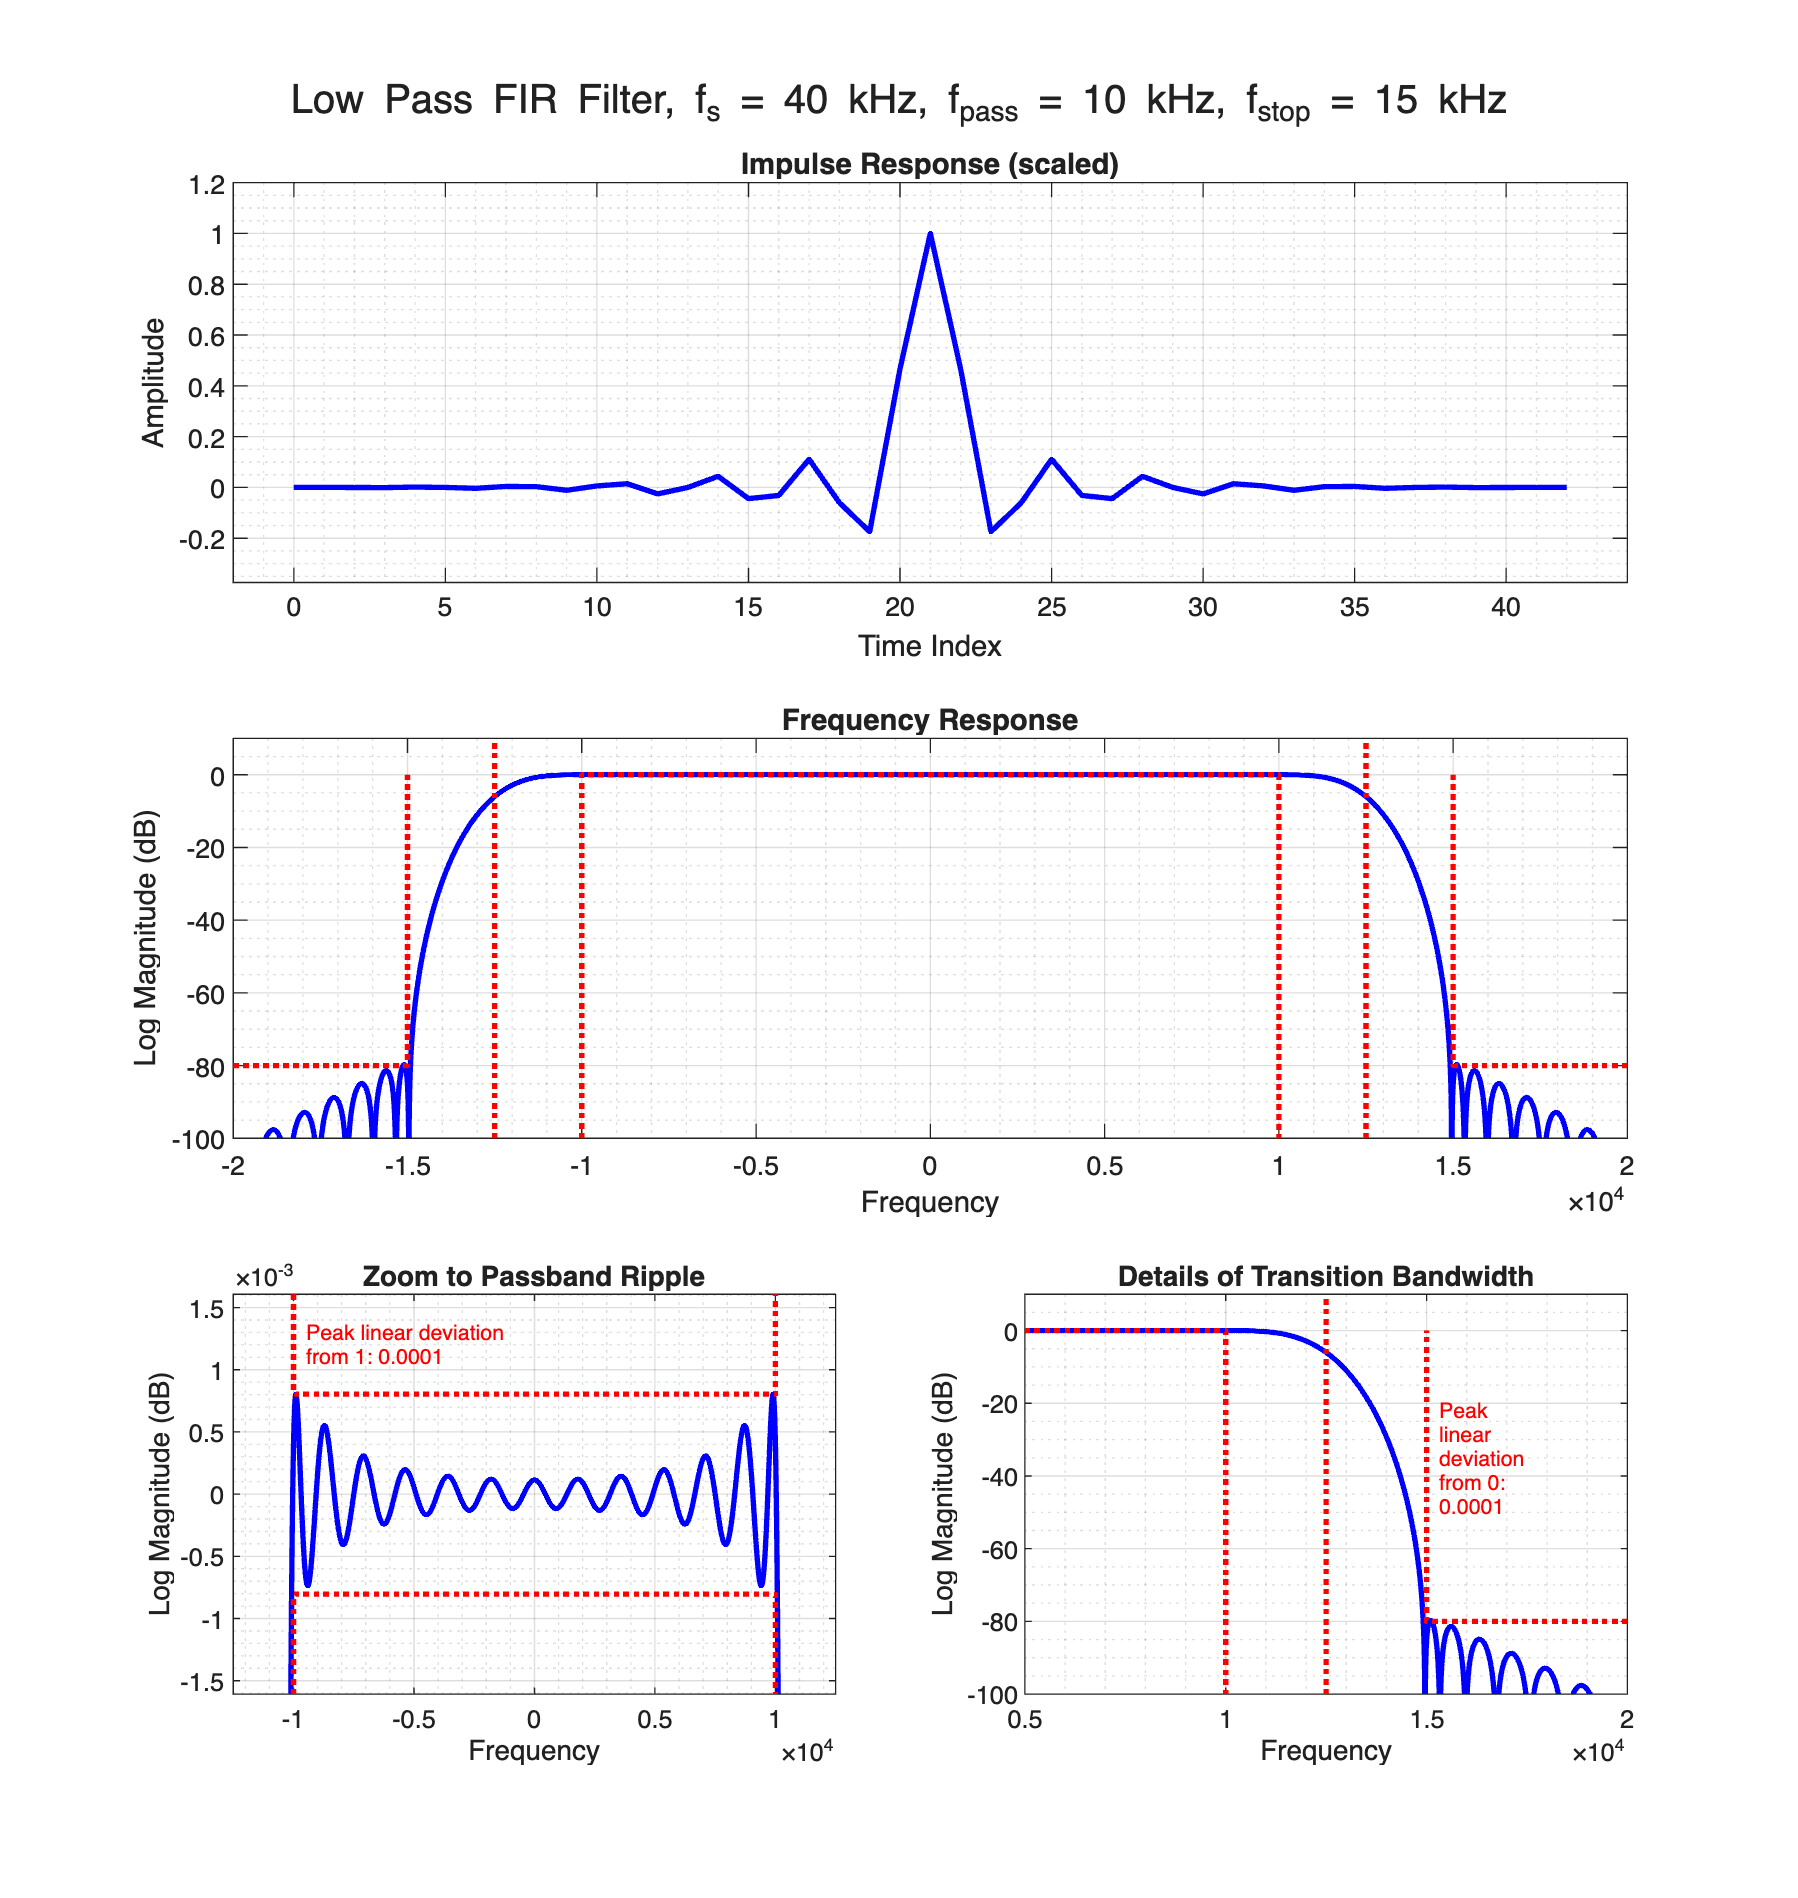

%% Homework 3, problem 1a
fs = 40000; % Sample rate
f1 = 10000; % Passband frequency
f2 = 15000; % Stopband frequency
A_dB = 80;  % Stopband attenuation

Beta = A_dB / 10;

[~, MM] = estimate_filter_len(fs, f1, f2, A_dB, NaN, "harris");

phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;

h0 = h .* kaiser(2 * MM + 1, Beta)';
h1 = h0 * (f2 + f1) / fs;

filter_plots(MM, fs, f1, f2, A_dB, h1);

## Homework 3, problem 1b

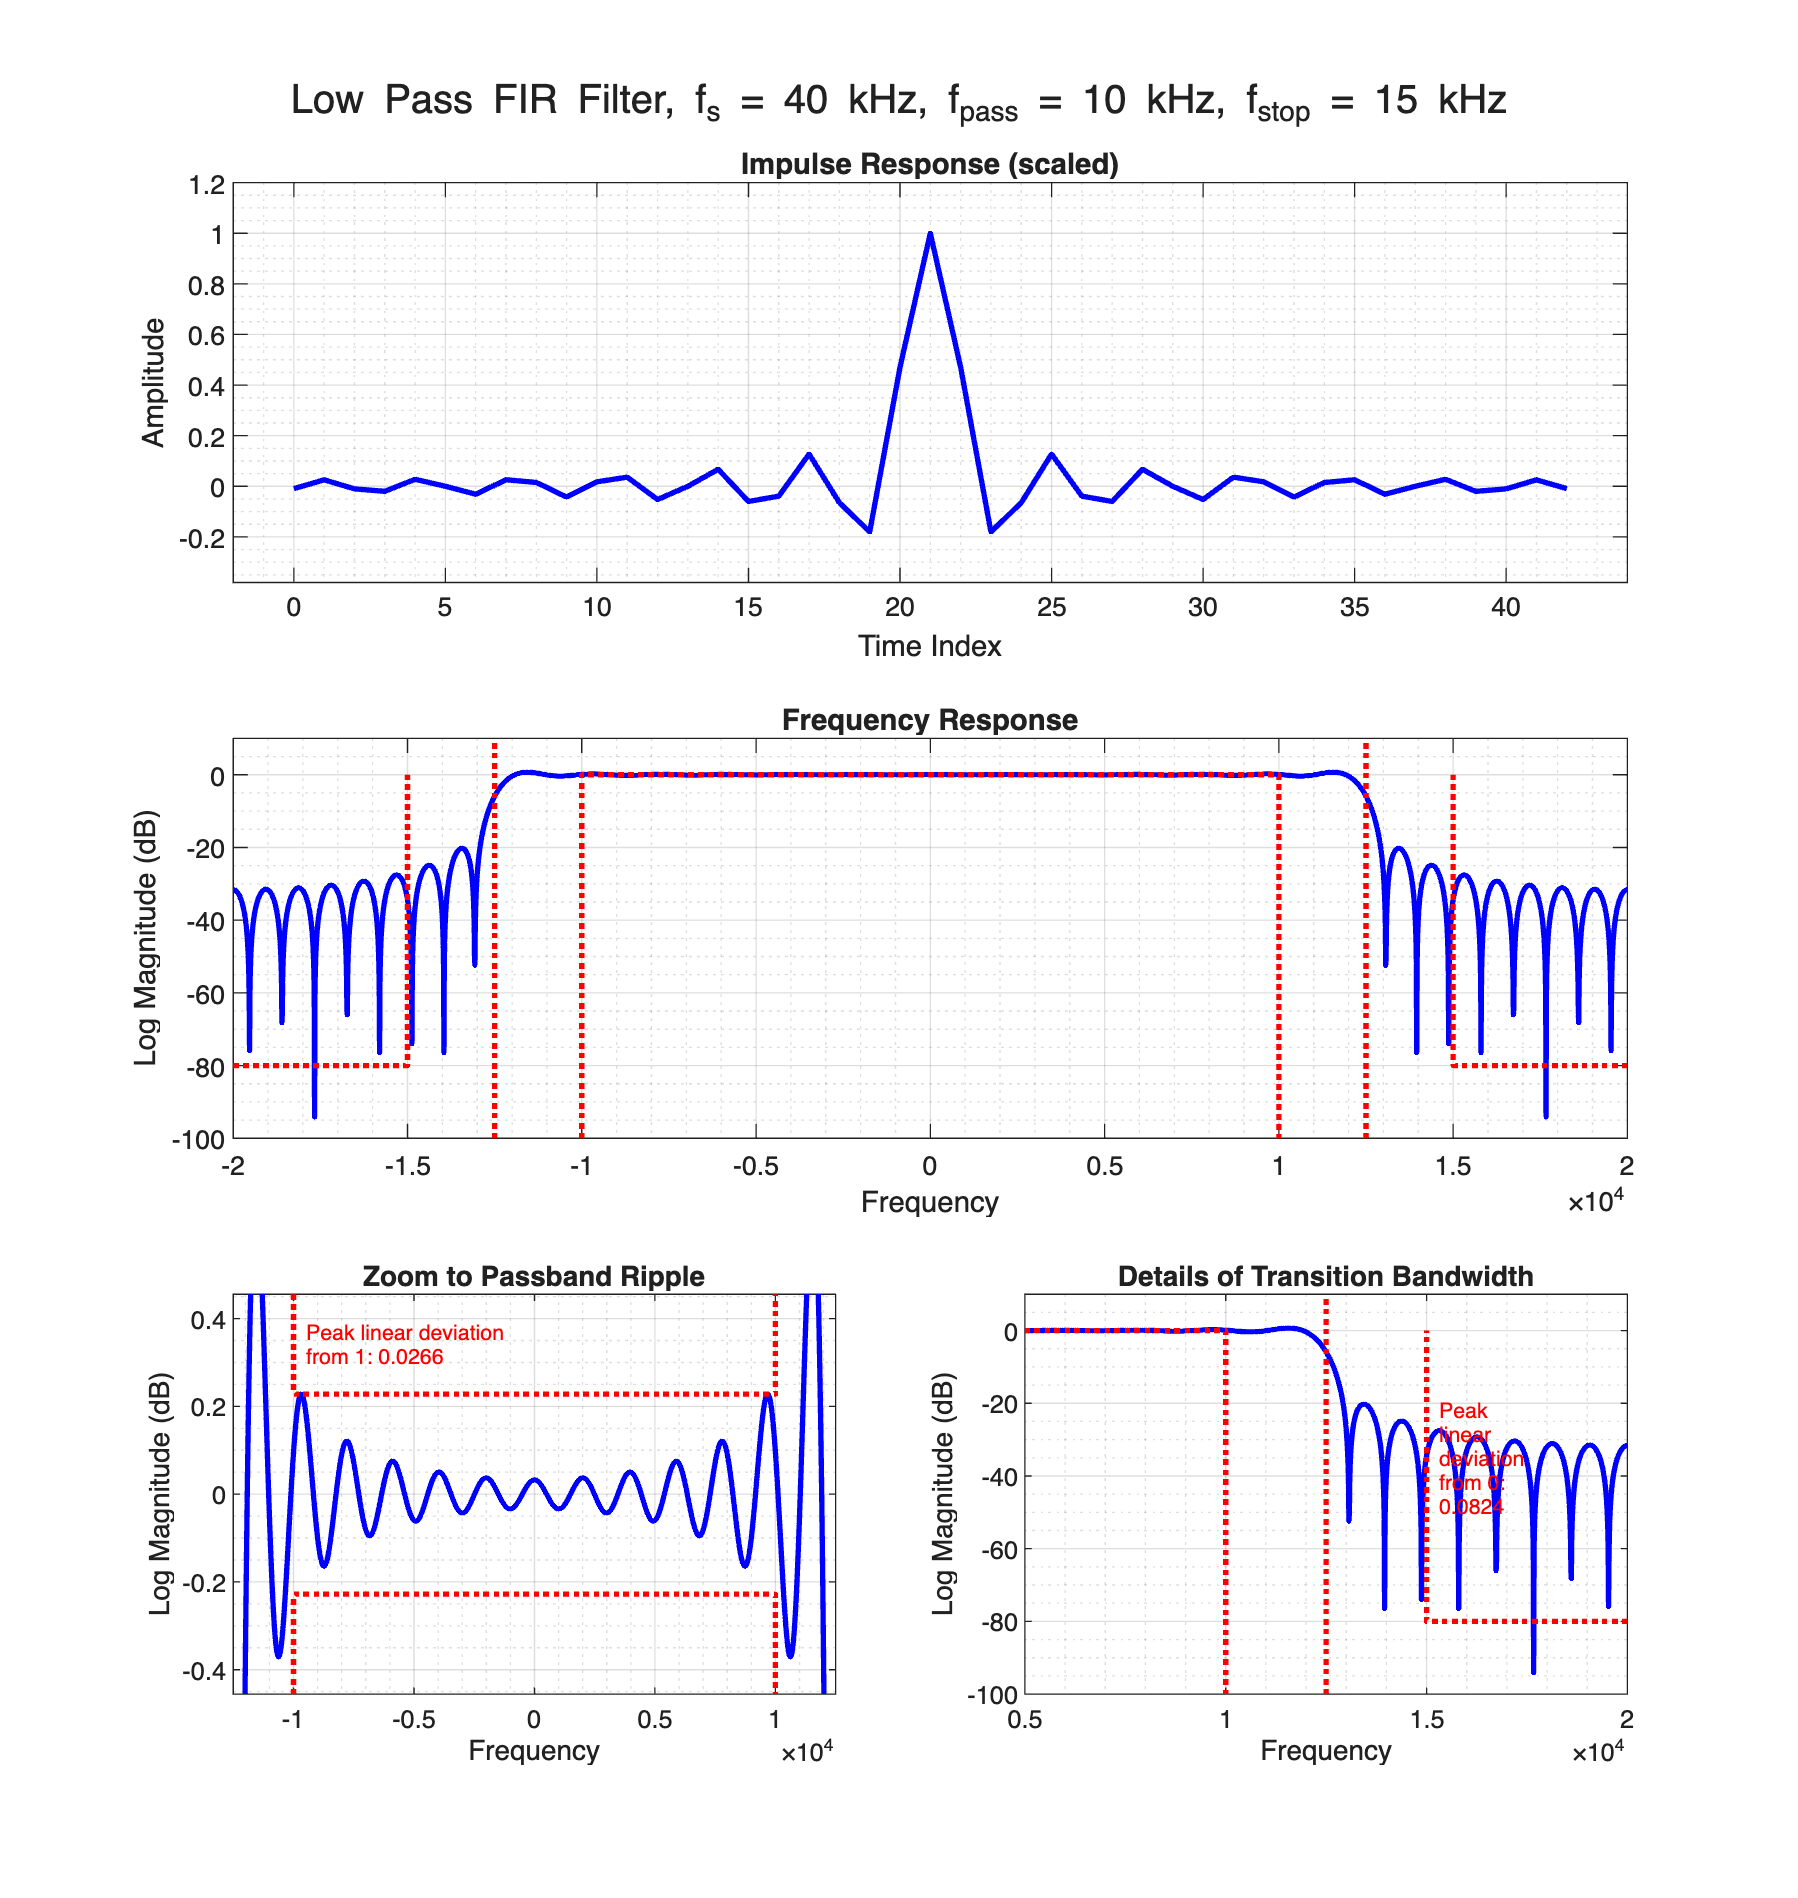

%% Homework 3, problem 1b
% Same filter specs as 3-1a, just not applying Kaiser window
h1 = h .* (f2 + f1) / fs; % Normalization only

filter_plots(MM, fs, f1, f2, A_dB, h1);

By inspection, this filter does not meet the requirements for stopband attenuation.

The peak linear deviation from desired stopband gain of 0 (stopband ripple) is 825 times more than the window design of 1a).

The peak linear deviation from desired passband gain of 1 (passband ripple) is about 266 times more in magnitude than 1a).

The transition bandwidth has significantly less attenuation compared to 1a).

## Homework 3, problem 1c

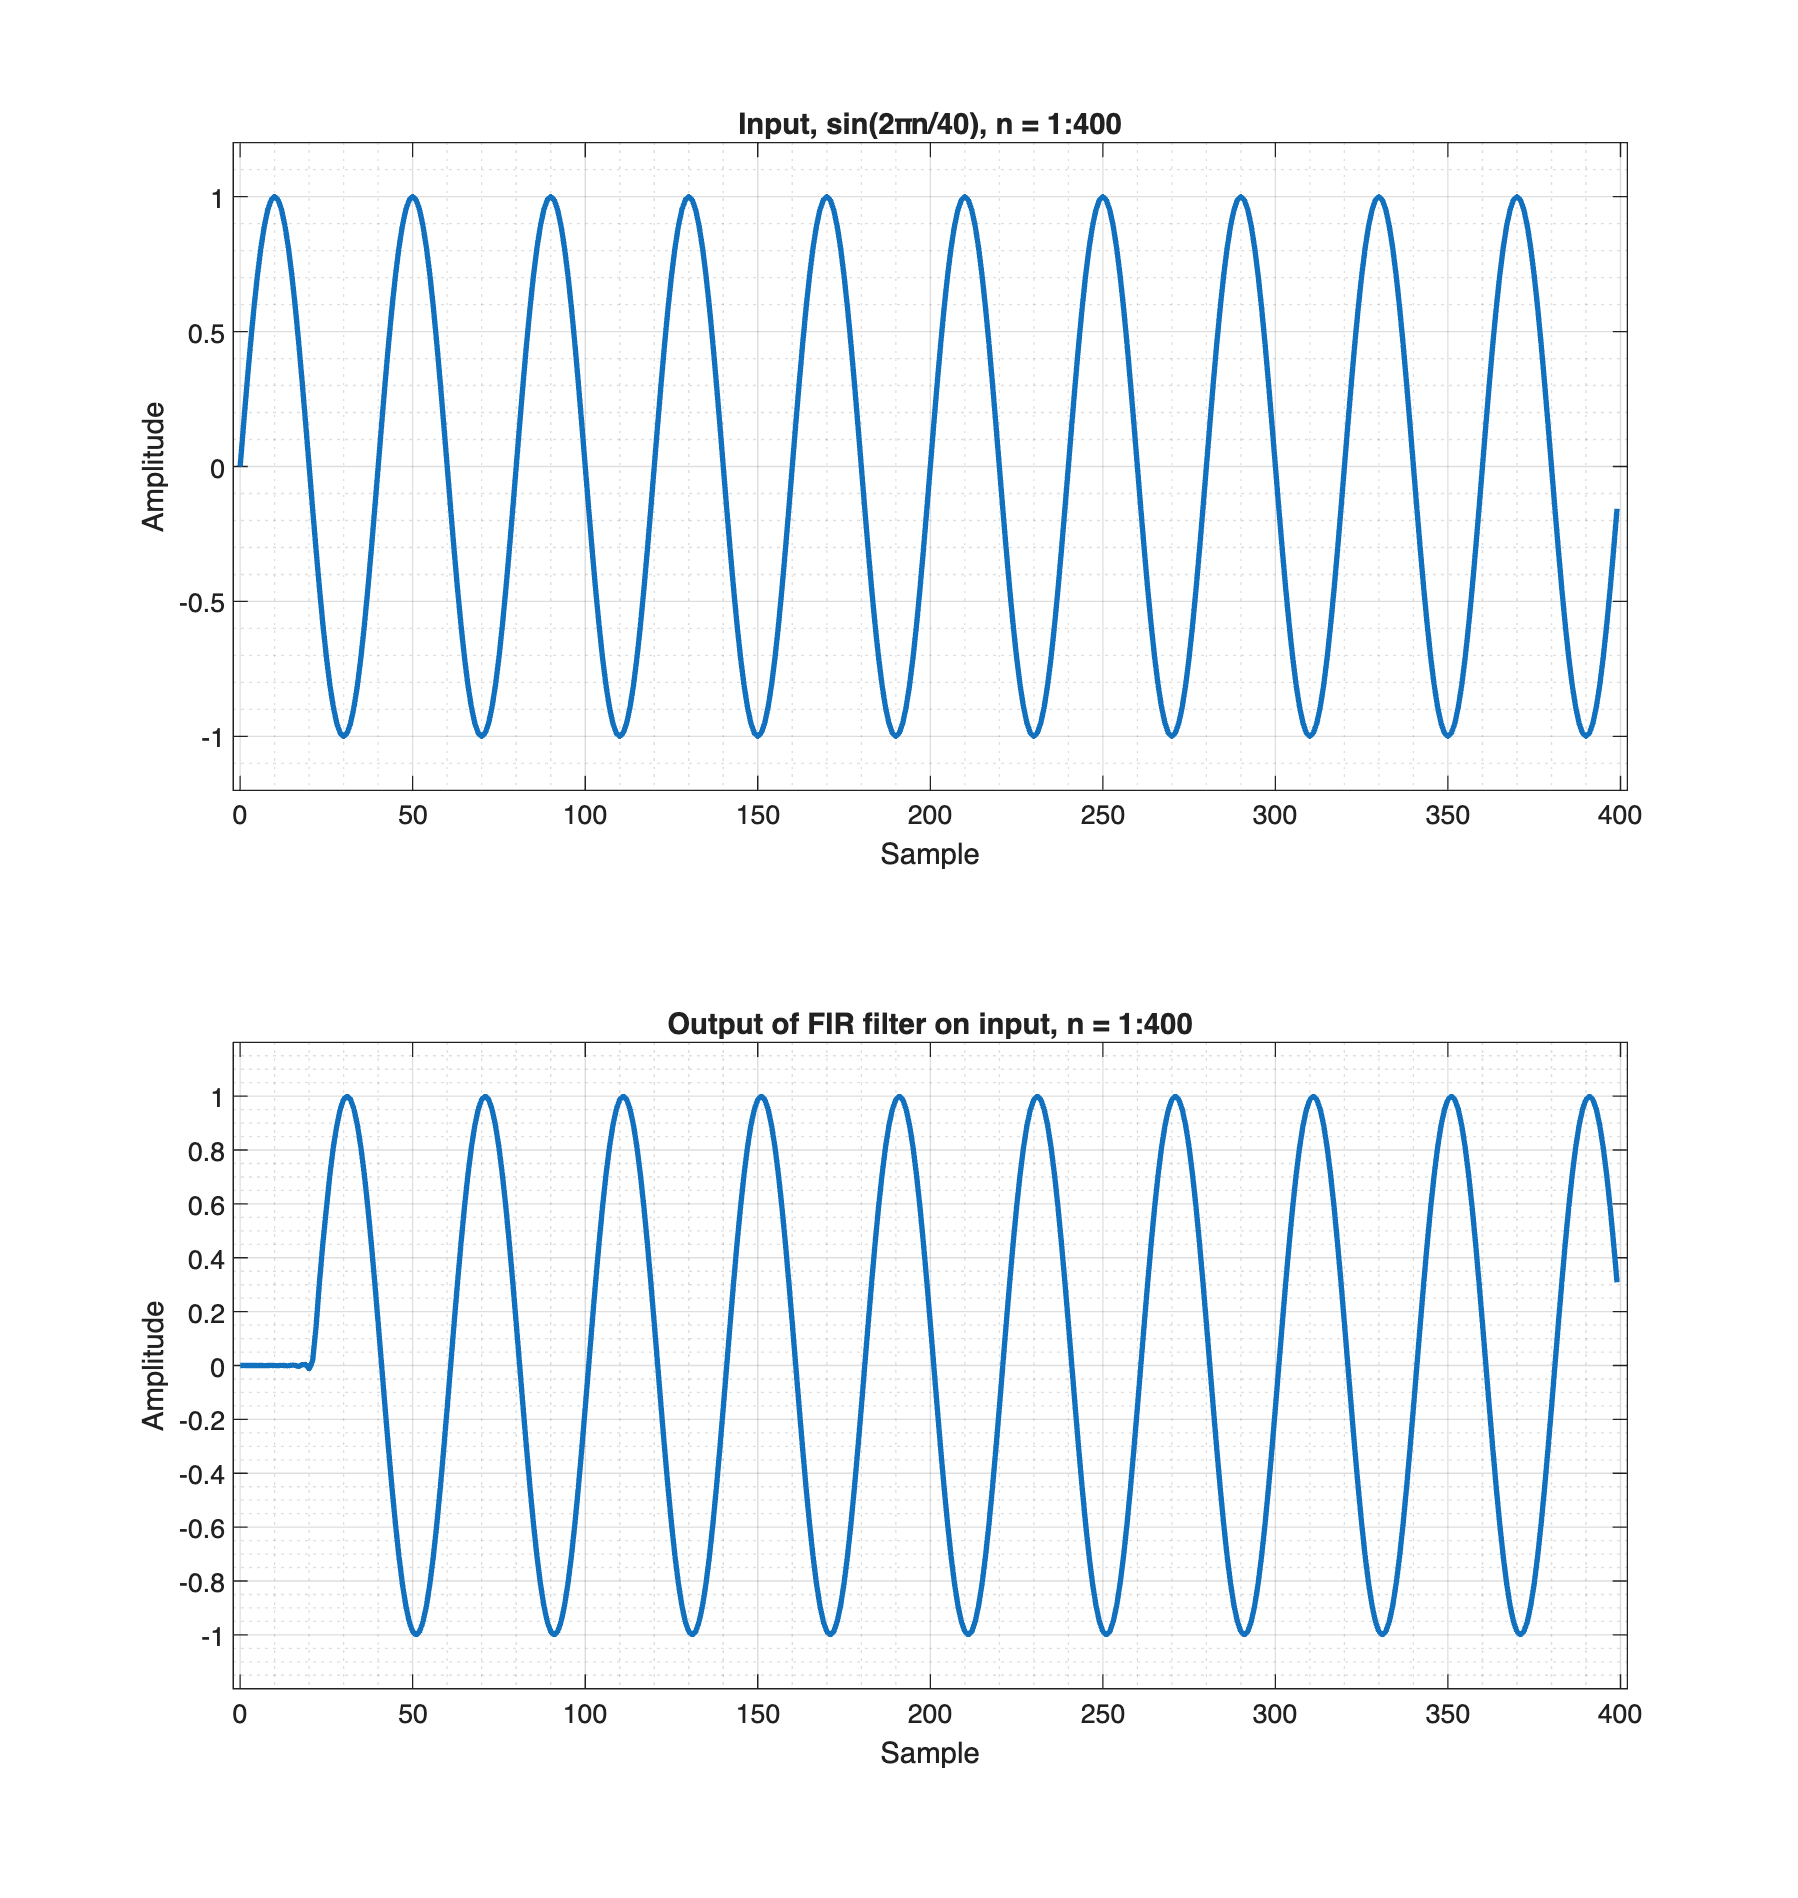

%%Homework 3, problem 1c
n_max = 1000; % Number of samples

% Center frequencies (1 KHz & 19 KHz)
f_a = 1000;
f_b = 19000;

% Converting to digital frequencies (radians per sample)
w_a = 2 * pi * f_a / fs;
w_b = 2 * pi * f_b / fs;

n = 0 : n_max - 1;
x_a = sin(w_a * n);
x_b = sin(w_b * n);
x_c = x_a + x_b;

% Reproducing filter from 3-1a
[~, MM] = estimate_filter_len(fs, f1, f2, A_dB, NaN, "harris");

phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;

h0 = h .* kaiser(2 * MM + 1, Beta)';
h1 = h0 * (f2 + f1) / fs;

filter_input_output_plots(n, 400, h1, x_a, "sin(2πn/40)");

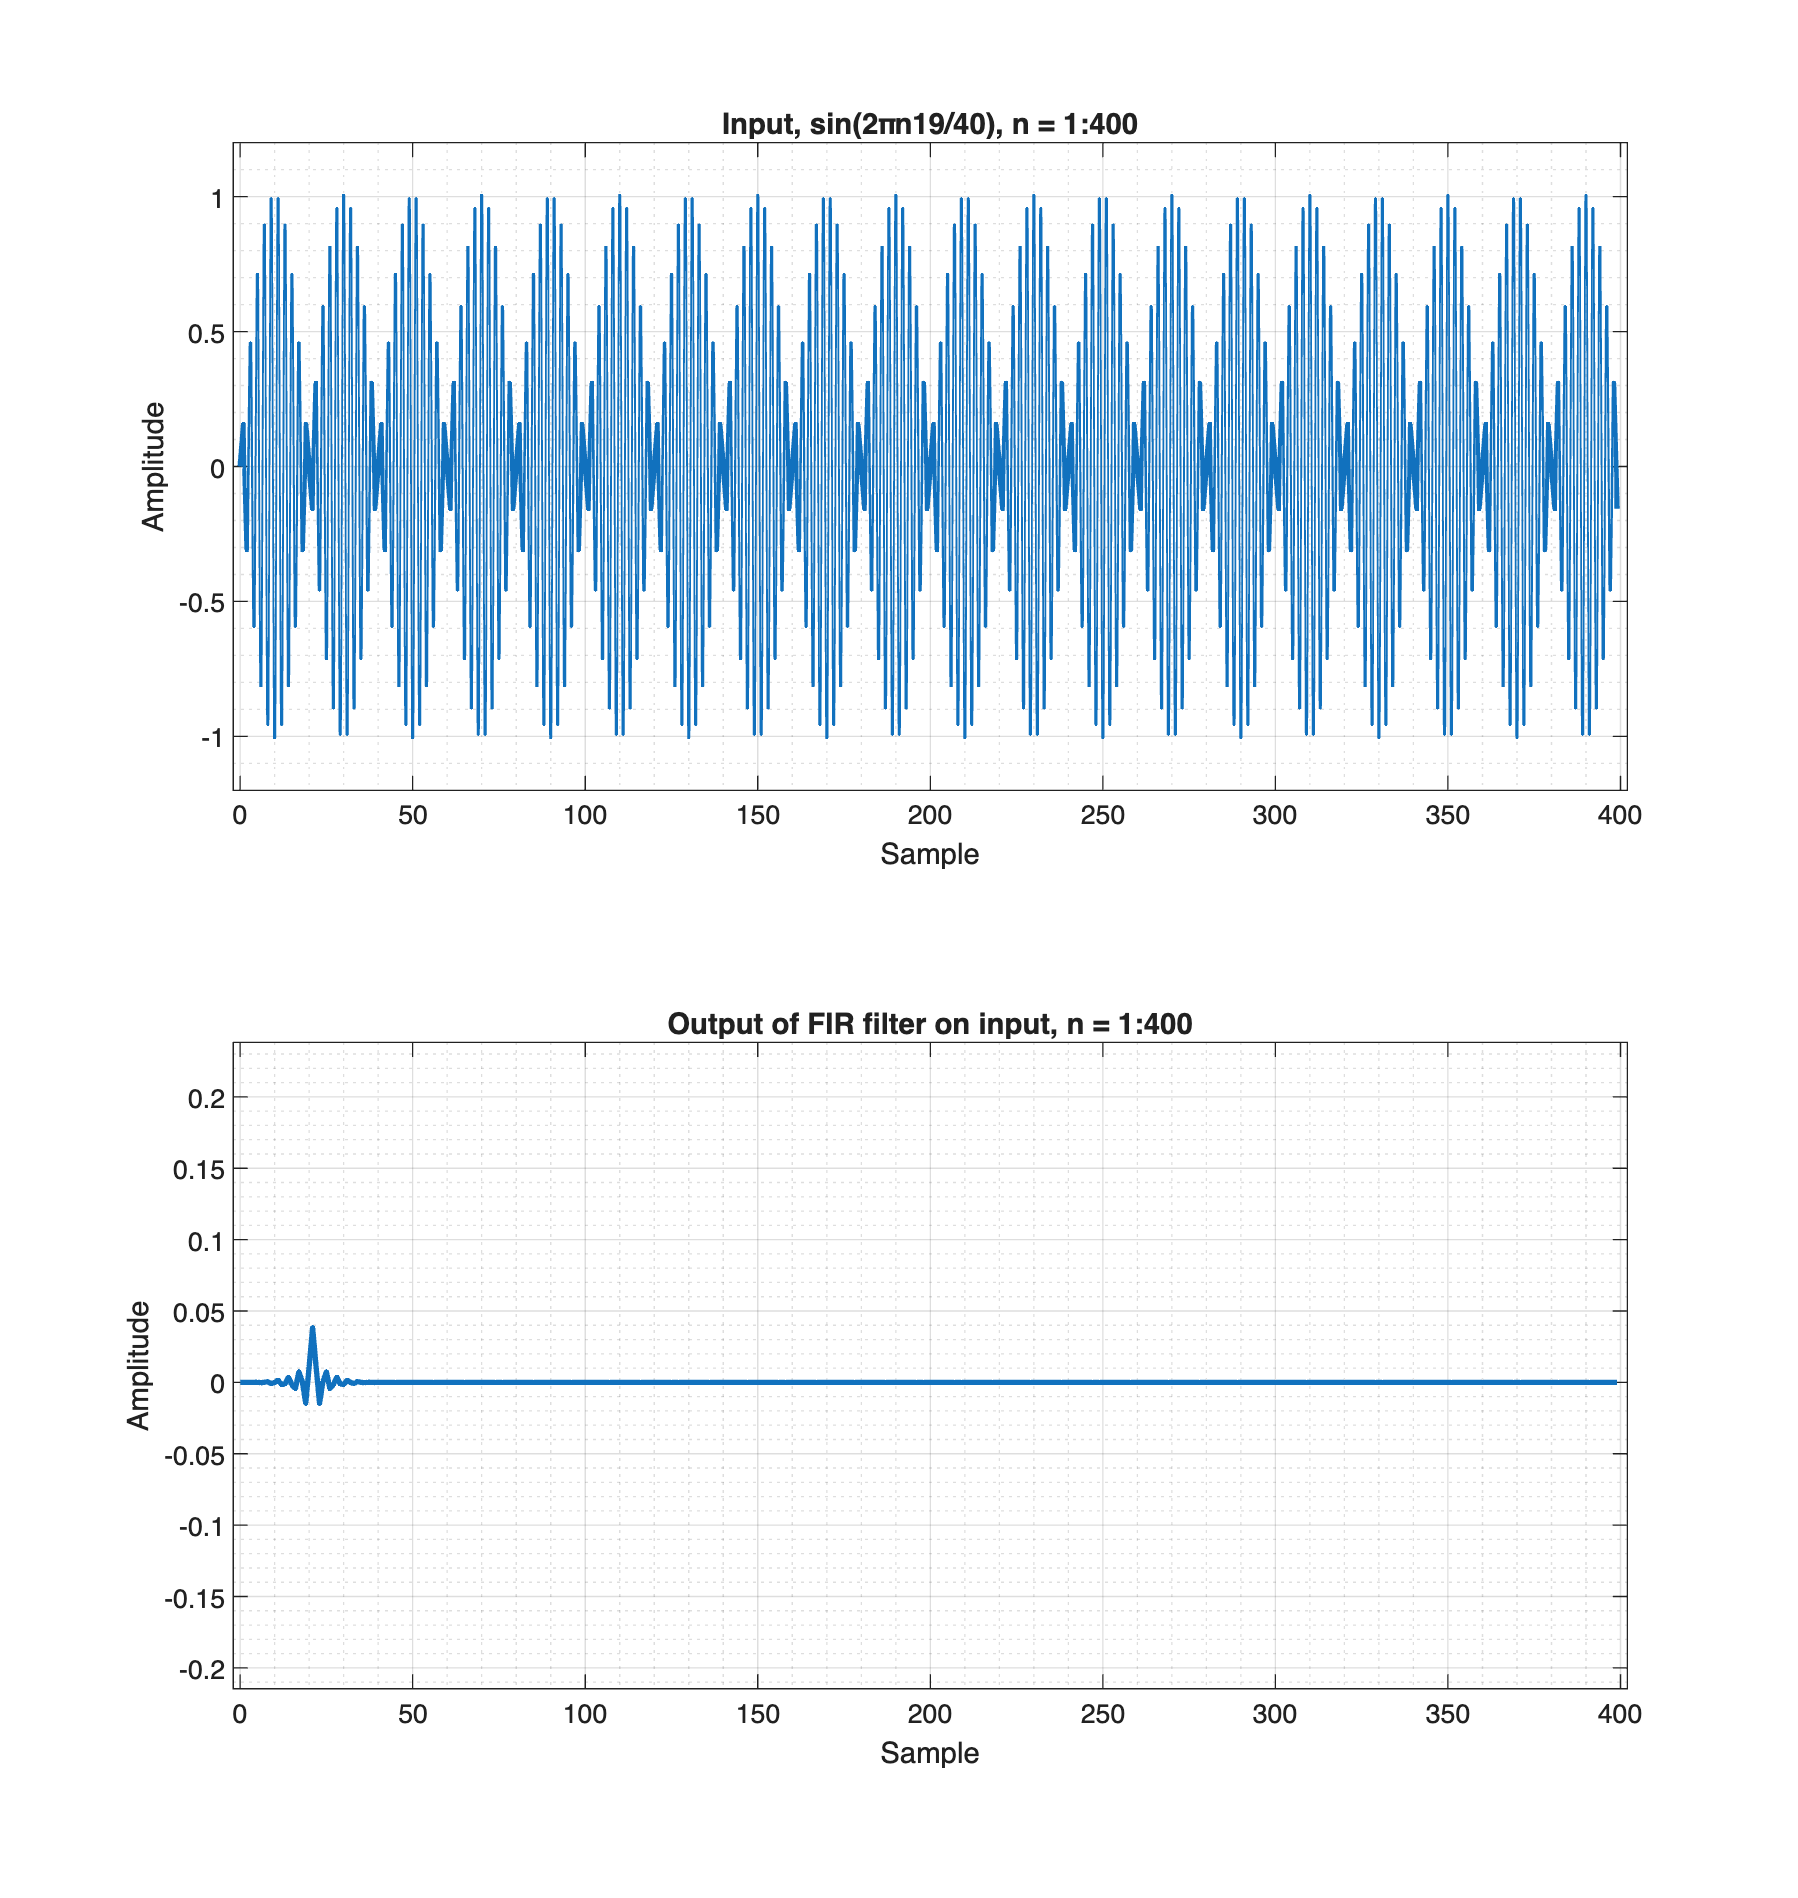

filter_input_output_plots(n, 400, h1, x_b, "sin(2πn19/40)");

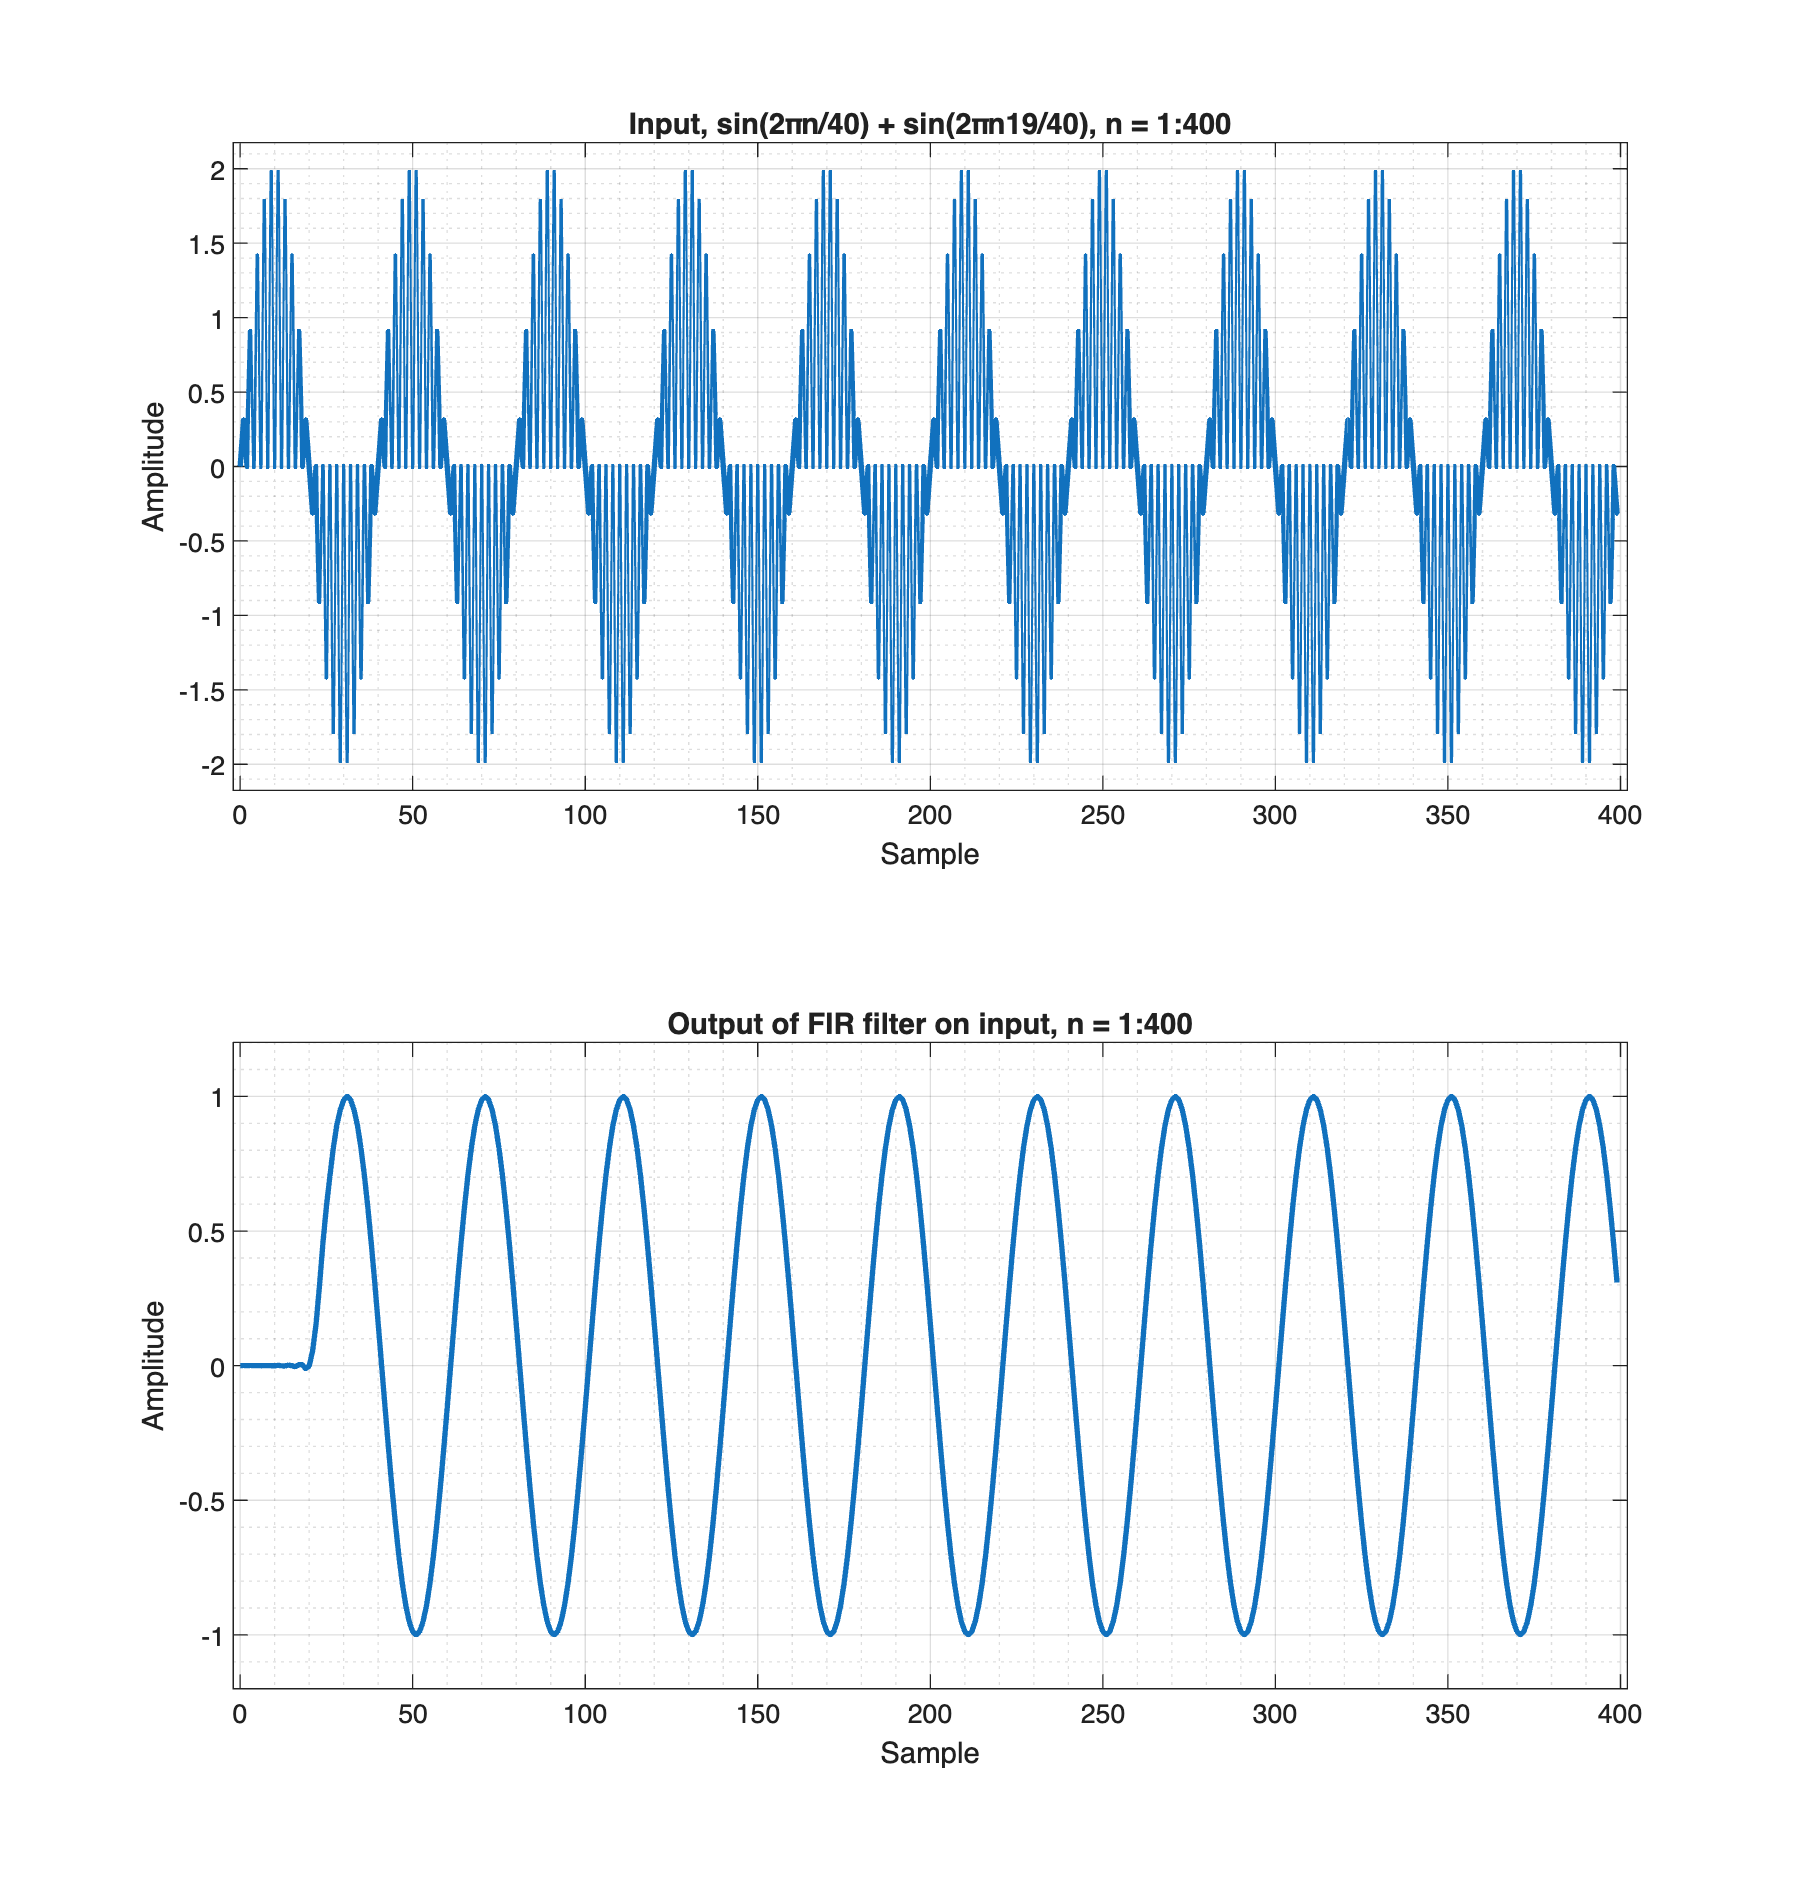

filter_input_output_plots(n, 400, h1, x_c, "sin(2πn/40) + sin(2πn19/40)");

The time delays in the output for all 3 experiments are due to the inherent causal (output depends on current and past inputs only) nature of the filter - which introduces group delay. The impulse response of FIR filter in 1a) is symmetric and hence, the filter is linear phase (delays all frequency components by the same amount). Consequently, delay would be (M - 1) / 2 samples, with M being the filter order.

In the above experiments, M = 43 and the delay is 21 samples. 

## Homework 3, problem 1d

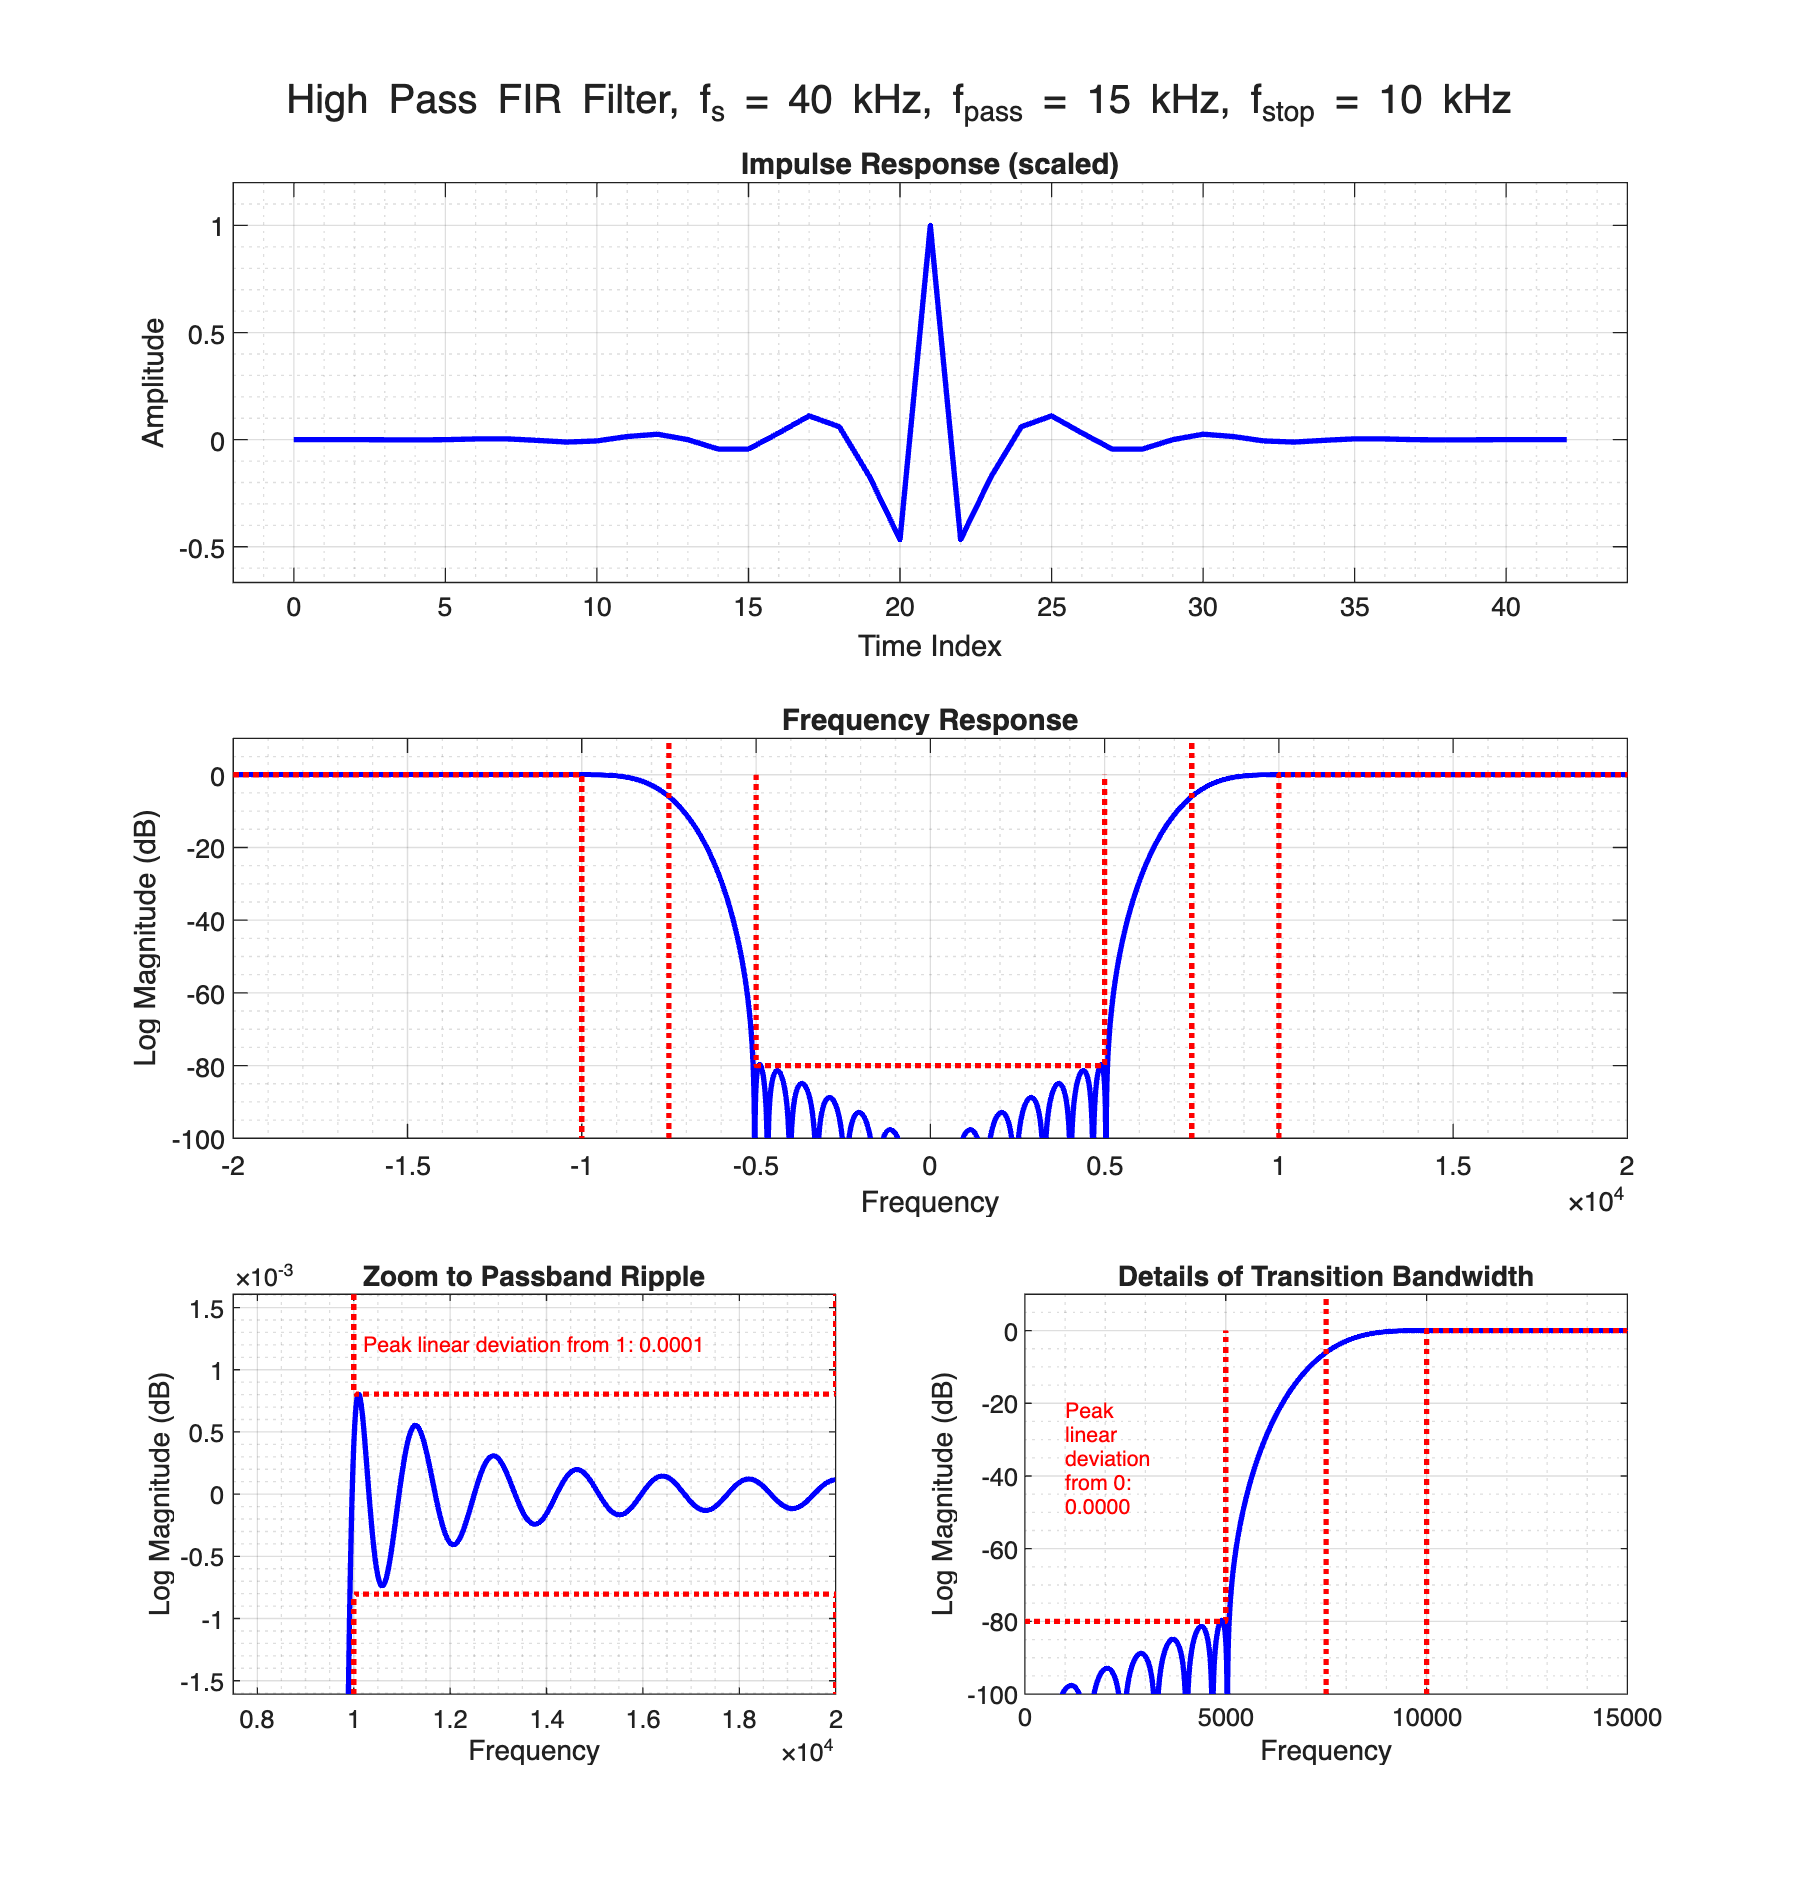

%% Homework 3a, problem 1d
h2 = h1 .* cos(pi * (-MM : MM));

% Scaling for plotting impulse response
scl = max(h2);
h2_scale = h2 / scl;

figure("Position", [0 0 900 950]);
sgtitle(...
  sprintf(...
    "%s, f_s = %d kHz, f_{pass} = %.0f kHz, f_{stop} = %.0f kHz", ...
    "High Pass FIR Filter", fs/1000, f2/1000, f1/1000));
subplot(3, 1, 1)
plot(0 : 2 * MM, h2_scale, "b", "LineWidth", 2);
grid on; grid minor;
axis([-2, 2 * MM + 2, min(h2_scale) - 0.2, max(h2_scale) + 0.2]);
title("Impulse Response (scaled)");
xlabel("Time Index"); ylabel("Amplitude");

f_h2 = fftshift(20 * log10(abs(fft(h2, num_fft))));
subplot(3, 1, 2);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
% Show the stopband frequency and gain
plot(...
  [(-fs/2 + f2) (-fs/2 + f2) (fs/2 - f2) (fs/2 - f2)], ...
  [0 -A_dB -A_dB 0], ":r", "LineWidth", 2);
% Show the passband frequency
plot([-fs/2 (-fs/2 + f1) (-fs/2 + f1)], [0 0 -100], ":r", "LineWidth", 2);
plot([(fs/2 - f1) (fs/2 - f1) fs/2], [-100 0 0], ":r", "LineWidth", 2);
% Show the 6dB frequency (midway between passband and stopband)
f0 = (fs - (f1 + f2)) / 2;
plot([-f0 -f0], [-100 10], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([-fs/2 fs/2 -100 10]);
title("Frequency Response");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

% Checking passband ripple in range (start_idx:end_idx) corresponding to the
% positive frequency passband frequency response
start_idx = (1 - (fs/2 - f1) / fs) * num_fft;
end_idx = num_fft;
max_dev = max(f_h2(start_idx:end_idx));
% Calculate the peak linear deviation in passband
pk_lin_dev_passband = abs(1 - 10 ^ (max_dev / 20));

subplot(3, 2, 5);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
y_lim = 2 * max_dev; % y-axis limit, scaled according to the peak deviation
plot(...
  [(fs/2 - f1) (fs/2 - f1) fs/2 fs/2], [y_lim max_dev max_dev y_lim], ...
  ":r", "LineWidth", 2);
plot(...
  [(fs/2 - f1) (fs/2 - f1) fs/2 fs/2], [-y_lim -max_dev -max_dev -y_lim], ...
  ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([f0 fs/2 -y_lim y_lim]);
text(...
  (fs/2 - f1) + 200, 1.5 * max_dev, ...
  sprintf("Peak linear deviation from 1: %.4f", pk_lin_dev_passband), ...
  "Color", "red", "FontSize", 8);
title("Zoom to Passband Ripple");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

% Checking stopband ripple in range (start_idx:end_idx) corresponding to the
% positive frequency stopband frequency response
start_idx = num_fft / 2;
end_idx = start_idx + ((f1 / fs) * num_fft);
max_dev = max(f_h2(start_idx:end_idx));
% Calculate the peak linear deviation in stopband
pk_lin_dev_stopband = abs(1 - 10 ^ (max_dev / 20));

subplot(3, 2, 6);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
plot([(fs/2 - f1) (fs/2 - f1) fs/2], [-100 0 0], ":r", "LineWidth", 2);
f0 = (fs - (f1 + f2)) / 2;
plot([0 (fs/2 - f2) (fs/2 - f2)], [-80 -80 0], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([0. f2 -100 10]);
text(...
  f2/15, -35, ...
  sprintf("Peak\nlinear\ndeviation\nfrom 0:\n%.4f", pk_lin_dev_stopband), ...
  "Color", "red", "FontSize", 8);
title("Details of Transition Bandwidth");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

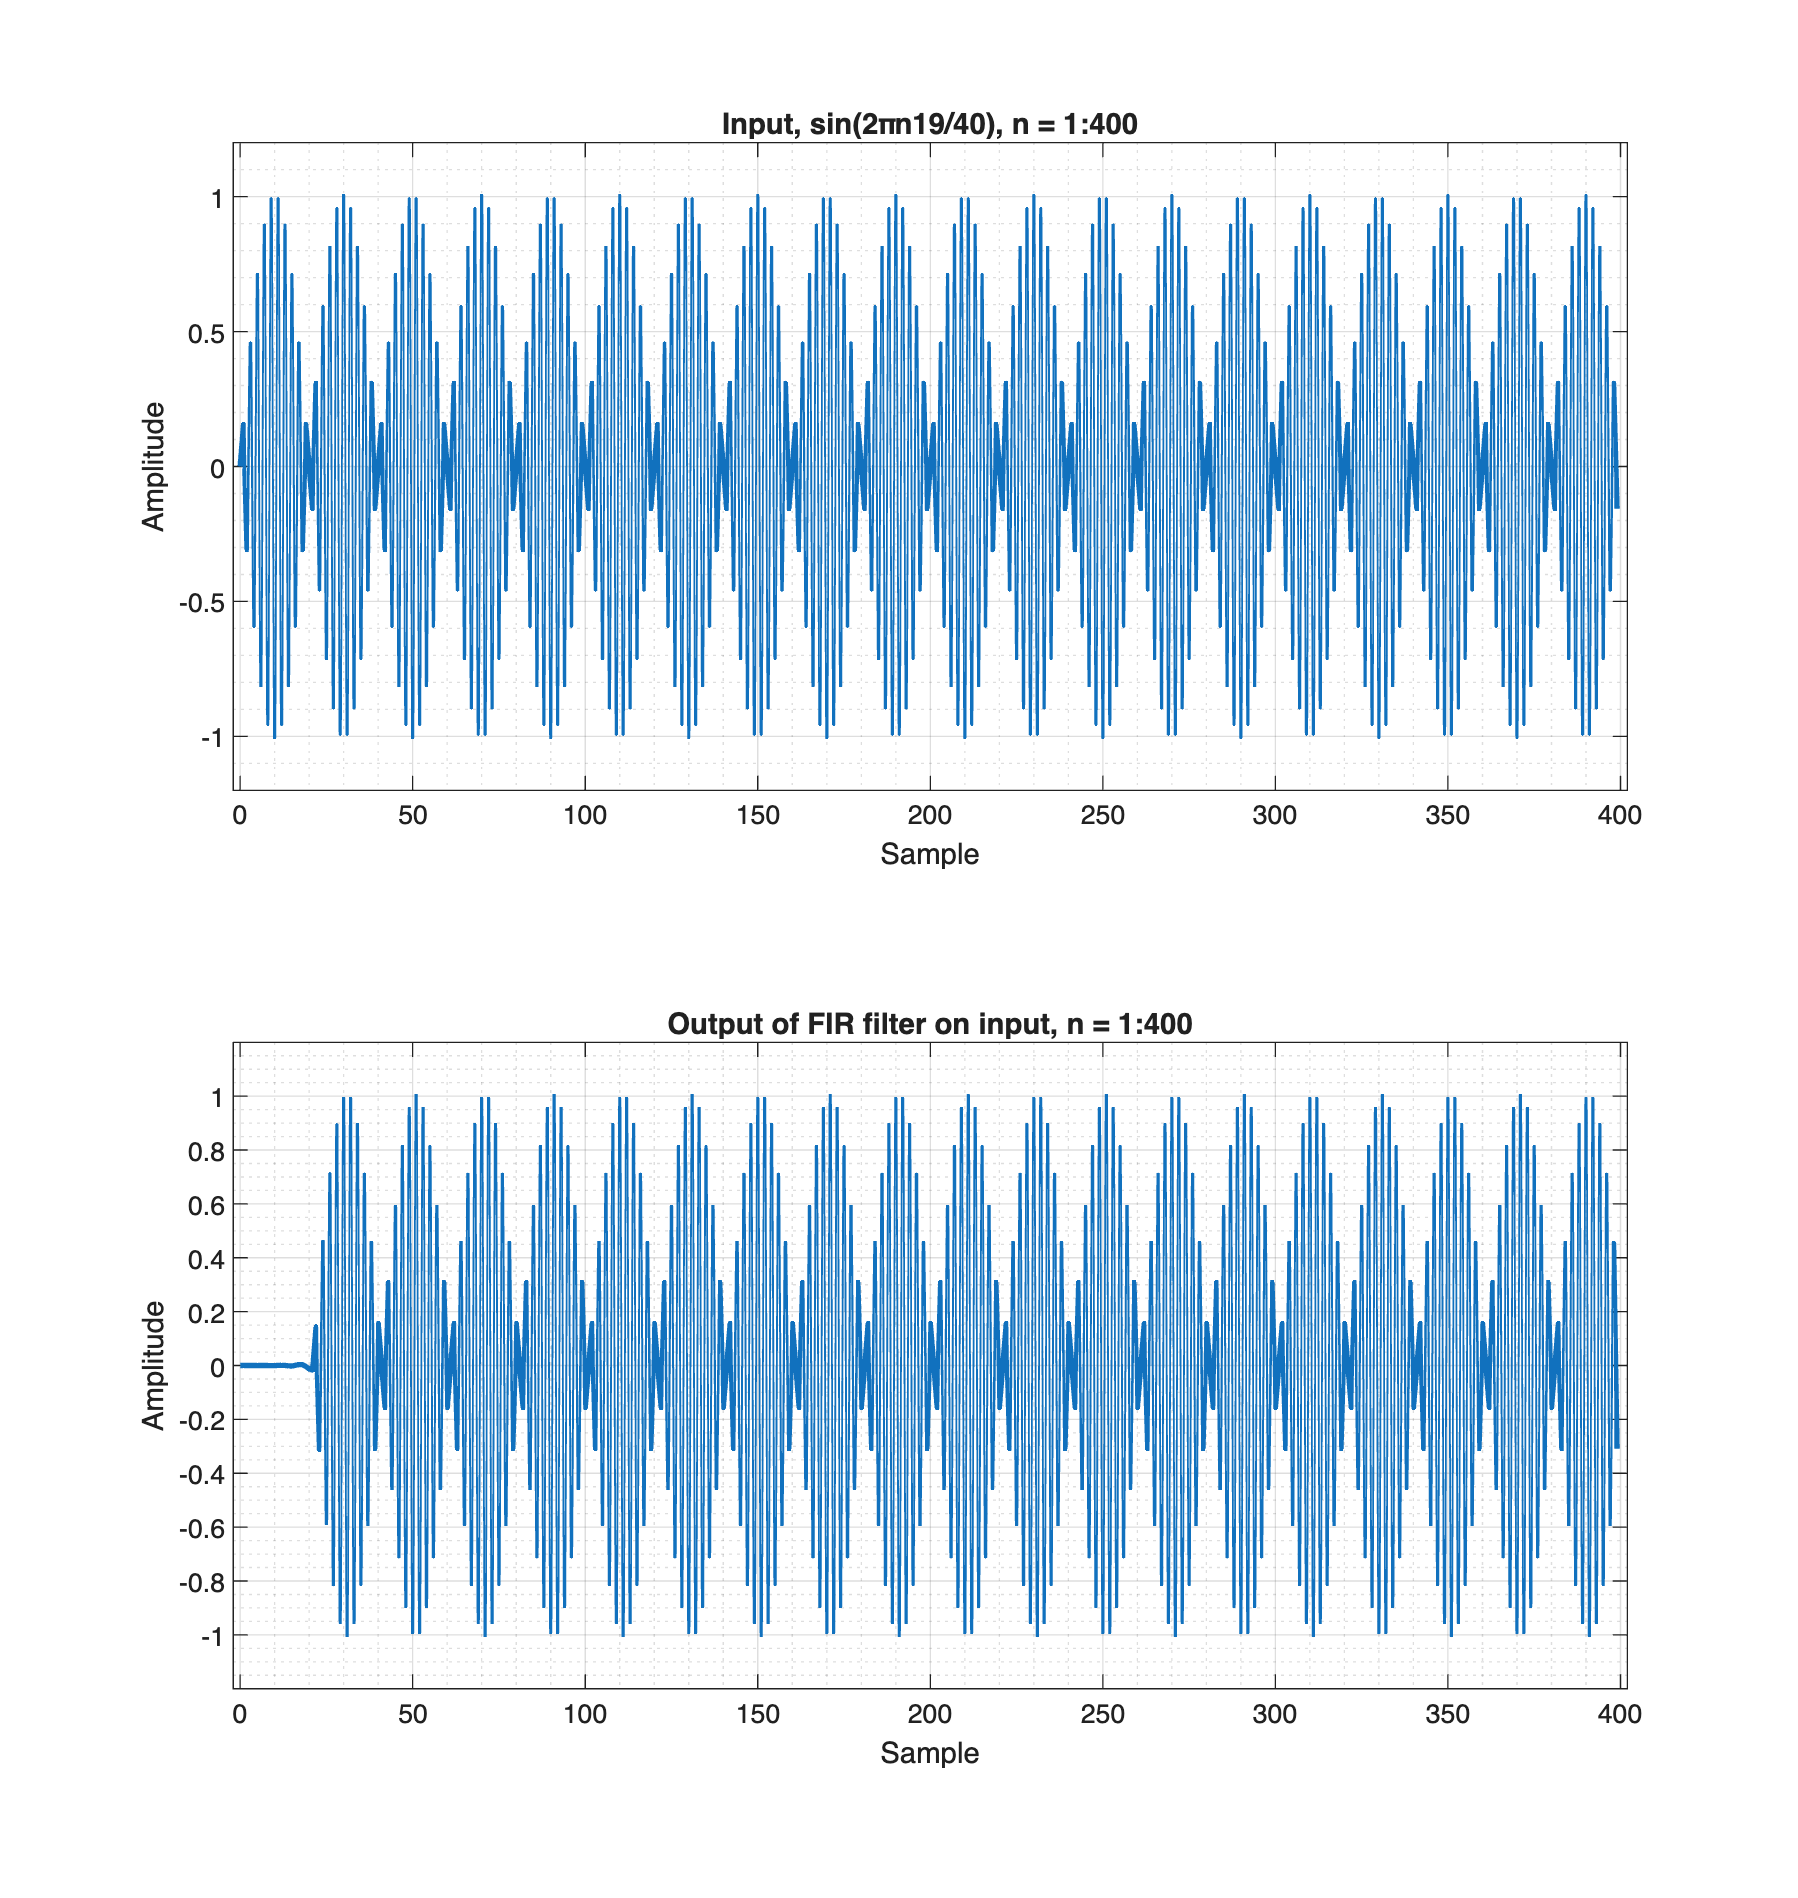


filter_input_output_plots(n, 400, h2, x_b, "sin(2πn19/40)");

## Homework 3, problem 1e

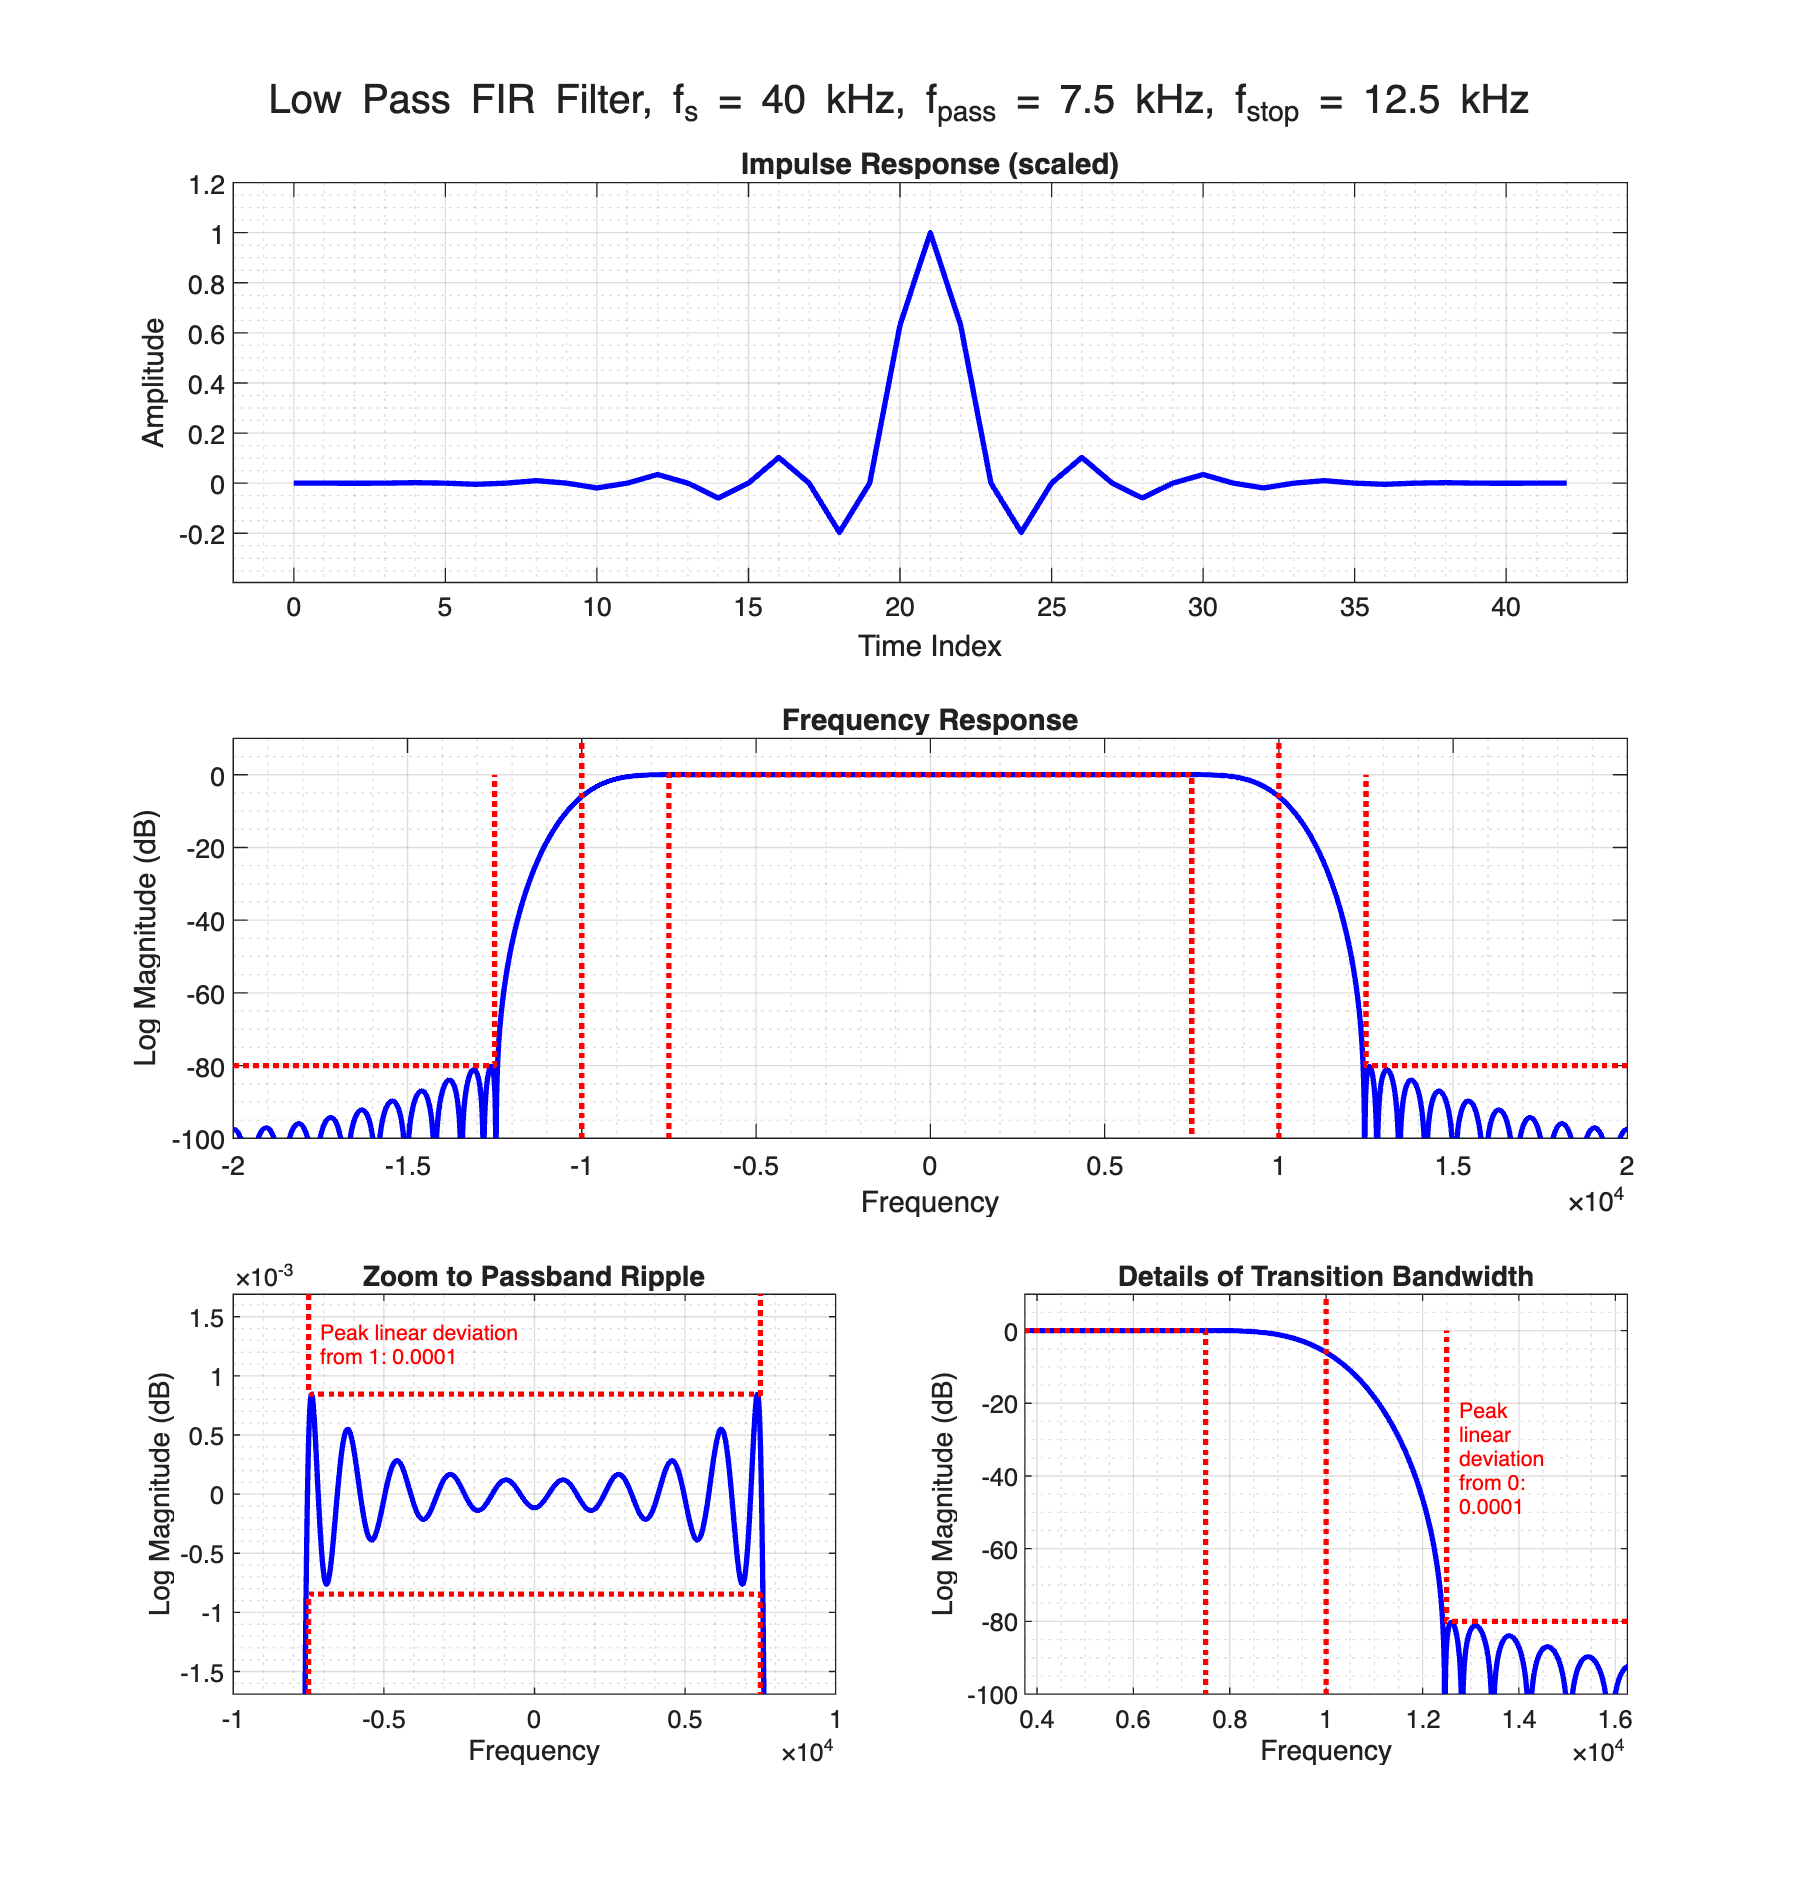

%% Homework 3, problem 1e
fs   = 40000; % Sample rate
f1   = 7500;  % Passband frequency
f2   = 12500; % Stopband frequency
A_dB = 80;    % Stopband attenuation

Beta = A_dB / 10;

[~, MM] = estimate_filter_len(fs, f1, f2, A_dB, NaN, "harris");

phi = 2 * pi * (-MM : MM) * (f1 + f2) / (2 * fs);

% Compute unscaled sinc filter h
h = sin(phi) ./ phi;

% Correct failed 0/0 computation
h(MM + 1) = 1;

h0 = h .* kaiser(2 * MM + 1, Beta)';
h1 = h0 * (f2 + f1) / fs;

filter_plots(MM, fs, f1, f2, A_dB, h1);

Half band filters have alternate coefficients as 0 (all even coefficients except center tap). This makes them very efficient to implement and computationally faster.

## Homework 3a, problem 1a

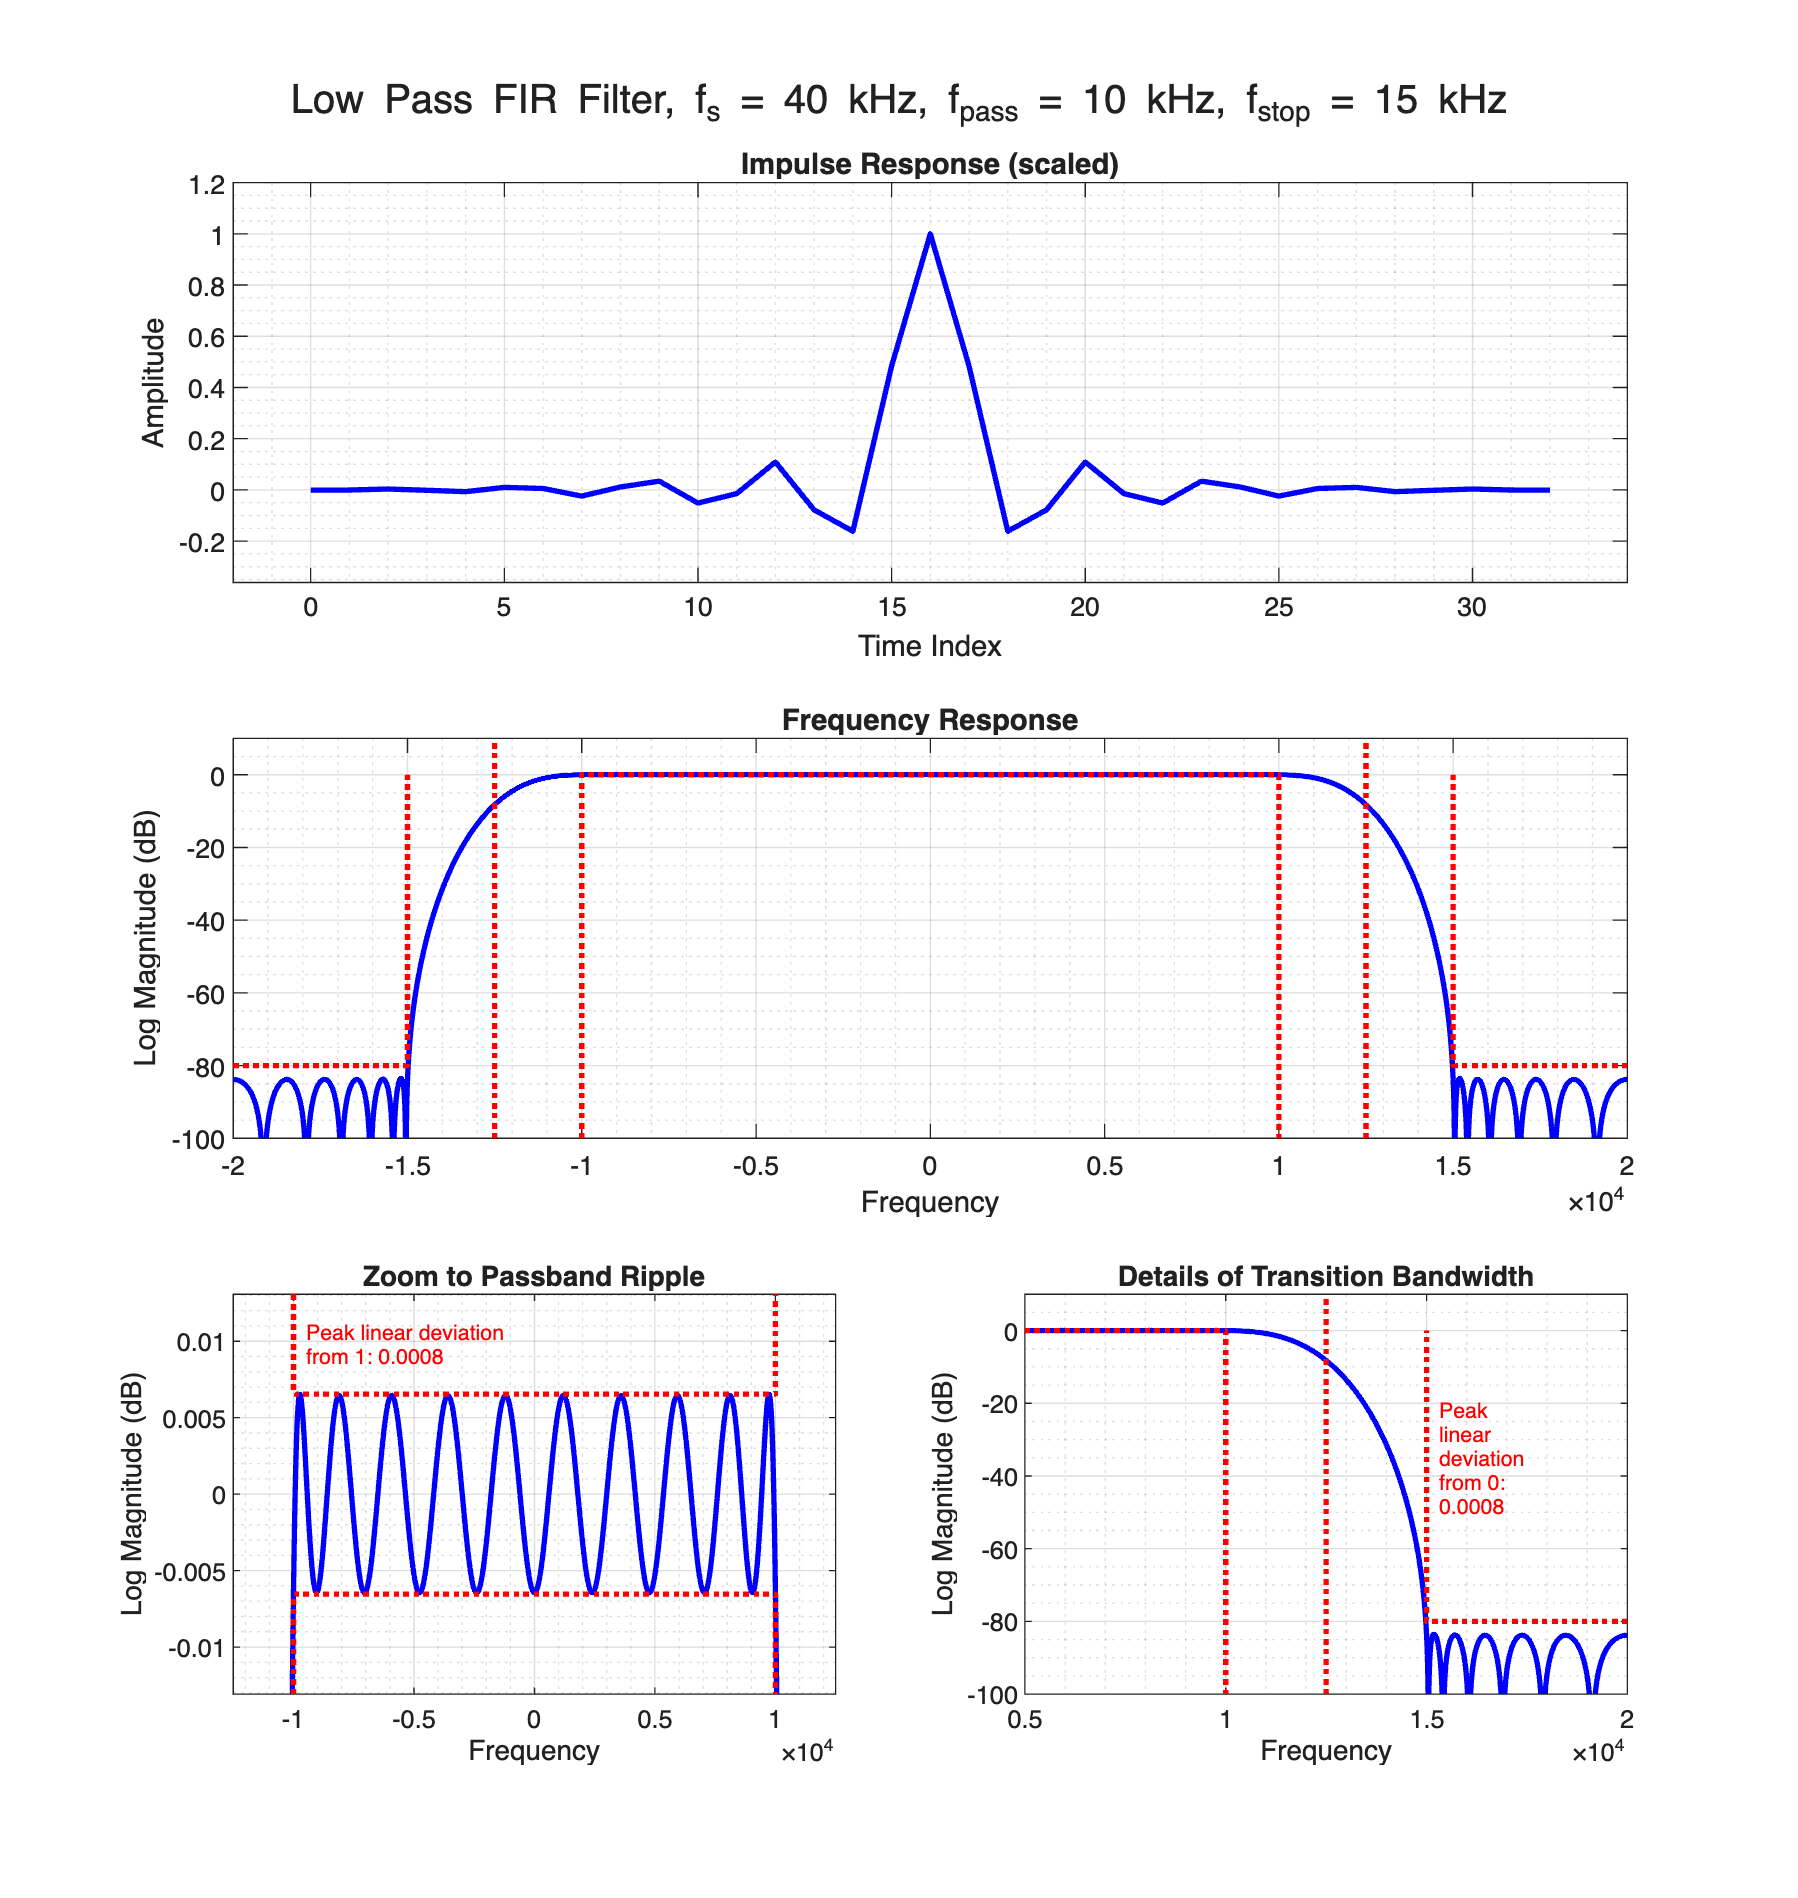

%% Homework 3a, problem 1a
fs = 40000;  % Sample rate
f1 = 10000;  % Passband frequency
f2 = 15000;  % Stopband frequency
A_dB = 80;   % Stopband attenuation
rppl = 0.01; % Passband & stopband ripple (in dB)

[M, MM, delta_1, delta_2] = ...
  estimate_filter_len(fs, f1, f2, A_dB, rppl, "kaiser");

% Assign the weights
w1 = 1;
w2 = delta_1 / delta_2;

h1 = firpm(M - 1, [0 f1 f2 fs/2] / (fs/2), [1 1 0 0], [w1 w2]);

filter_plots(MM, fs, f1, f2, A_dB, h1);

## Homework 3a, problem 1b

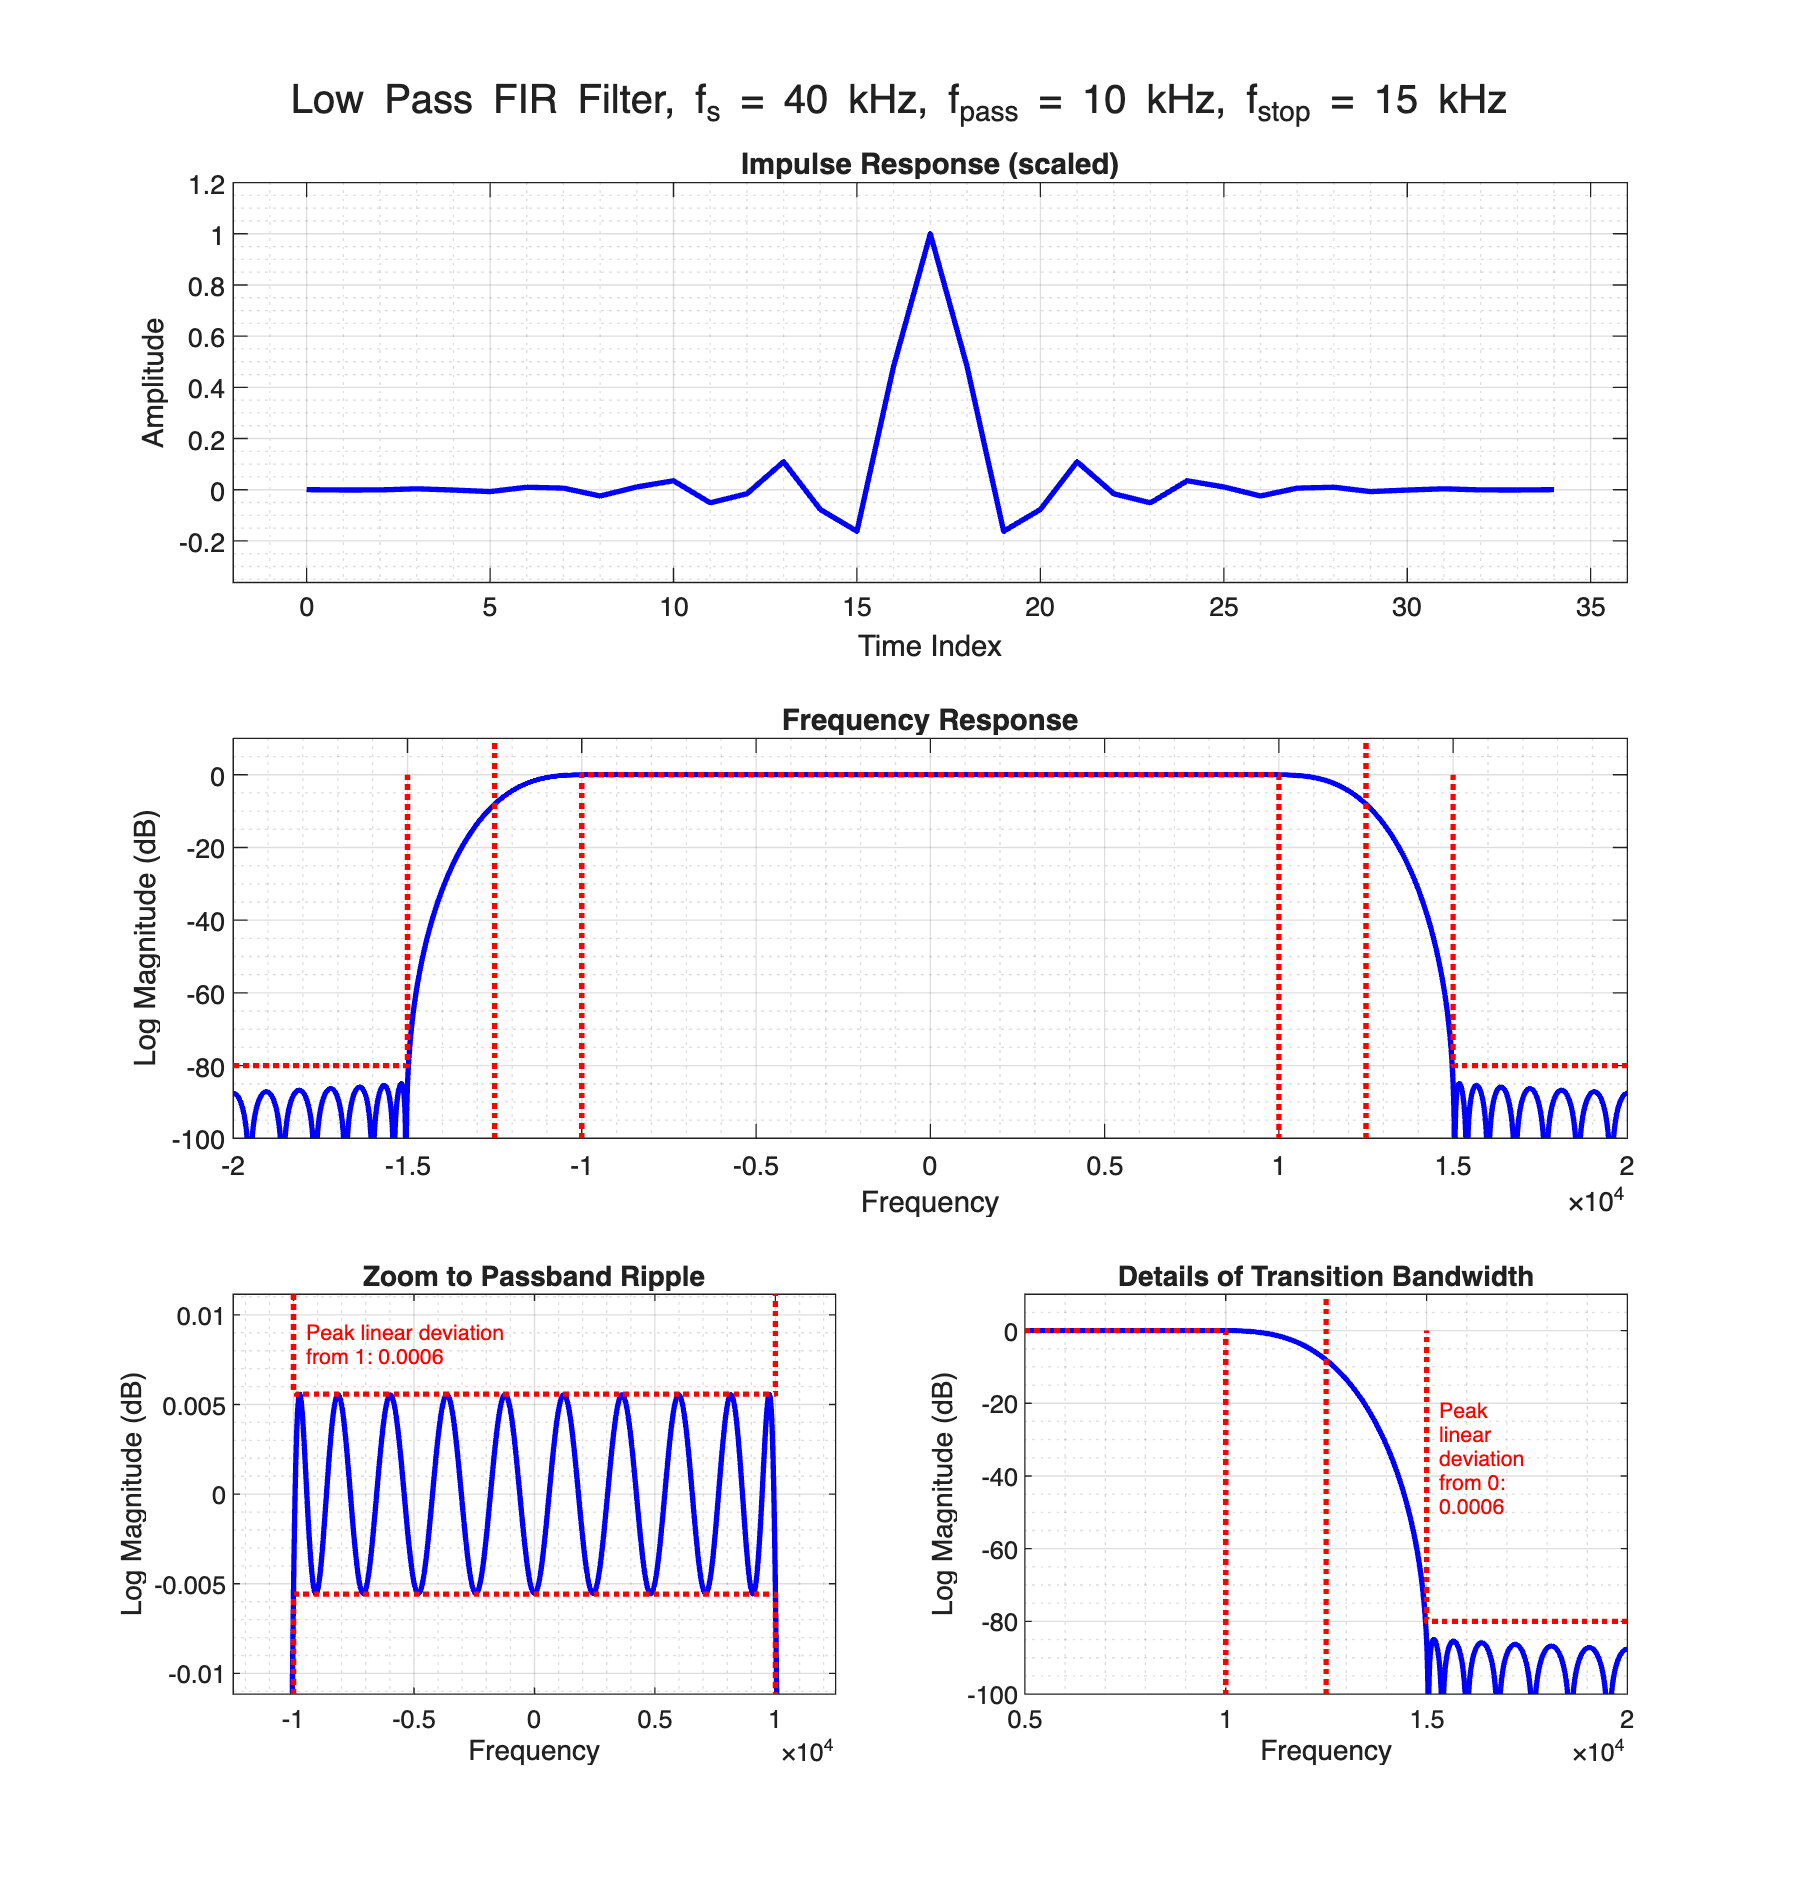

%% Homework 3a, problem 1b
% Pushing the stopband ripple down causes the passband ripple to increase
% slightly. Thus, increasing the filter length by 2 samples so that both
% passband and stopband ripple levels will meet the filter specification
M = M + 2;
MM = (M - 1) / 2;

h1 = ...
  firpm(...
    M - 1, [0 f1 f2 fs/2] / (fs/2), {"myfrf", [1 1 0 0]}, [w1 w2]);

filter_plots(MM, fs, f1, f2, A_dB, h1);

3a-1a uses default Remez algorithm and 3a-1b uses modified Remez algorithm ("myfrf").

The sidelobes are pushed down with the modified Remez algorithm. Consequently, the stopband ripple decreases from 0.0008 in 1a to 0.0006 in 1b.

The passband attenuation and transition bandwidths seem to be about the same with both.

## Homework 3a, problem 1c

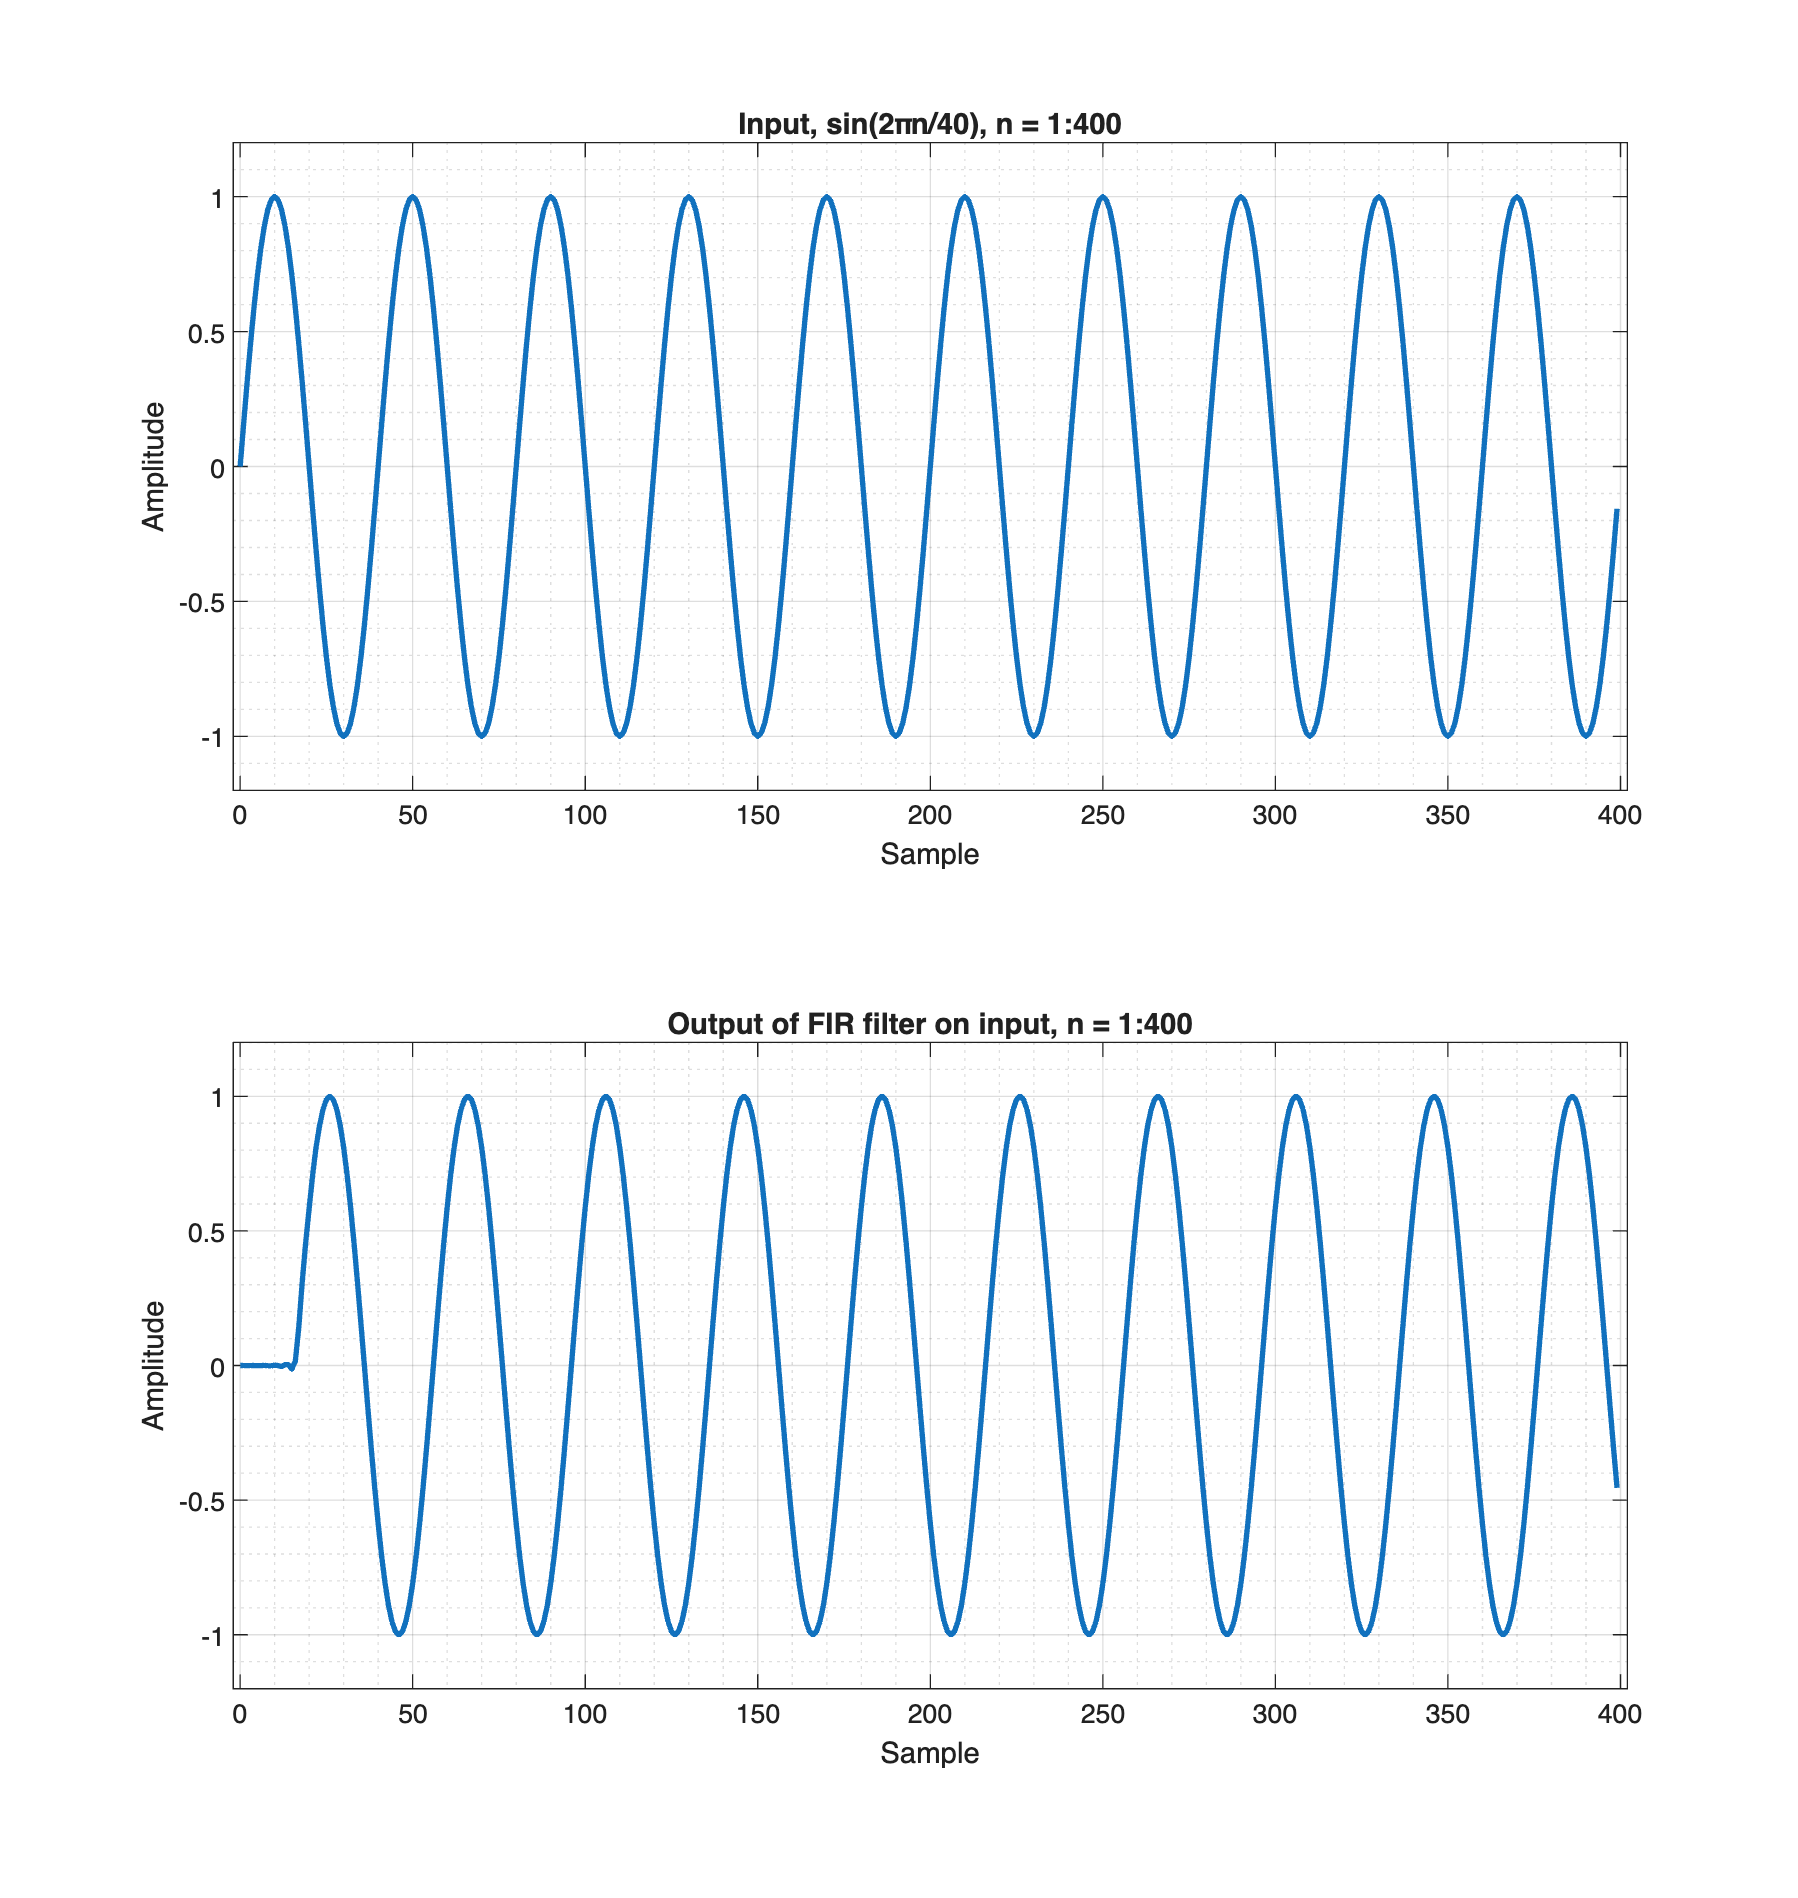

%% Homework 3a, problem 1c
% Reproducing filter from 3a-1a
[M, MM] = estimate_filter_len(fs, f1, f2, A_dB, rppl, "kaiser");

h1 = firpm(M - 1, [0 f1 f2 fs/2] / (fs/2), [1 1 0 0], [w1 w2]);

filter_input_output_plots(n, 400, h1, x_a, "sin(2πn/40)");

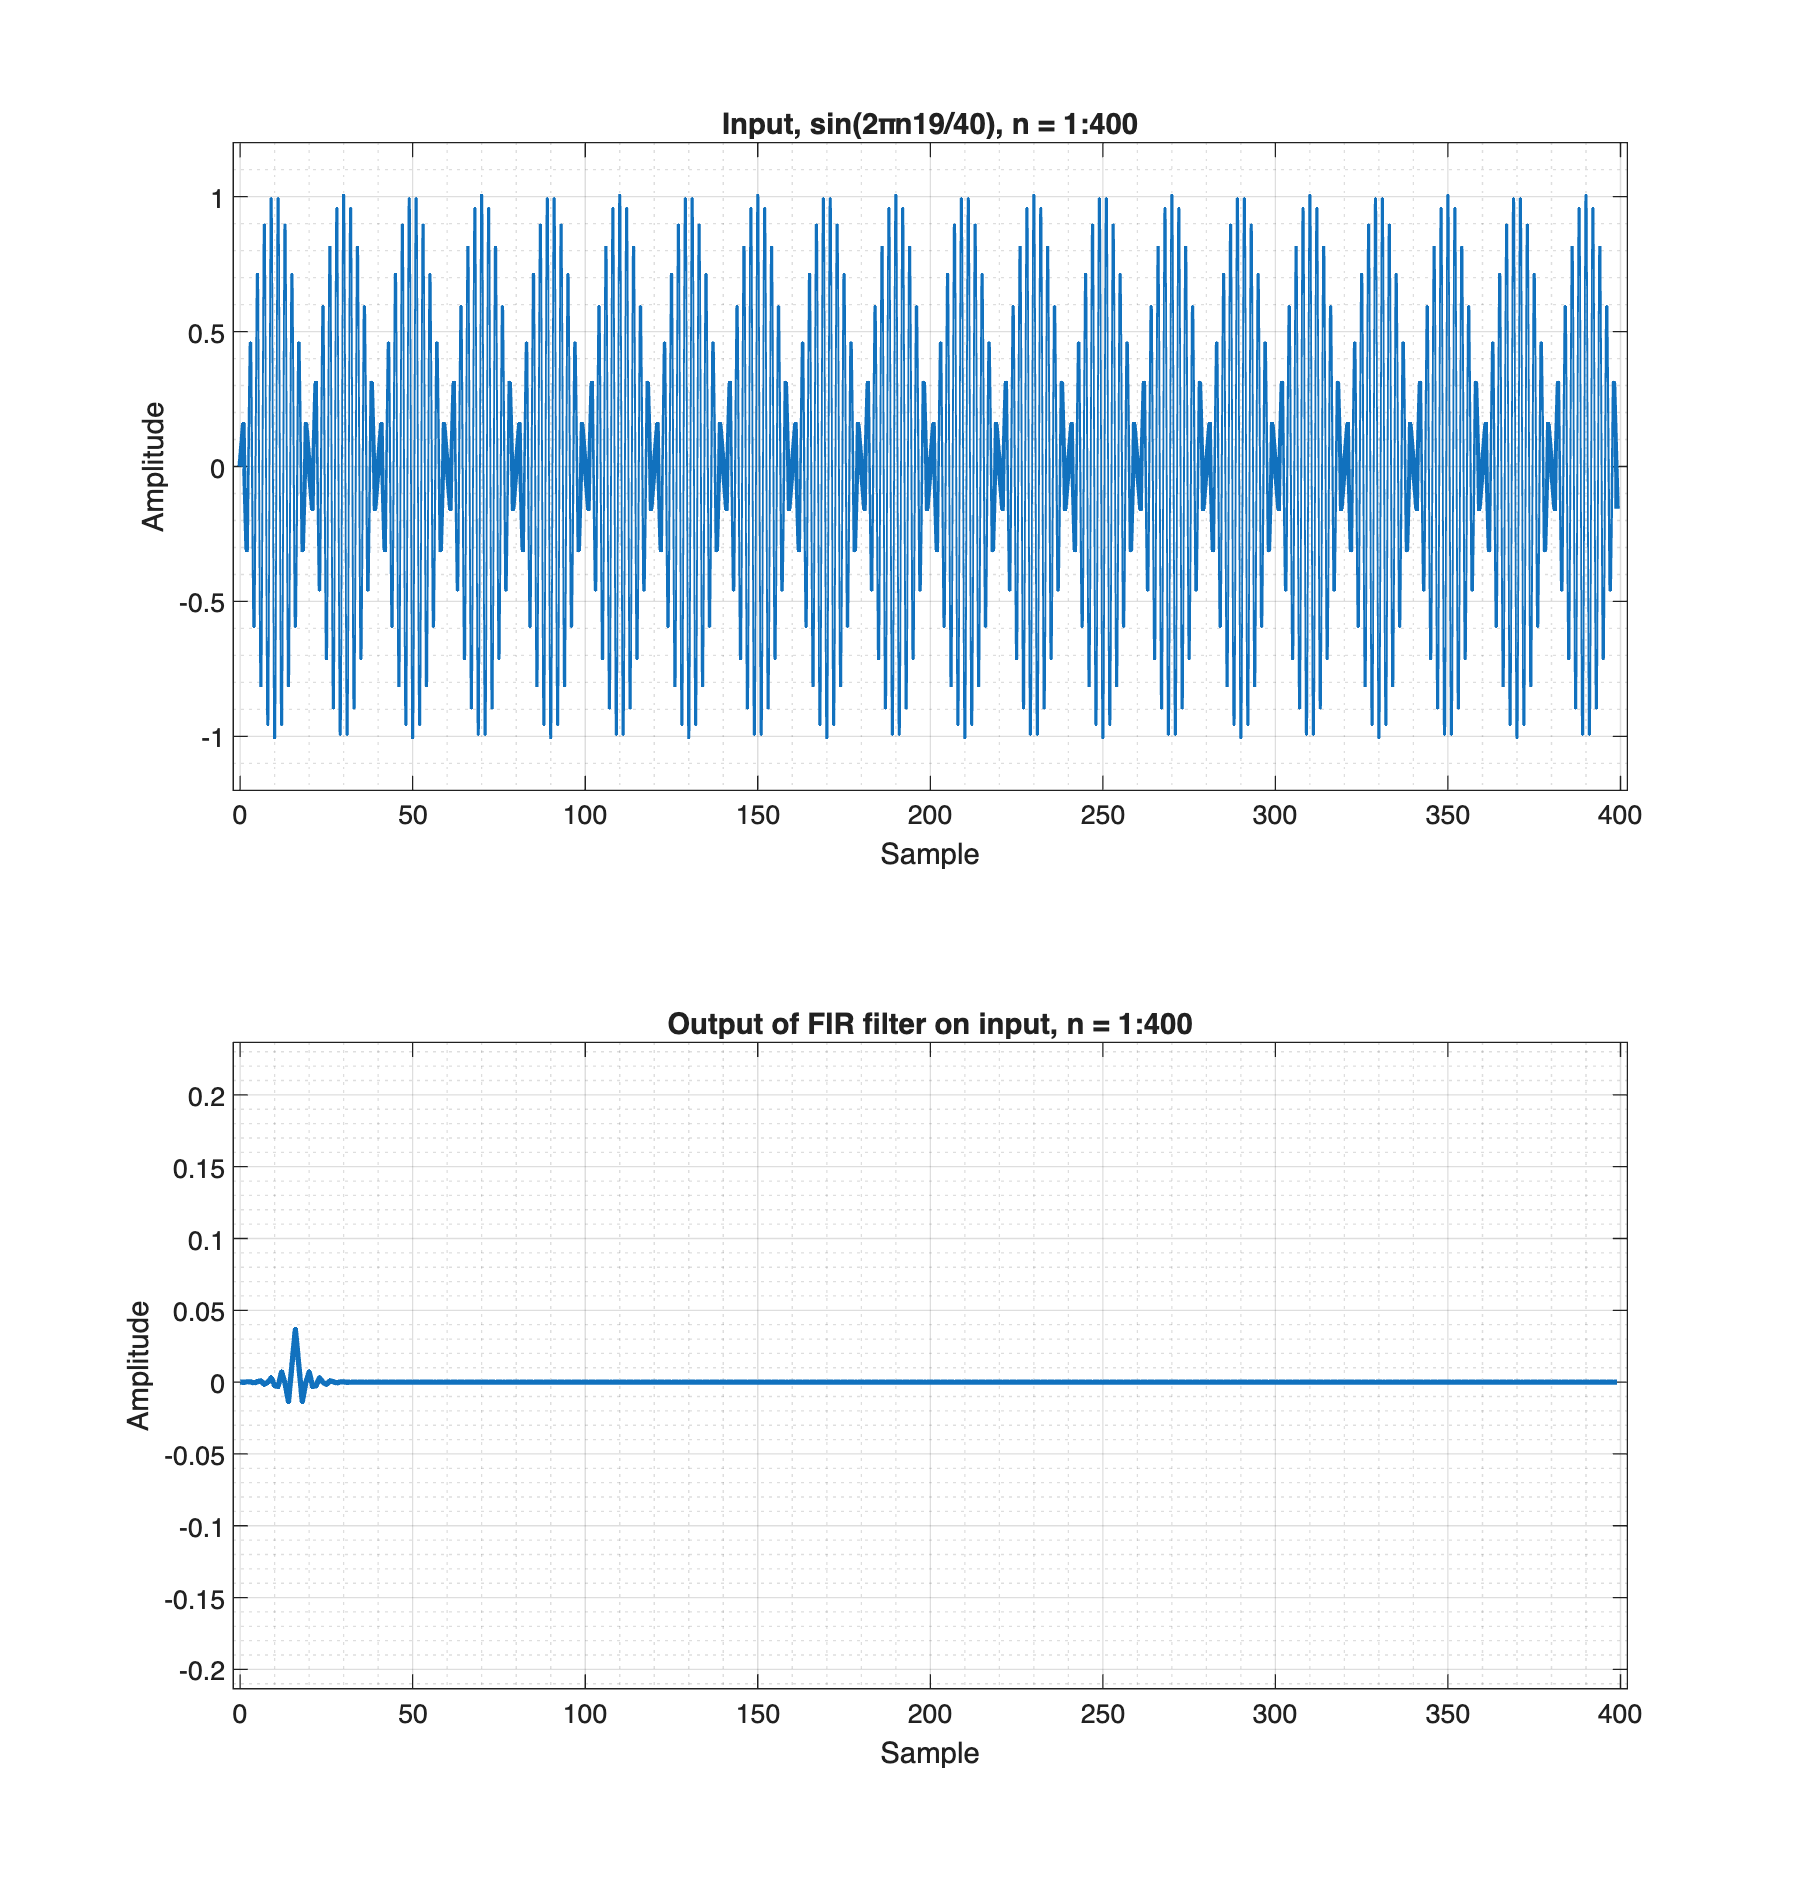

filter_input_output_plots(n, 400, h1, x_b, "sin(2πn19/40)");

The time delays in the output for all 3 experiments are due to the inherent causal (output depends on current and past inputs only) nature of the filter - which introduces group delay. The impulse response of FIR filter in 1a) is symmetric and hence, the filter is linear phase (delays all frequency components by the same amount). Consequently, delay would be (M - 1) / 2 samples, with M being the filter order.

In the above experiments, M = 33 and the delay is 16 samples. 

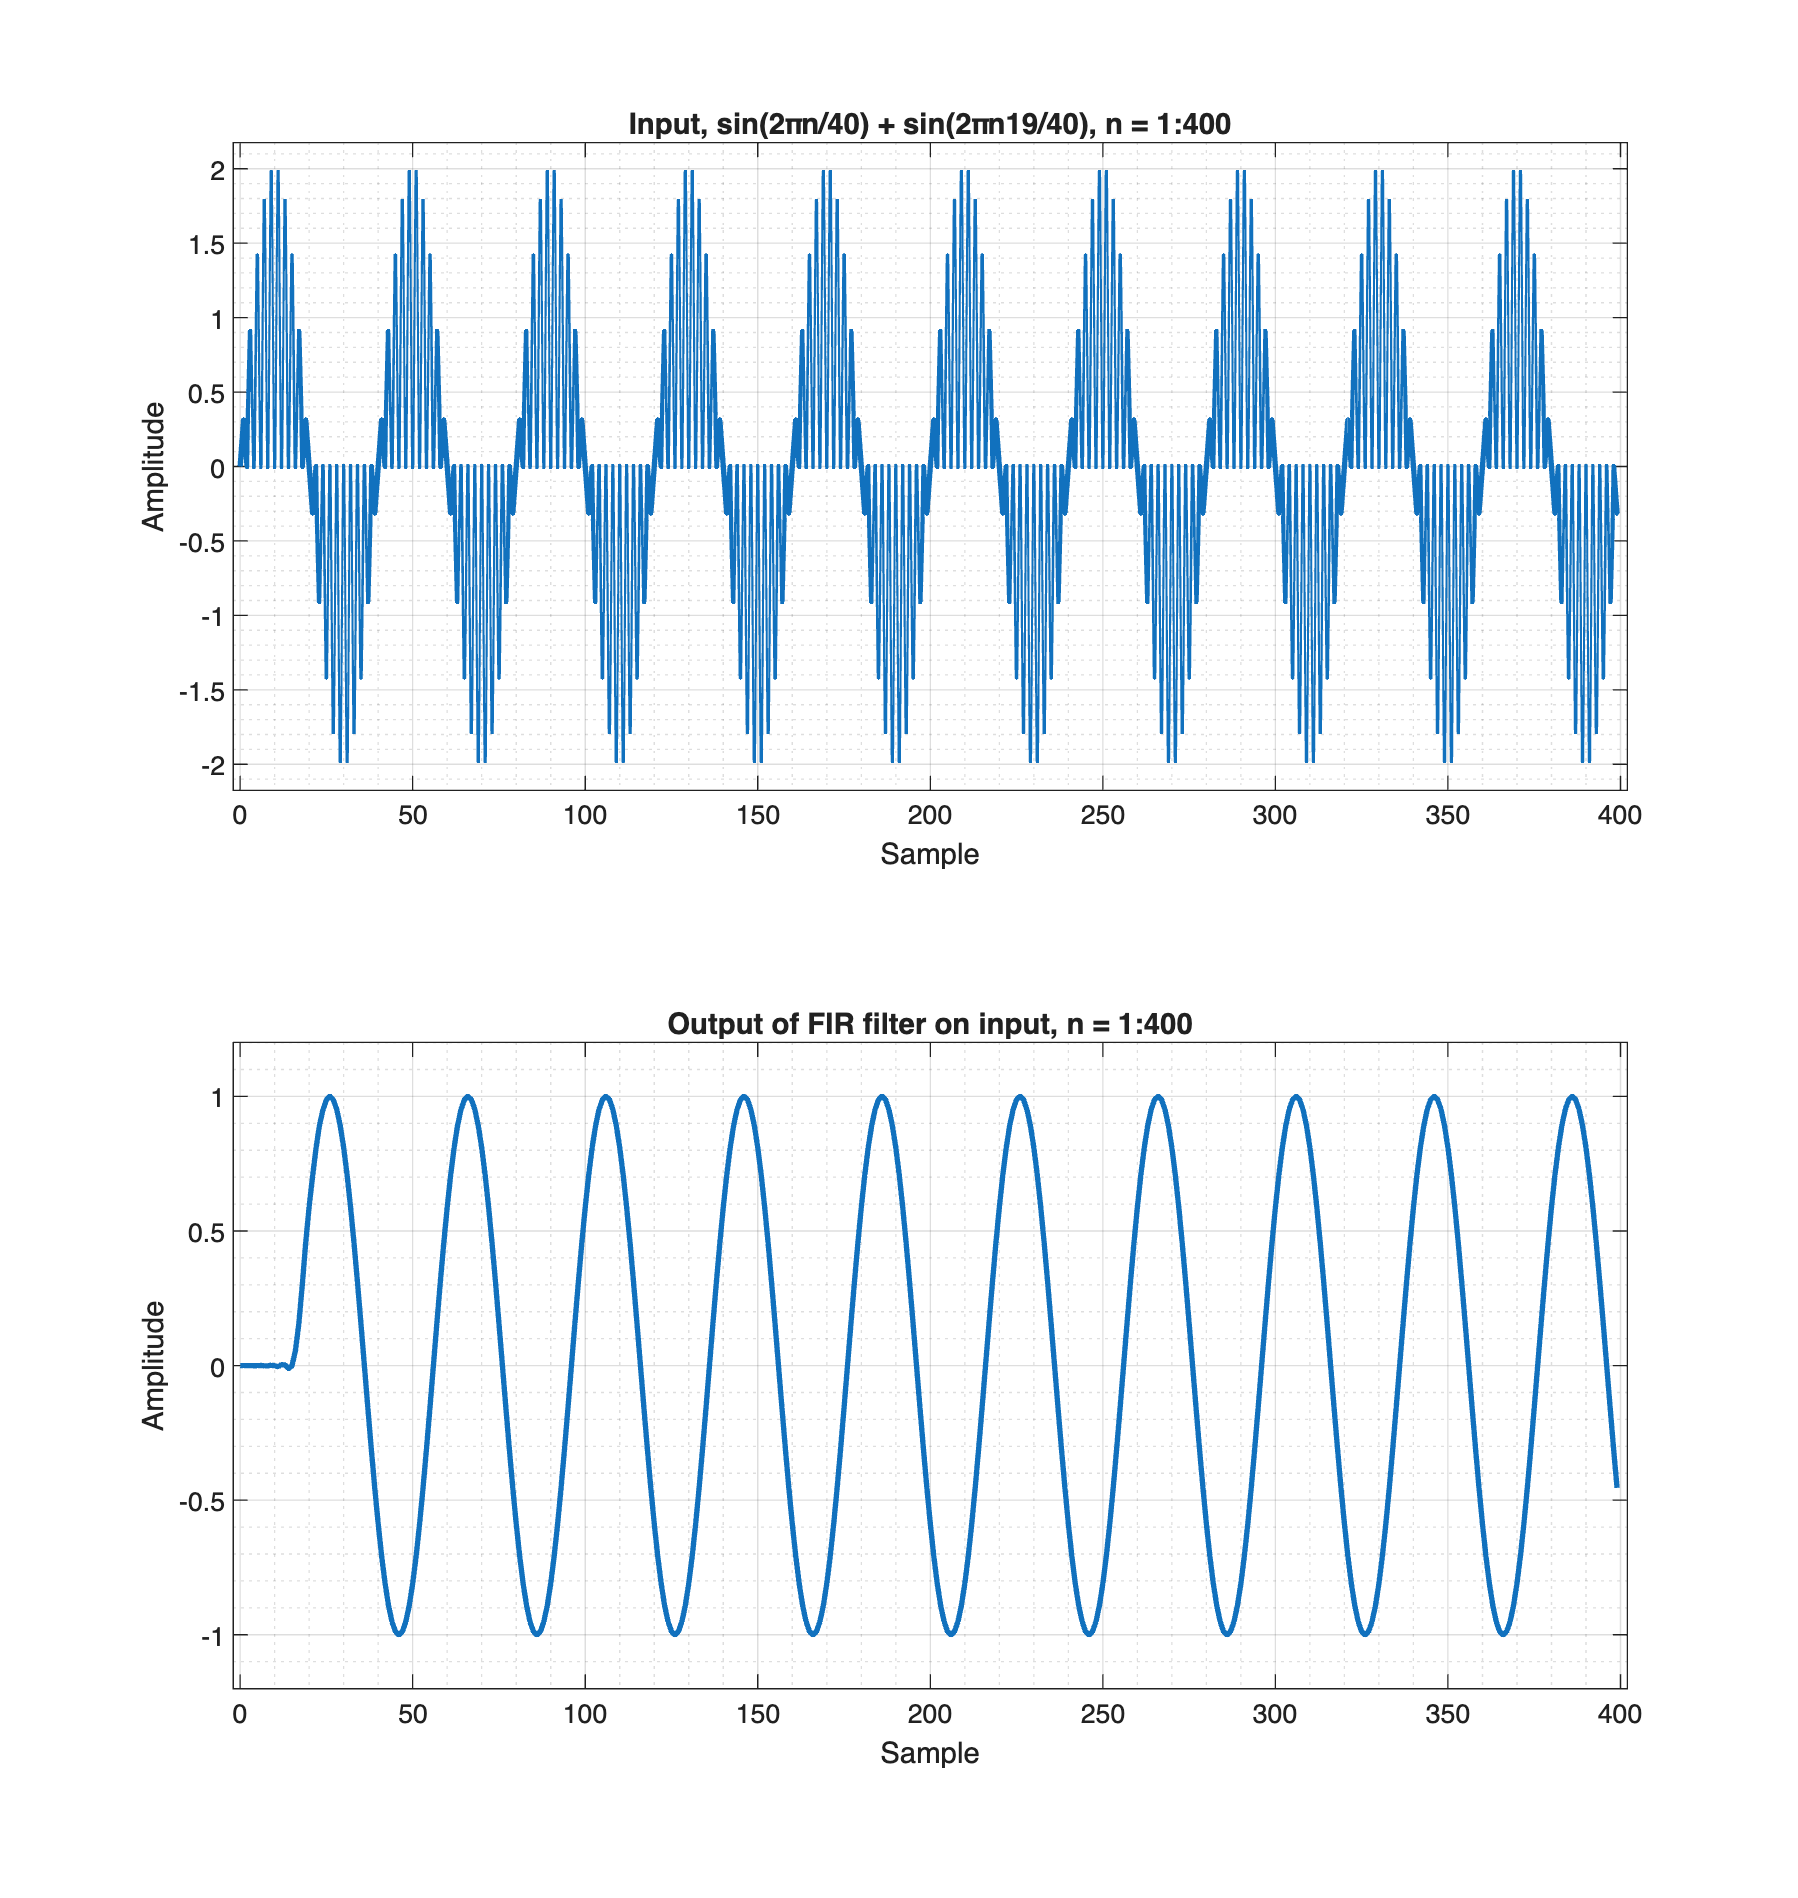

filter_input_output_plots(n, 400, h1, x_c, "sin(2πn/40) + sin(2πn19/40)");

## Homework 3a, problem 1d

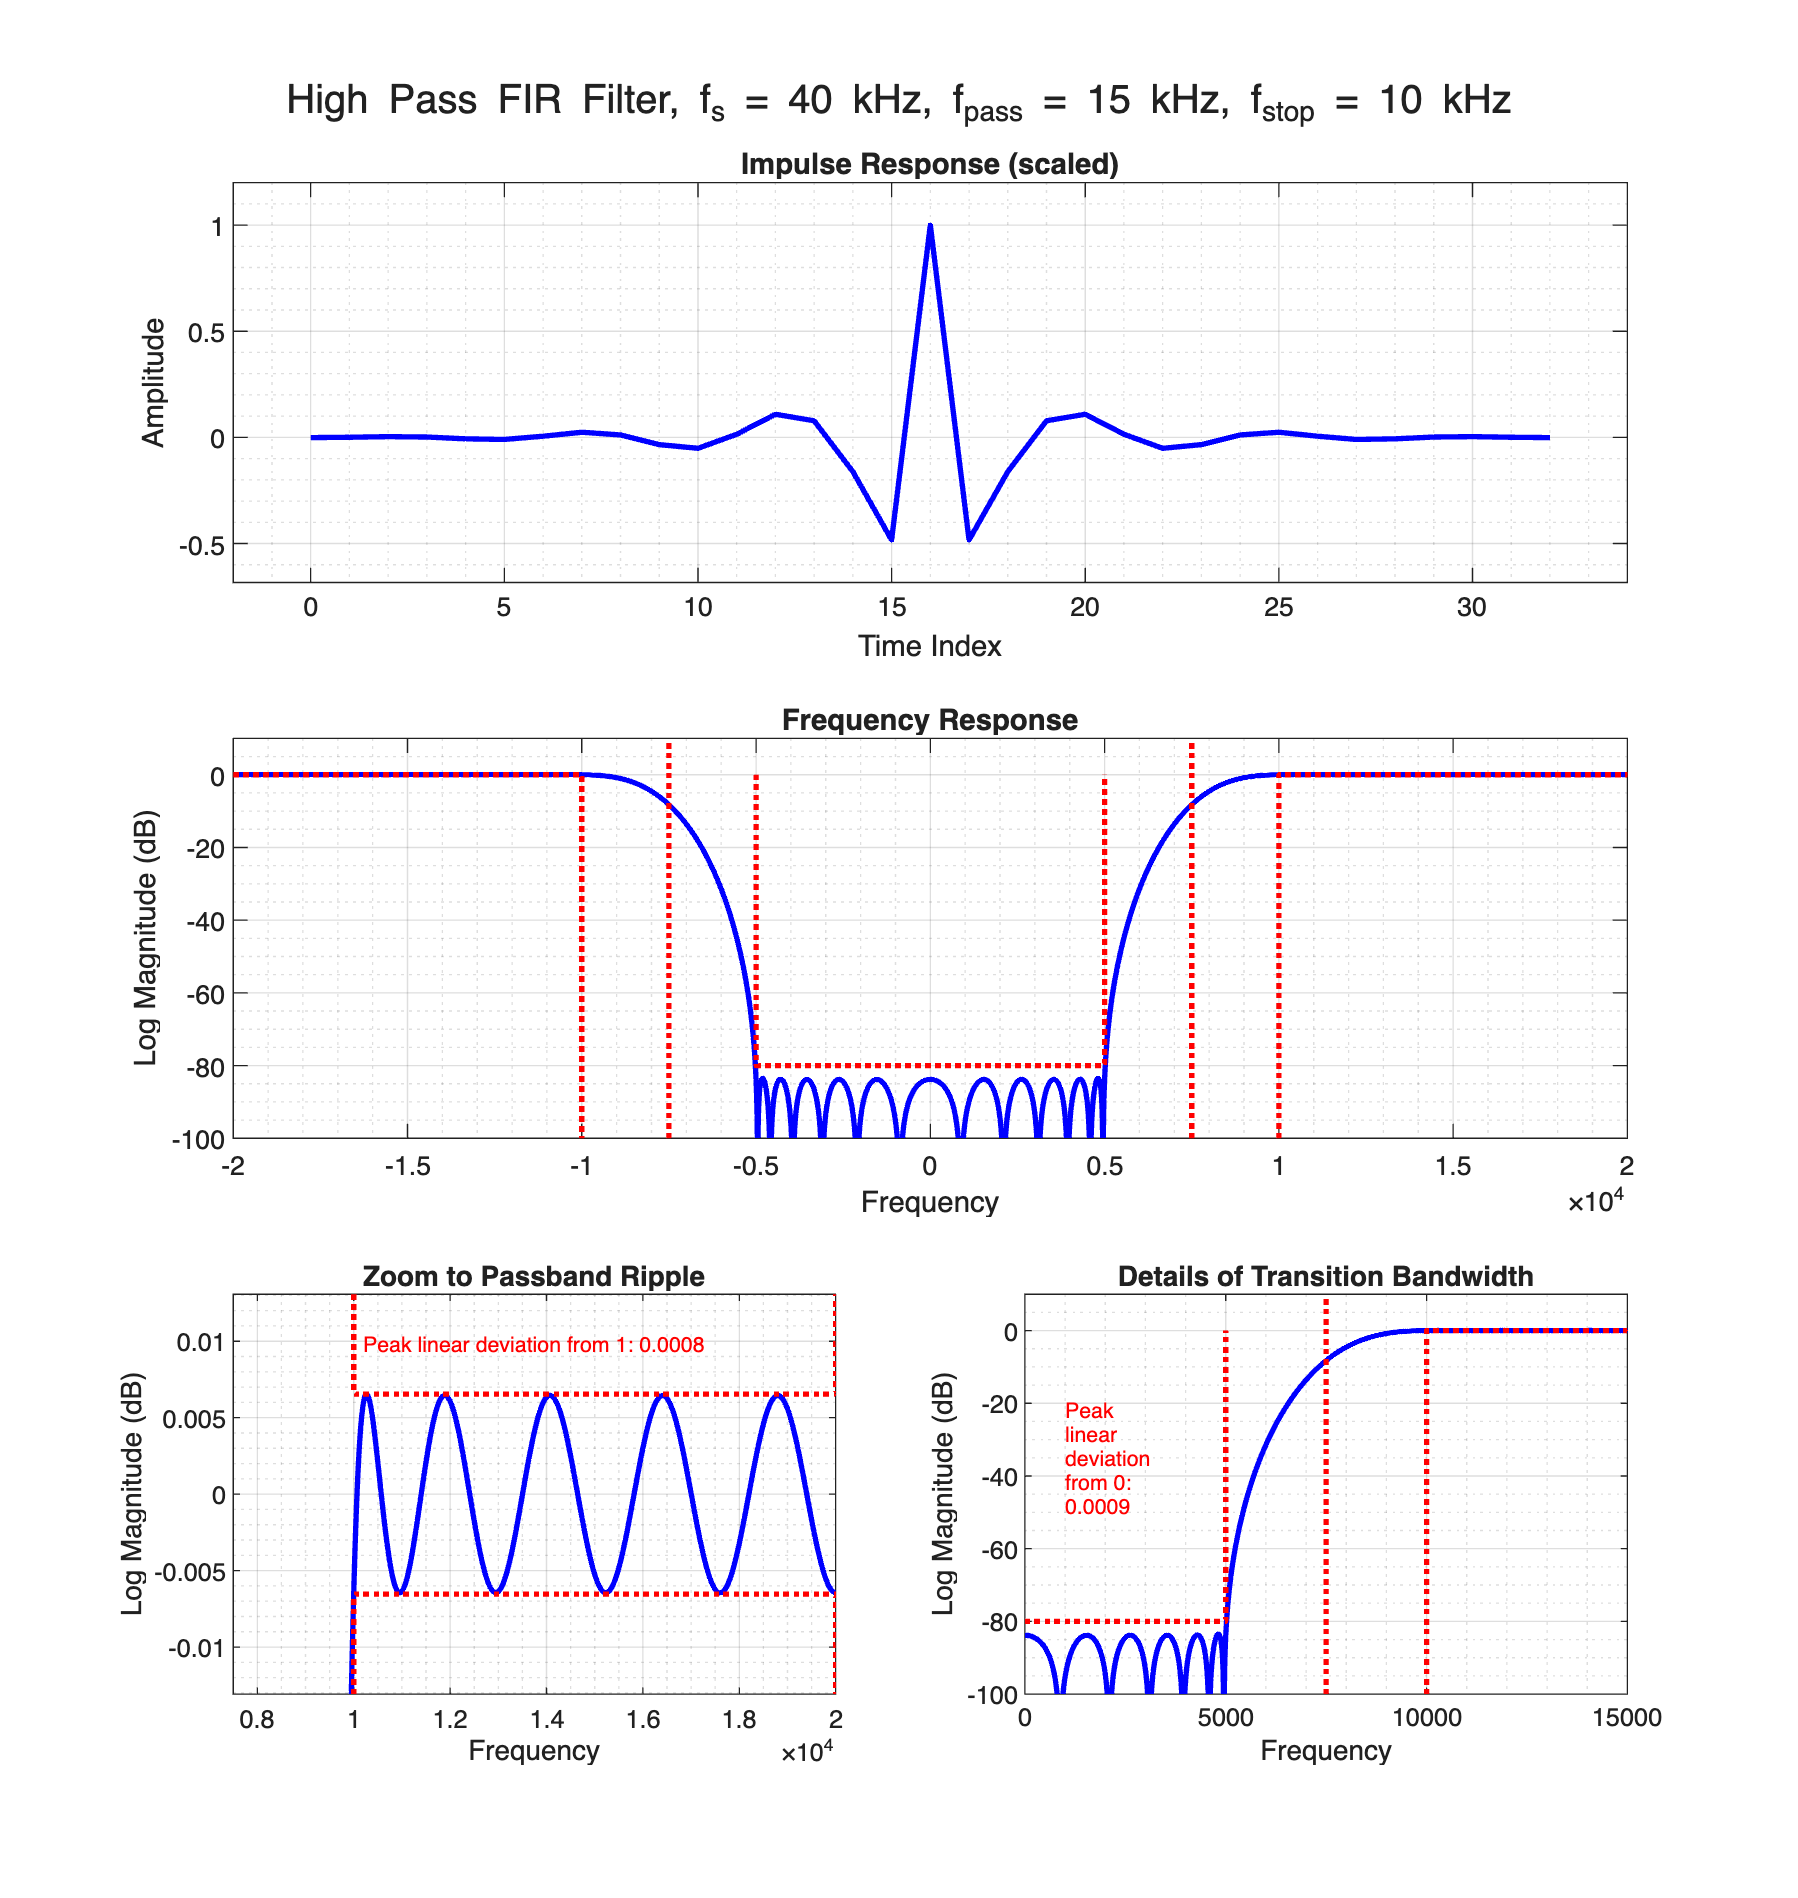

%%Homework 3a, problem 1d
h2 = h1 .* cos(pi * (-MM : MM));

% Scaling for plotting impulse response
scl = max(h2);
h2_scale = h2 / scl;

figure("Position", [0 0 900 950]);
sgtitle(...
  sprintf(...
    "%s, f_s = %d kHz, f_{pass} = %.0f kHz, f_{stop} = %.0f kHz", ...
    "High Pass FIR Filter", fs/1000, f2/1000, f1/1000));
subplot(3, 1, 1)
plot(0 : 2 * MM, h2_scale, "b", "LineWidth", 2);
grid on; grid minor;
axis([-2, 2 * MM + 2, min(h2_scale) - 0.2, max(h2_scale) + 0.2]);
title("Impulse Response (scaled)");
xlabel("Time Index"); ylabel("Amplitude");

f_h2 = fftshift(20 * log10(abs(fft(h2, num_fft))));
subplot(3, 1, 2);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
% Show the stopband frequency and gain
plot(...
  [(-fs/2 + f2) (-fs/2 + f2) (fs/2 - f2) (fs/2 - f2)], ...
  [0 -A_dB -A_dB 0], ":r", "LineWidth", 2);
% Show the passband frequency
plot([-fs/2 (-fs/2 + f1) (-fs/2 + f1)], [0 0 -100], ":r", "LineWidth", 2);
plot([(fs/2 - f1) (fs/2 - f1) fs/2], [-100 0 0], ":r", "LineWidth", 2);
% Show the 6dB frequency (midway between passband and stopband)
f0 = (fs - (f1 + f2)) / 2;
plot([-f0 -f0], [-100 10], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([-fs/2 fs/2 -100 10]);
title("Frequency Response");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

% Checking passband ripple in range (start_idx:end_idx) corresponding to the
% positive frequency passband frequency response
start_idx = (1 - (fs/2 - f1) / fs) * num_fft;
end_idx = num_fft;
max_dev = max(f_h2(start_idx:end_idx));
% Calculate the peak linear deviation in passband
pk_lin_dev_passband = abs(1 - 10 ^ (max_dev / 20));

subplot(3, 2, 5);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
y_lim = 2 * max_dev; % y-axis limit, scaled according to the peak deviation
plot(...
  [(fs/2 - f1) (fs/2 - f1) fs/2 fs/2], [y_lim max_dev max_dev y_lim], ...
  ":r", "LineWidth", 2);
plot(...
  [(fs/2 - f1) (fs/2 - f1) fs/2 fs/2], [-y_lim -max_dev -max_dev -y_lim], ...
  ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([f0 fs/2 -y_lim y_lim]);
text(...
  (fs/2 - f1) + 200, 1.5 * max_dev, ...
  sprintf("Peak linear deviation from 1: %.4f", pk_lin_dev_passband), ...
  "Color", "red", "FontSize", 8);
title("Zoom to Passband Ripple");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

% Checking stopband ripple in range (start_idx:end_idx) corresponding to the
% positive frequency stopband frequency response
start_idx = num_fft / 2;
end_idx = start_idx + ((f1 / fs) * num_fft);
max_dev = max(f_h2(start_idx:end_idx));
% Calculate the peak linear deviation in stopband
pk_lin_dev_stopband = abs(1 - 10 ^ (max_dev / 20));

subplot(3, 2, 6);
plot((-0.5 : 1/num_fft : 0.5 - 1/num_fft) * fs, f_h2, "b", "LineWidth", 2);
hold on;
plot([(fs/2 - f1) (fs/2 - f1) fs/2], [-100 0 0], ":r", "LineWidth", 2);
f0 = (fs - (f1 + f2)) / 2;
plot([0 (fs/2 - f2) (fs/2 - f2)], [-80 -80 0], ":r", "LineWidth", 2);
plot([f0 f0], [-100 10], ":r", "LineWidth", 2);
hold off;
grid on; grid minor;
axis([0. f2 -100 10]);
text(...
  f2/15, -35, ...
  sprintf("Peak\nlinear\ndeviation\nfrom 0:\n%.4f", pk_lin_dev_stopband), ...
  "Color", "red", "FontSize", 8);
title("Details of Transition Bandwidth");
xlabel("Frequency"); ylabel("Log Magnitude (dB)");

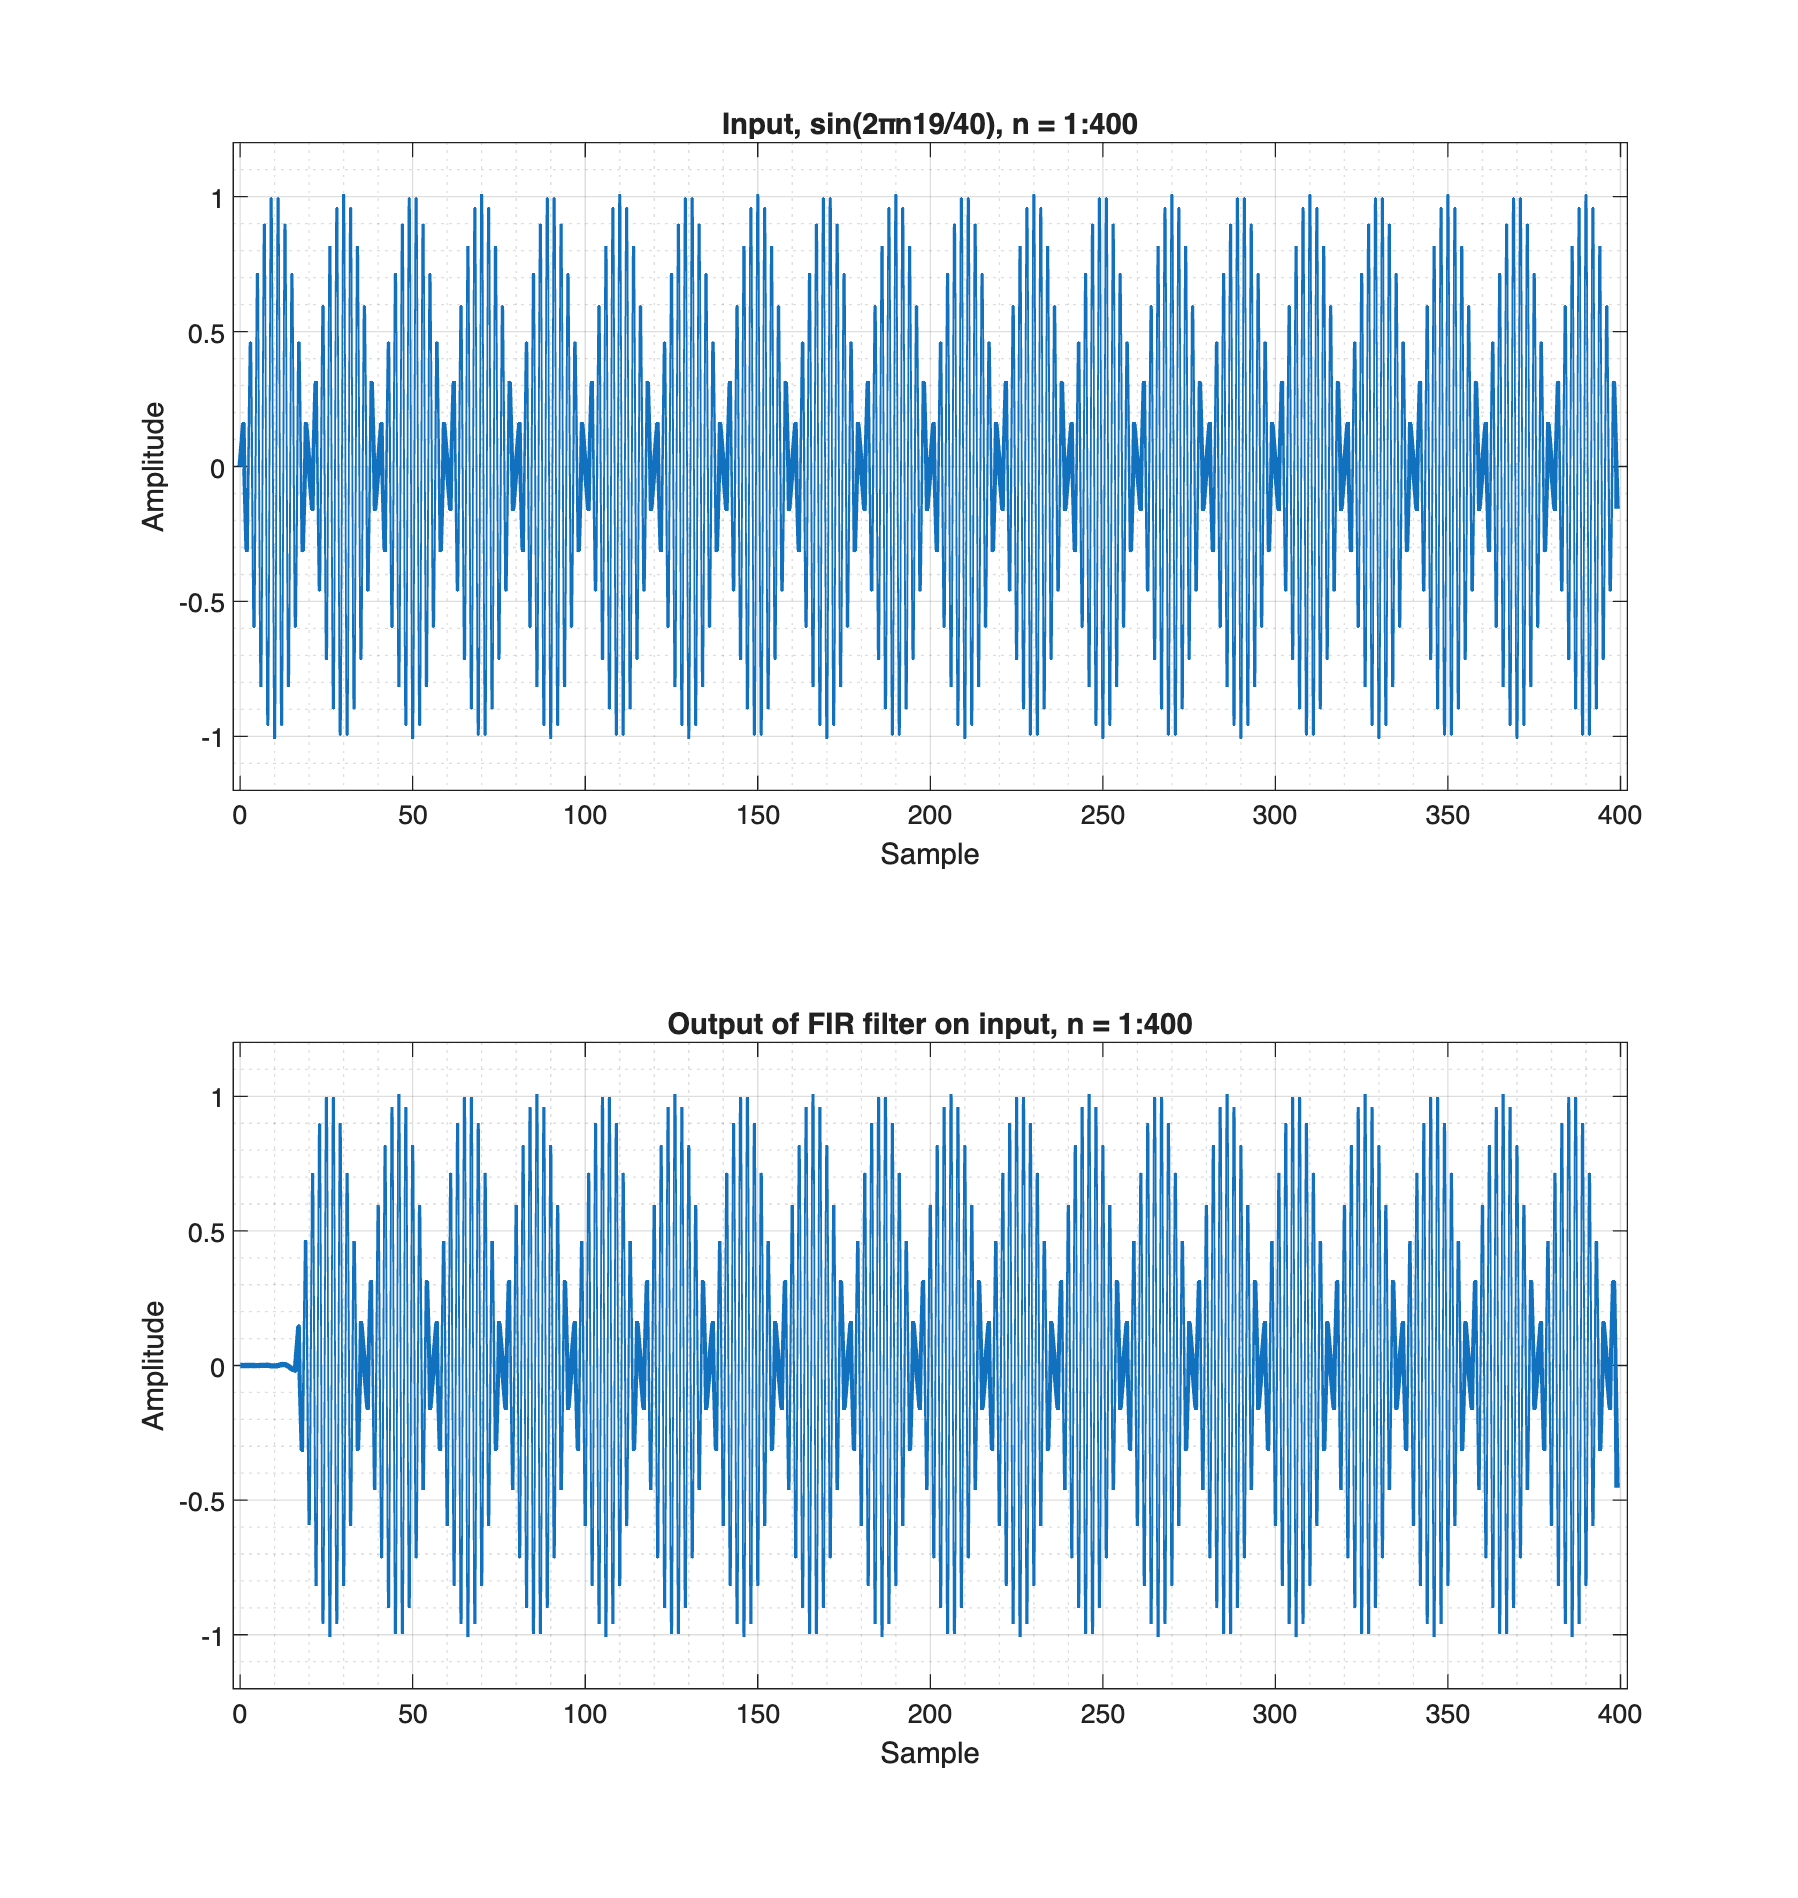


filter_input_output_plots(n, 400, h2, x_b, "sin(2πn19/40)");

## Homework 3a, problem 1e

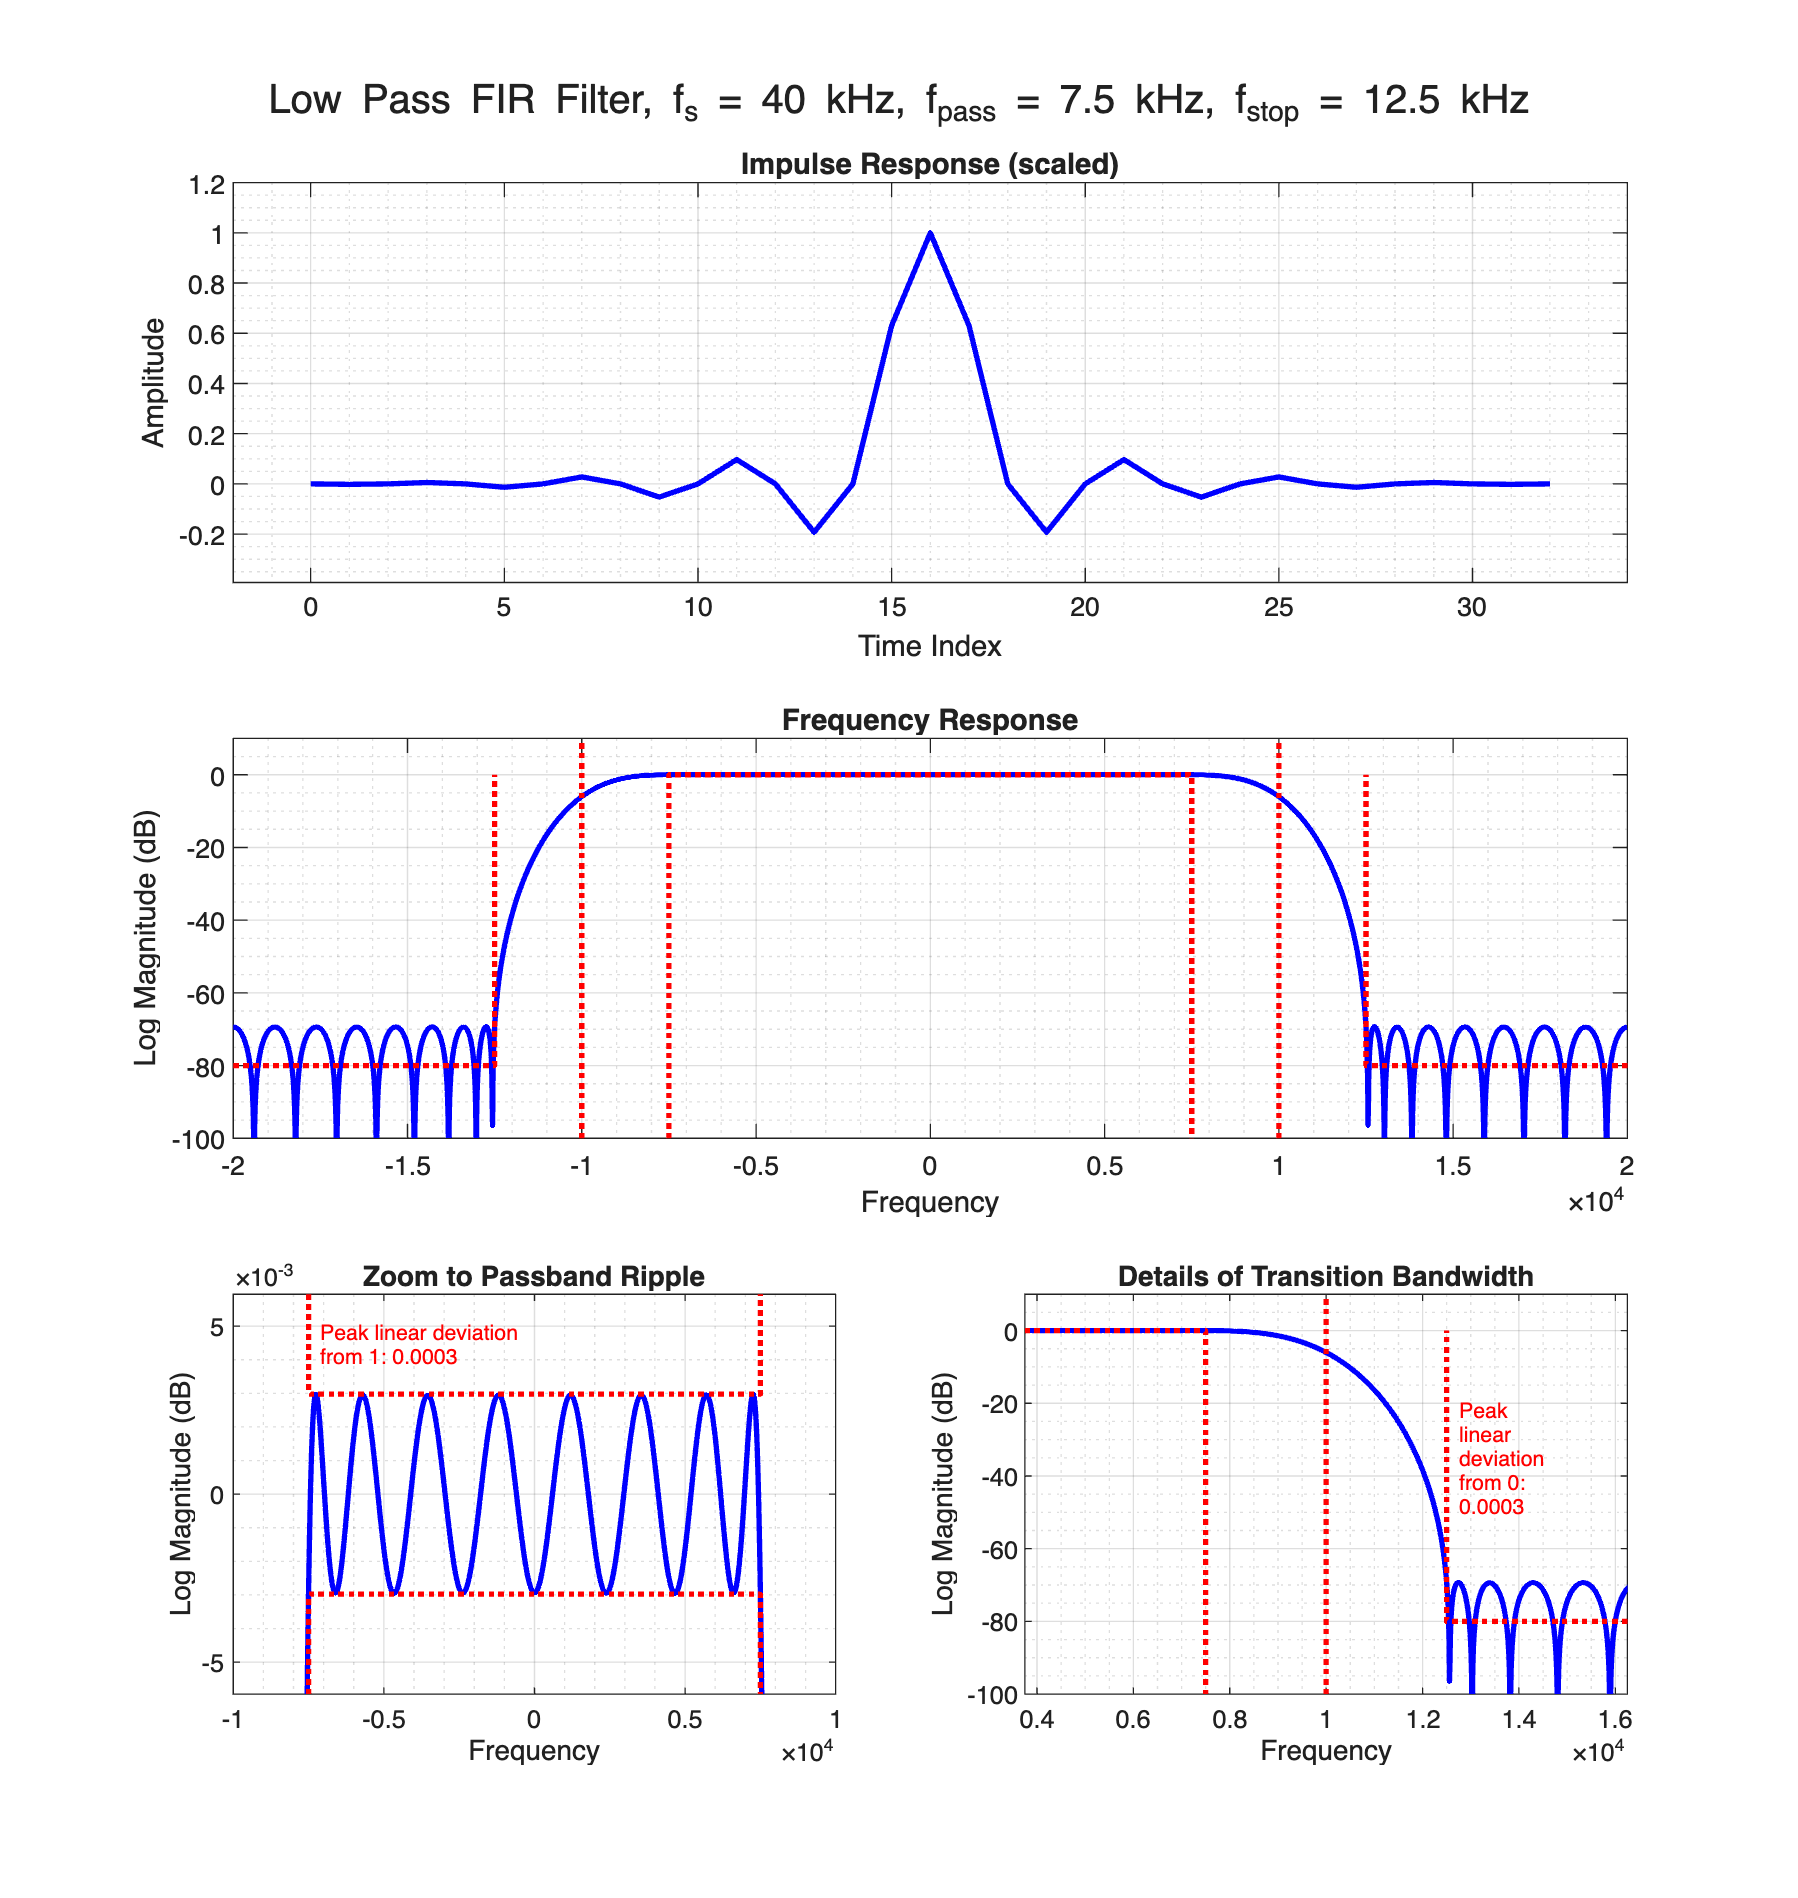

%% Homework 3a, problem 1e
fs   = 40000; % Sample rate
f1   = 7500;  % Passband frequency
f2   = 12500; % Stopband frequency
A_dB = 80;    % Stopband attenuation
rppl = 0.01;  % Passband & stopband ripple (in dB)

[M, MM] = estimate_filter_len(fs, f1, f2, A_dB, rppl, "kaiser");

% Assign the weights
w1 = 1;
w2 = 1;

h1 = firpm(M - 1, [0 f1 f2 fs/2] / (fs/2), [1 1 0 0], [w1 w2]);

filter_plots(MM, fs, f1, f2, A_dB, h1);

The alternate coefficients are not quite zero valued for this half band filter. This will be due to floating point limitations/finite precision arithmetic.

## Homework 3b, problem 1

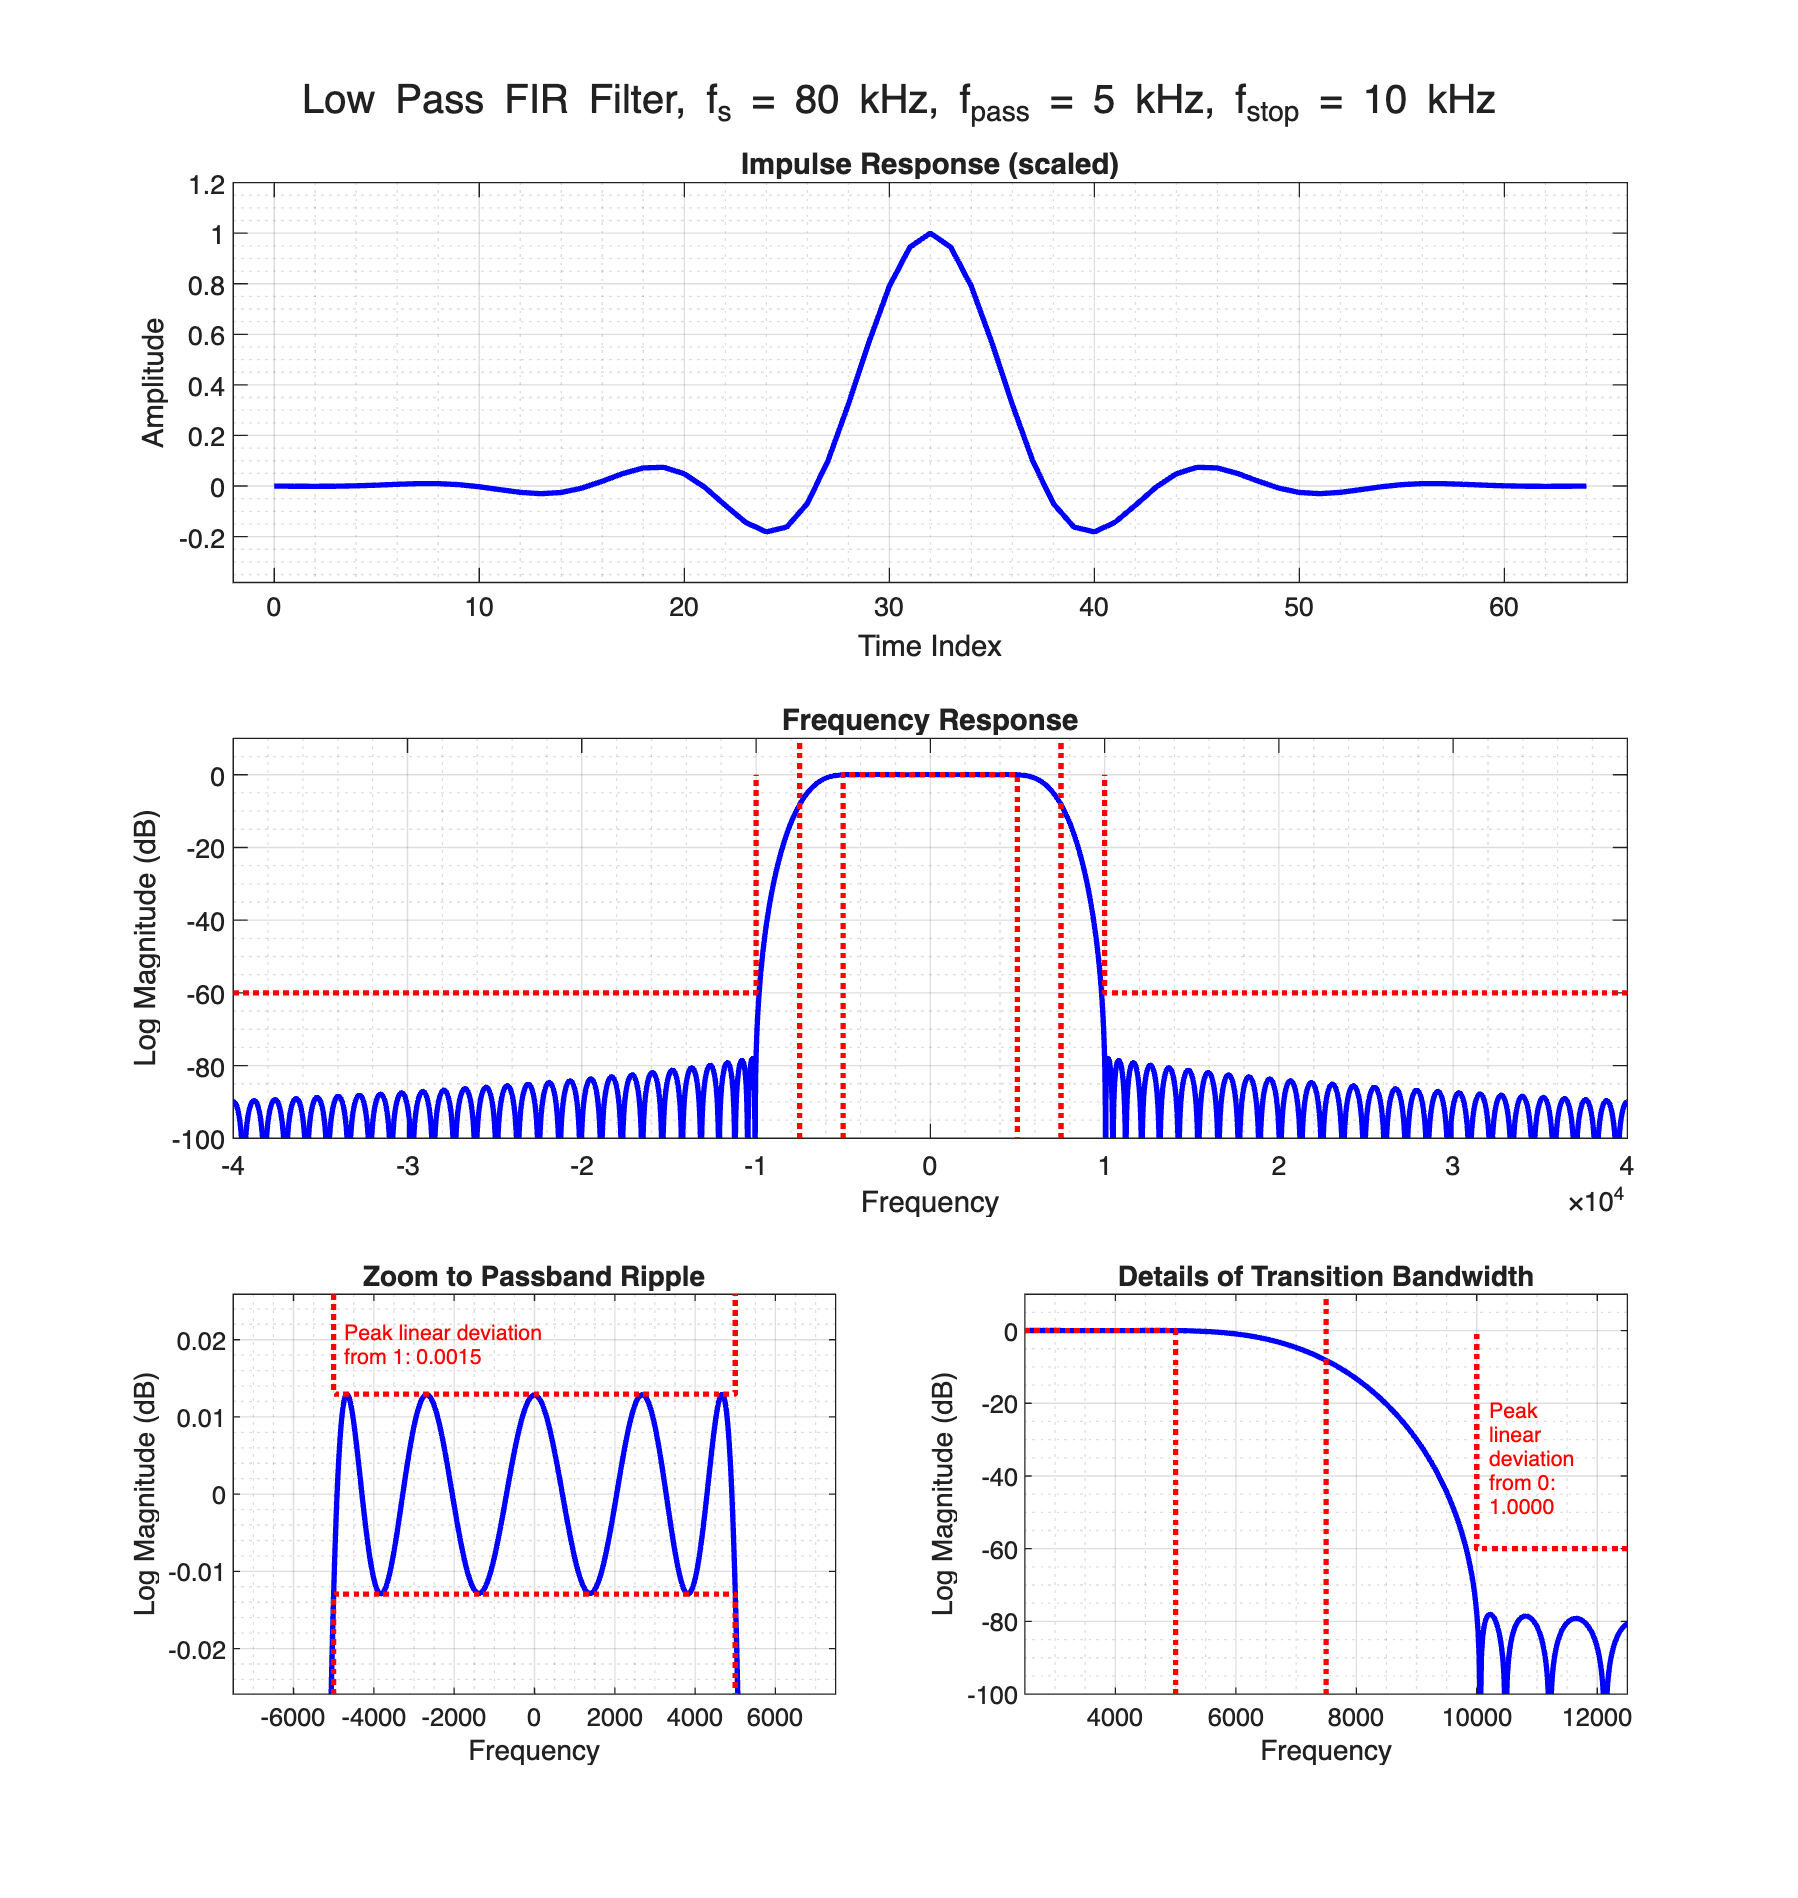

%% Homework 3b, problem 1
% Helper function to design an FIR filter with given specifications and plot
% the impulse response, frequency response (in log magnitude and with the
% spectral mask), zoom to passband ripple and zoom to positive frequency
% transition bandwidth.
%
% Parameters:
%   fs - Sample rate (in kHz)
%   f_pass - Passband frequency (in kHz)
%   f_stop - Stopband frequency (in kHz)
%   pass_rppl - Passband ripple (in dB)
%   A_db - Stopband attenuation (in dB)
function filter_design_and_plot(fs, f_pass, f_stop, pass_rppl, A_dB)
  [M, MM] = estimate_filter_len(fs, f_pass, f_stop, A_dB, NaN, "harris");

  delta_2 = 10 ^ (-A_dB / 20);
  delta_1 = (10 ^ (pass_rppl / 20)) - 1;
  w1 = 1;
  w2 = delta_1 / delta_2;

  % Design the filter using modified Remez algorithm
  h1 = ...
    firpm(...
      M - 1, [0 f_pass f_stop fs/2] / (fs/2), {"myfrf", [1 1 0 0]}, [w1 w2]);

  filter_plots(MM, fs * 1000, f_pass * 1000, f_stop * 1000, A_dB, h1);
end

filter_design_and_plot(80, 5, 10, 0.1, 60);

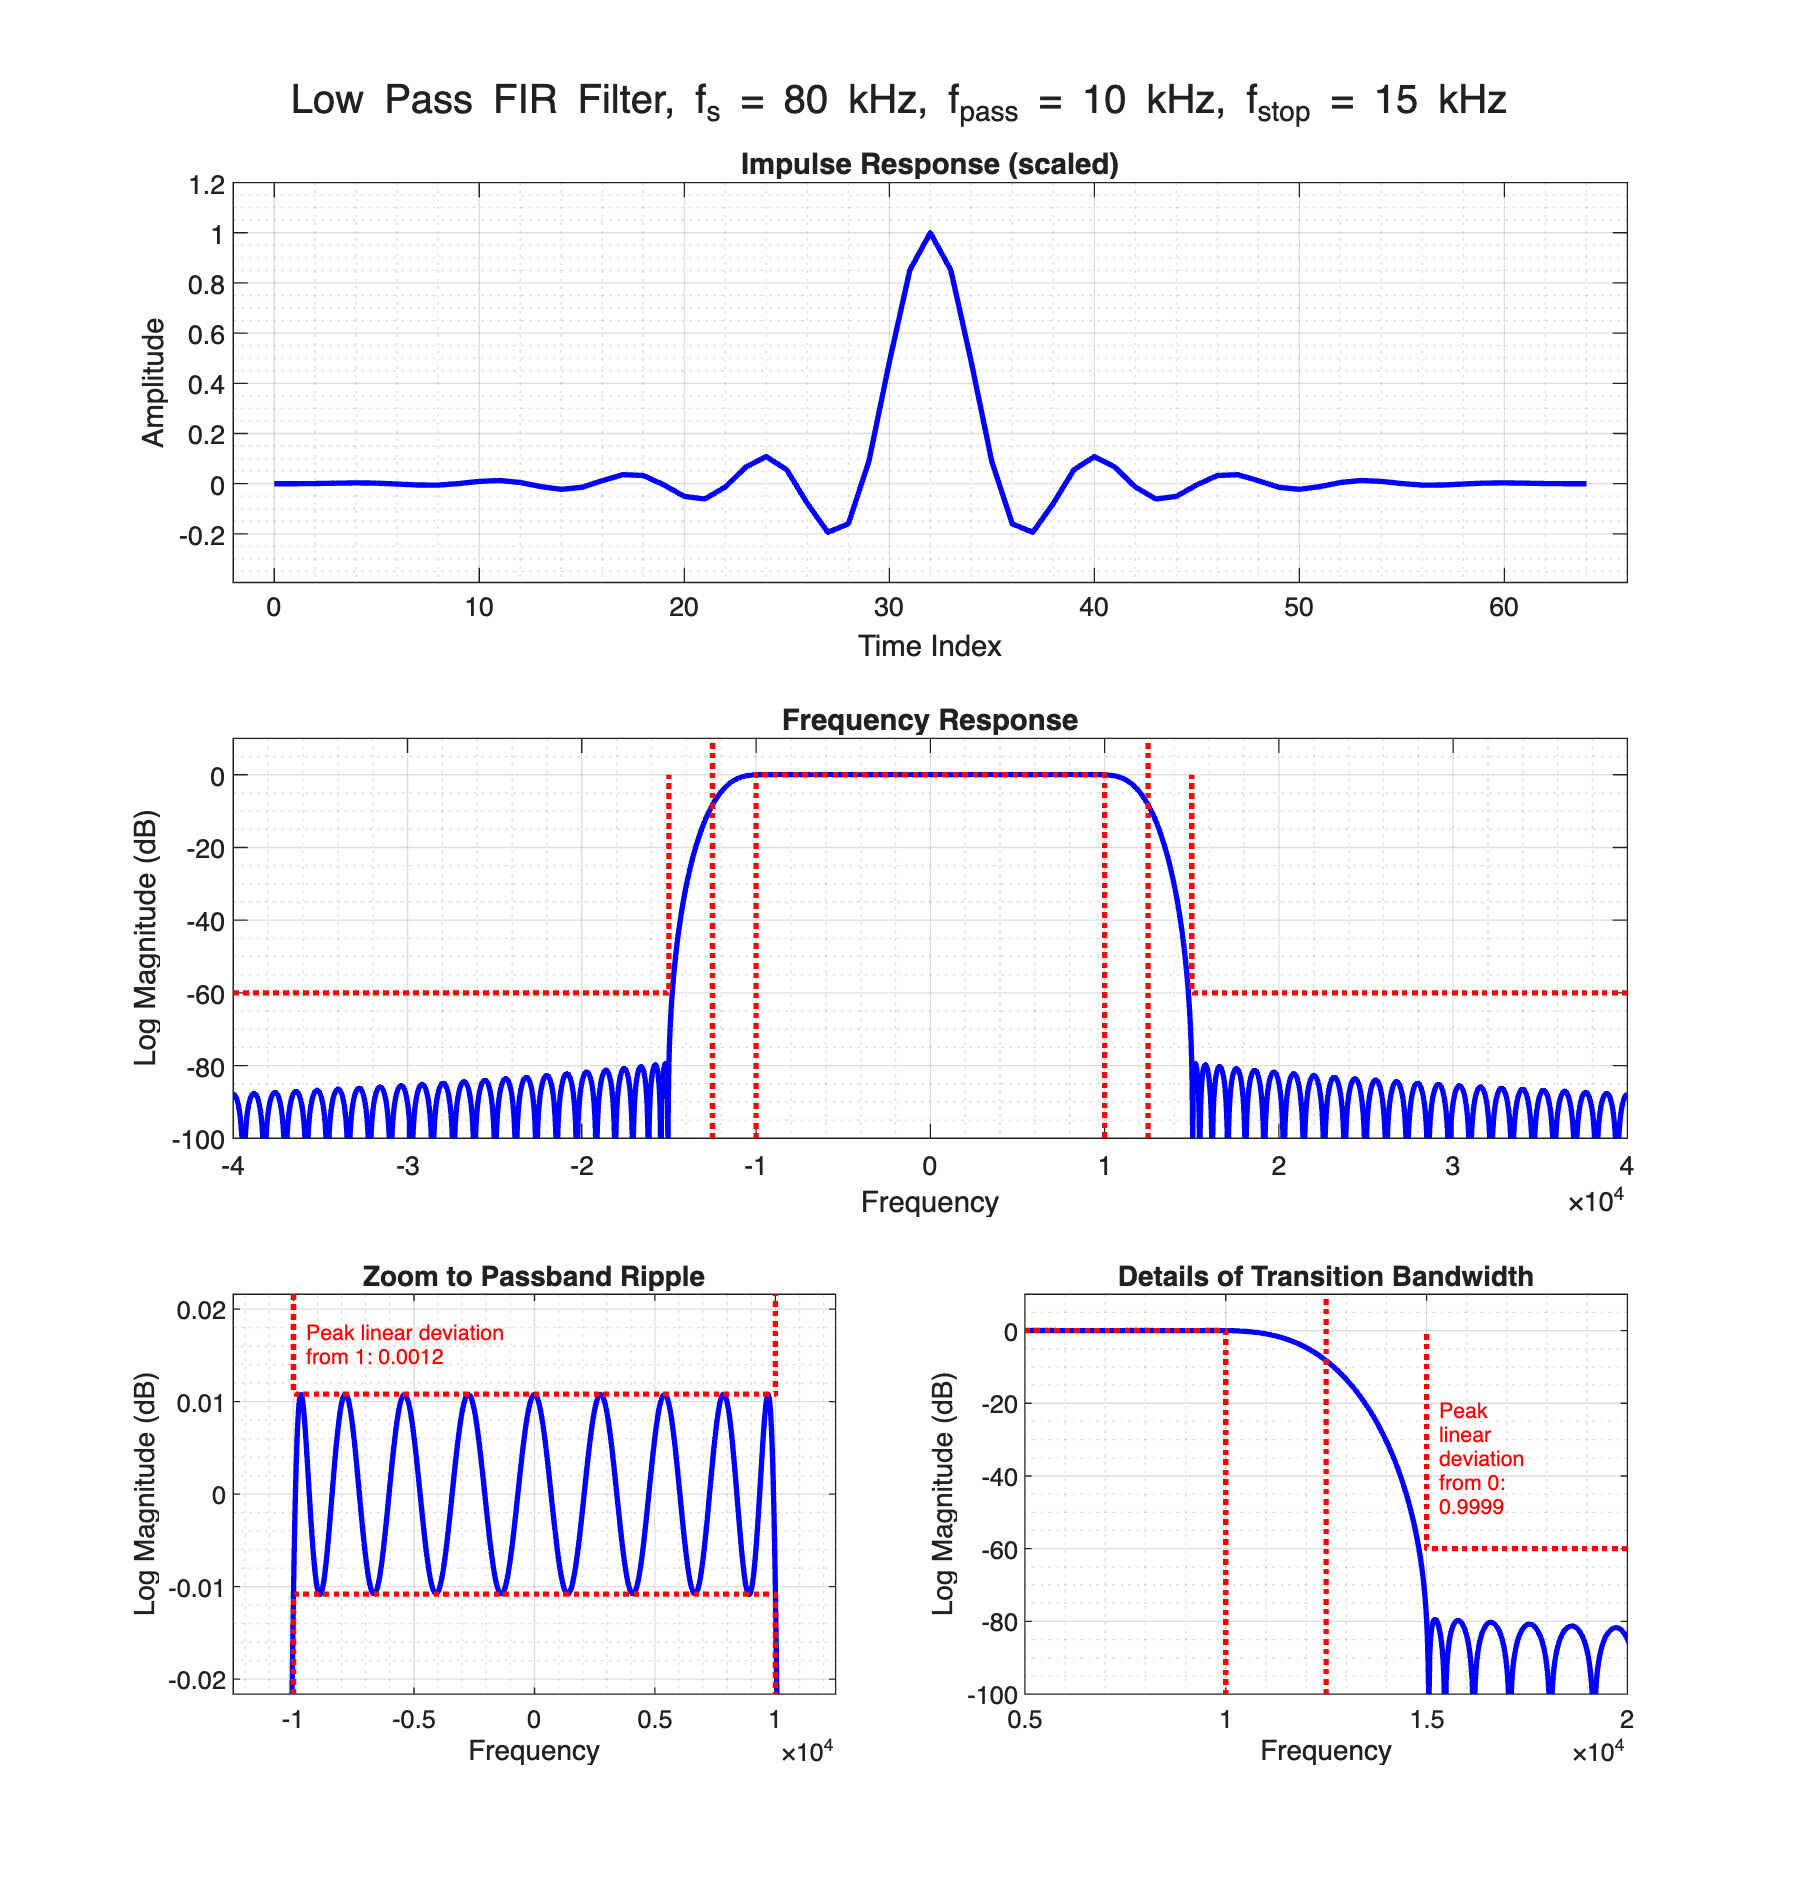

filter_design_and_plot(80, 10, 15, 0.1, 60);

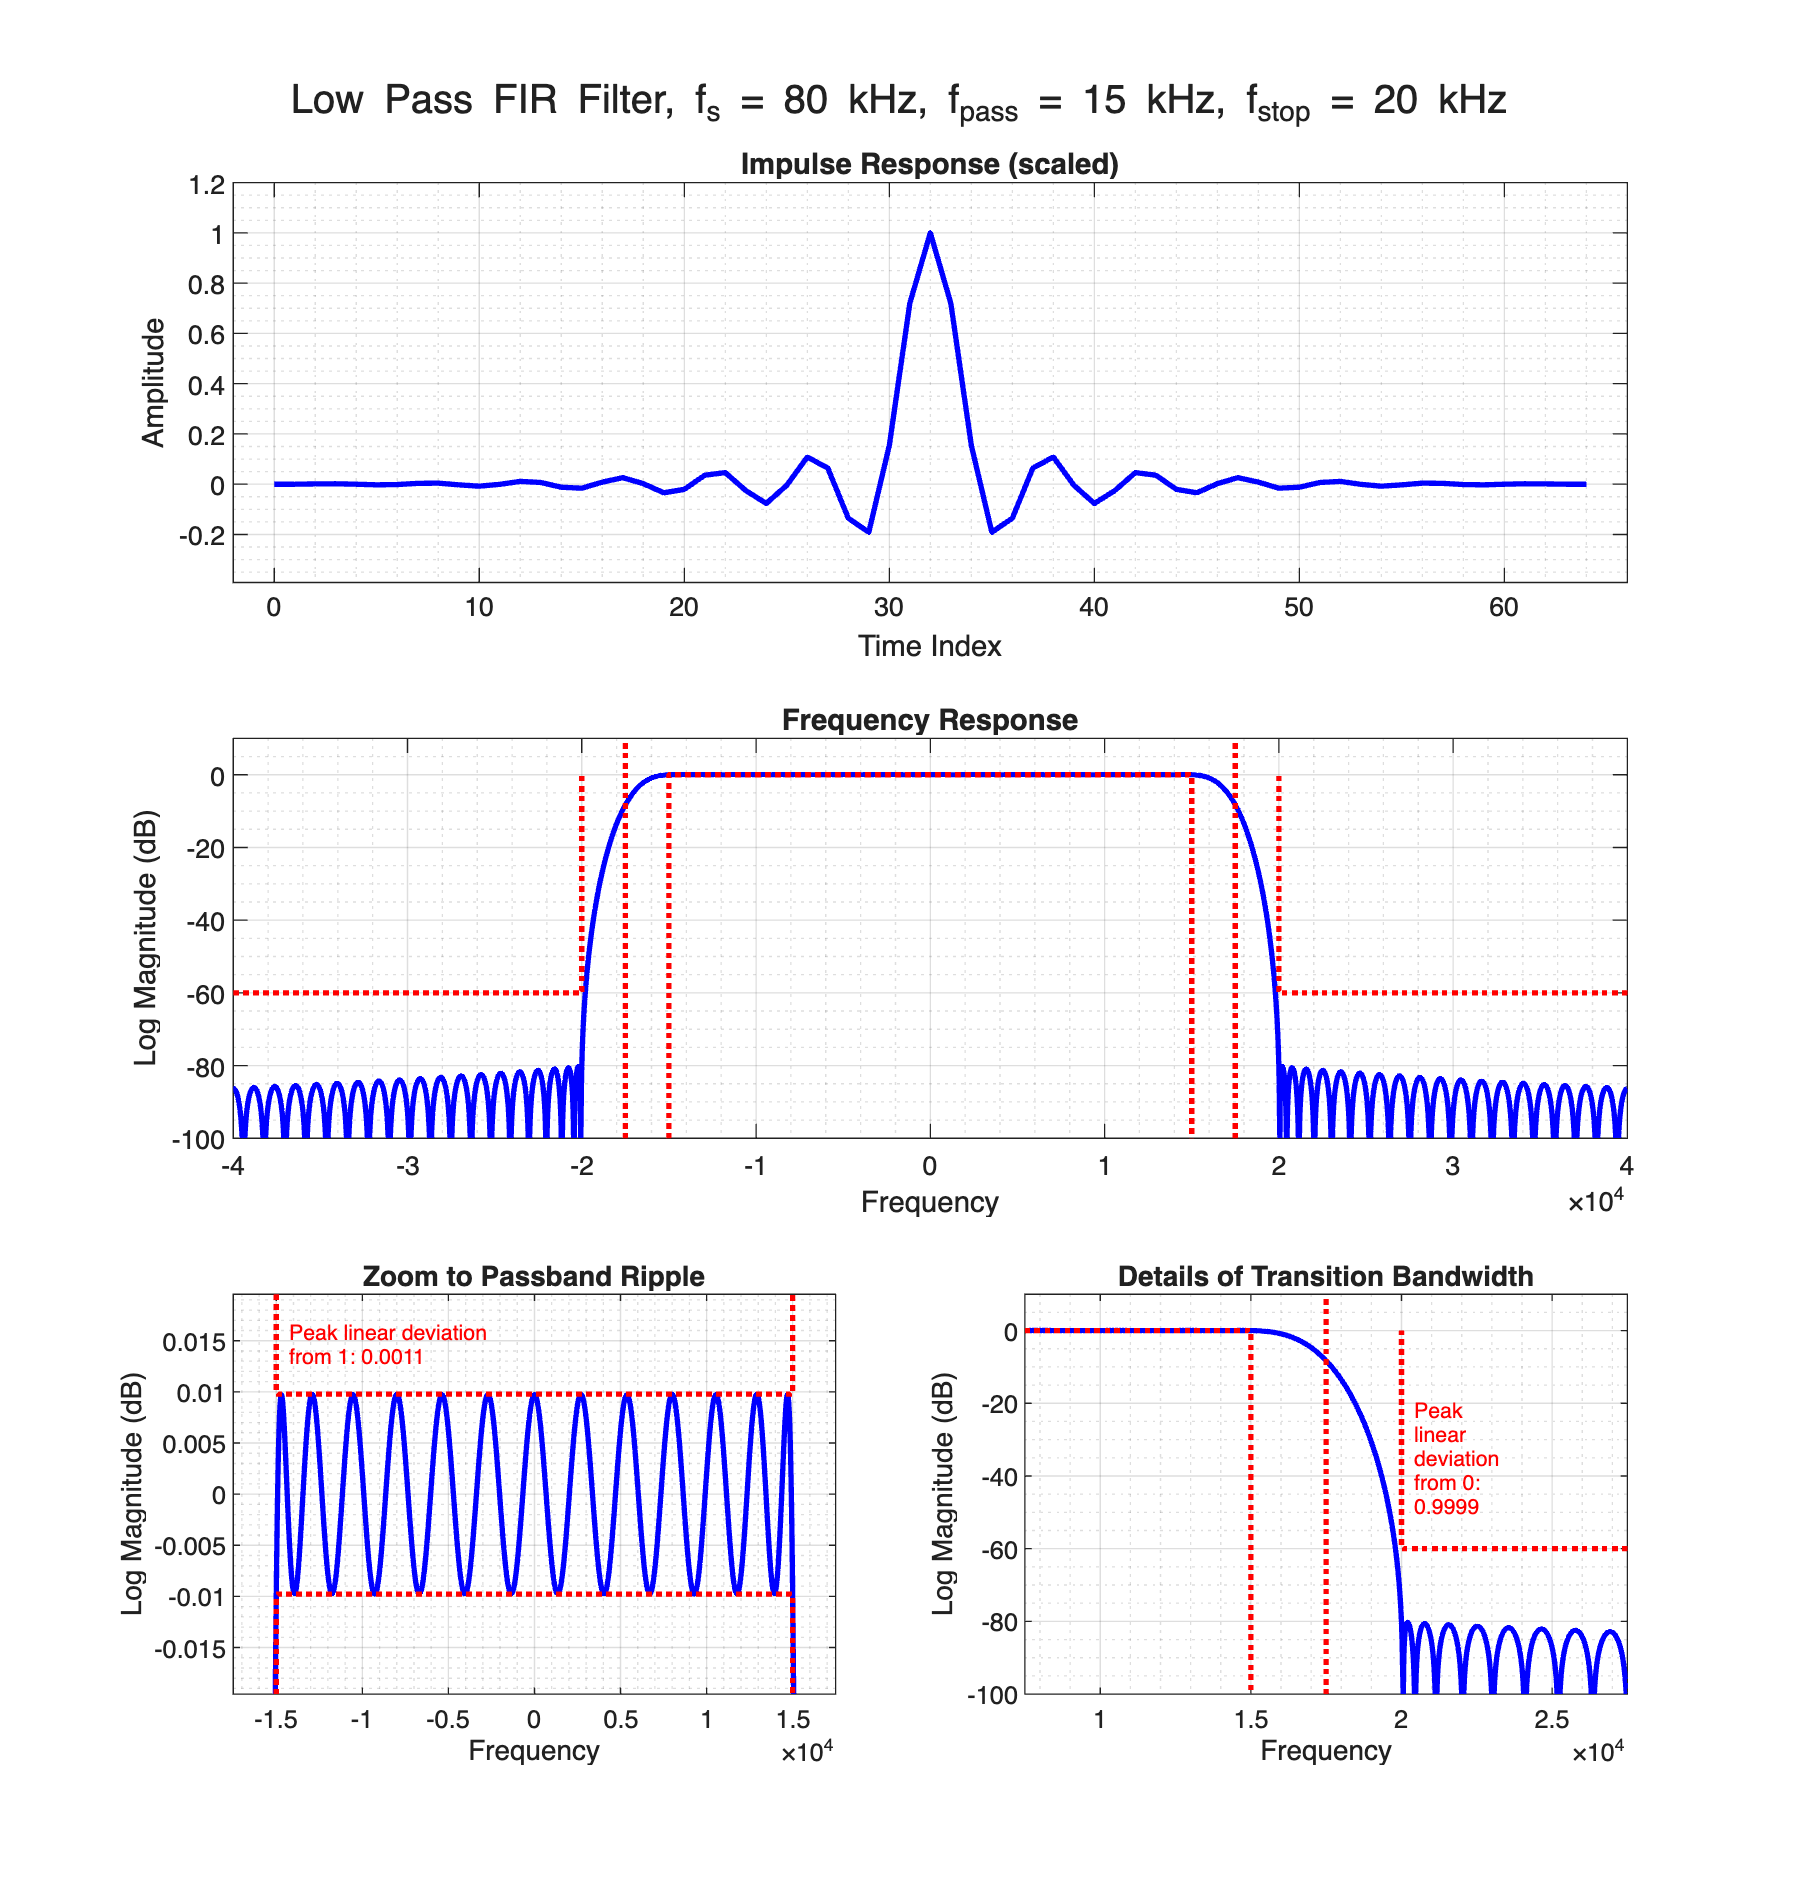

filter_design_and_plot(80, 15, 20, 0.1, 60);

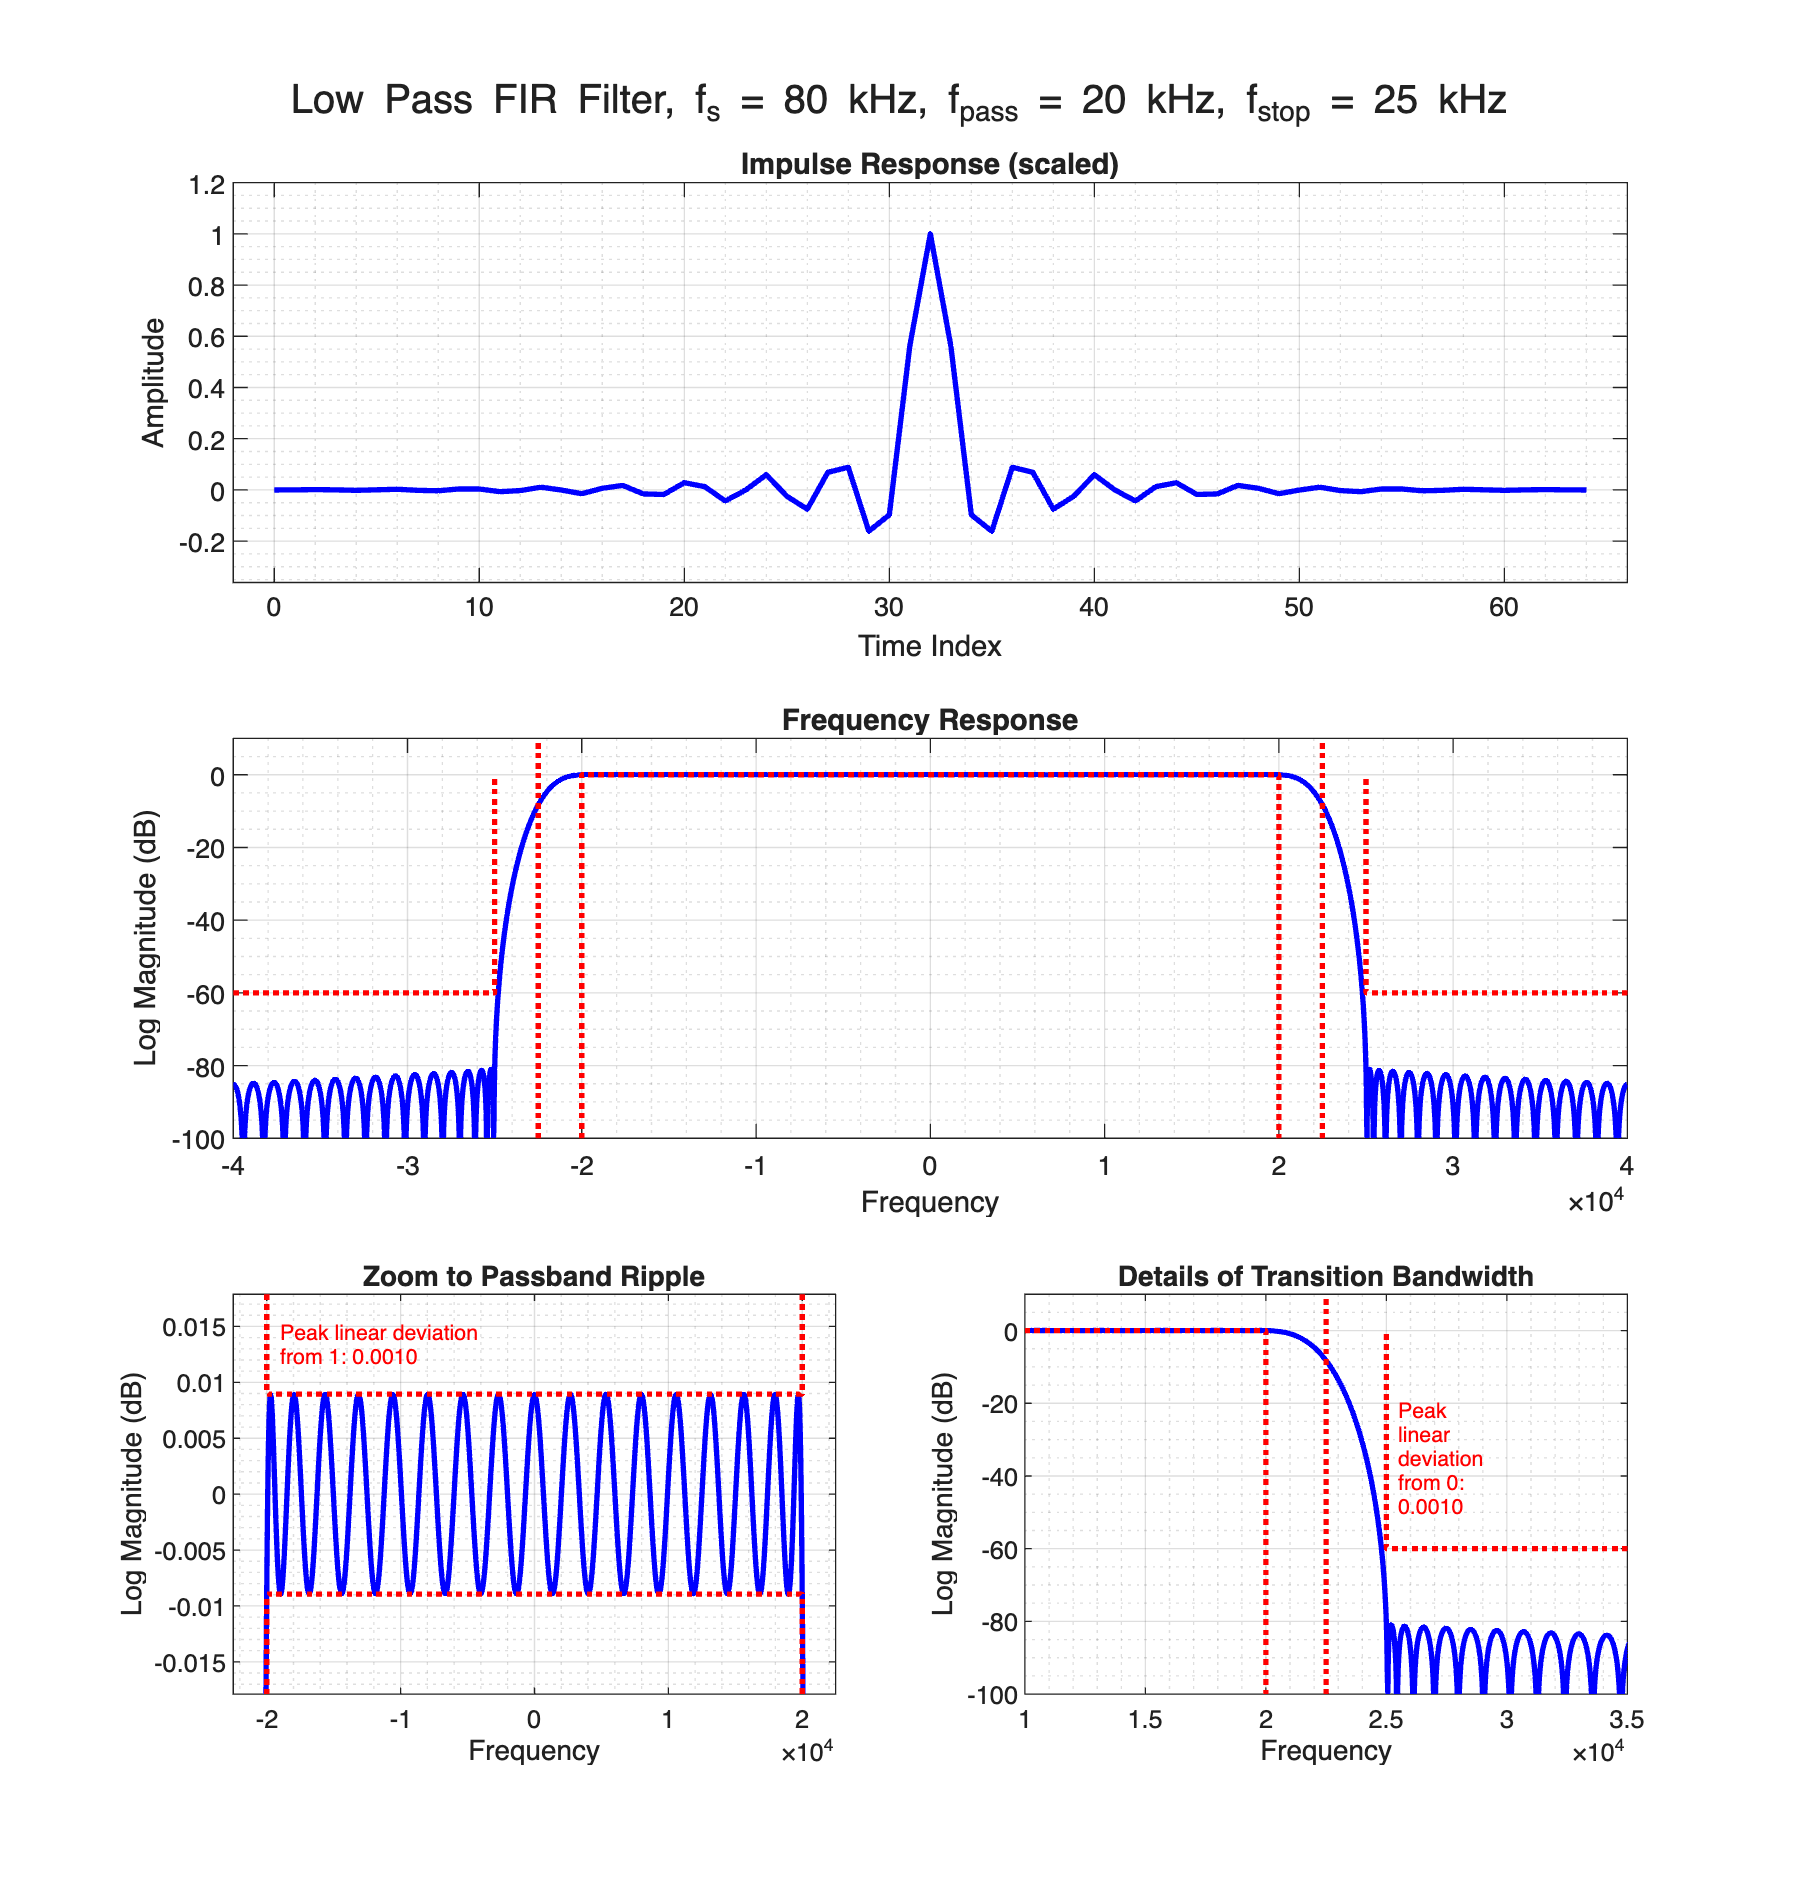

filter_design_and_plot(80, 20, 25, 0.1, 60);


filter_design_and_plot(80, 5, 10, 0.1, 60);

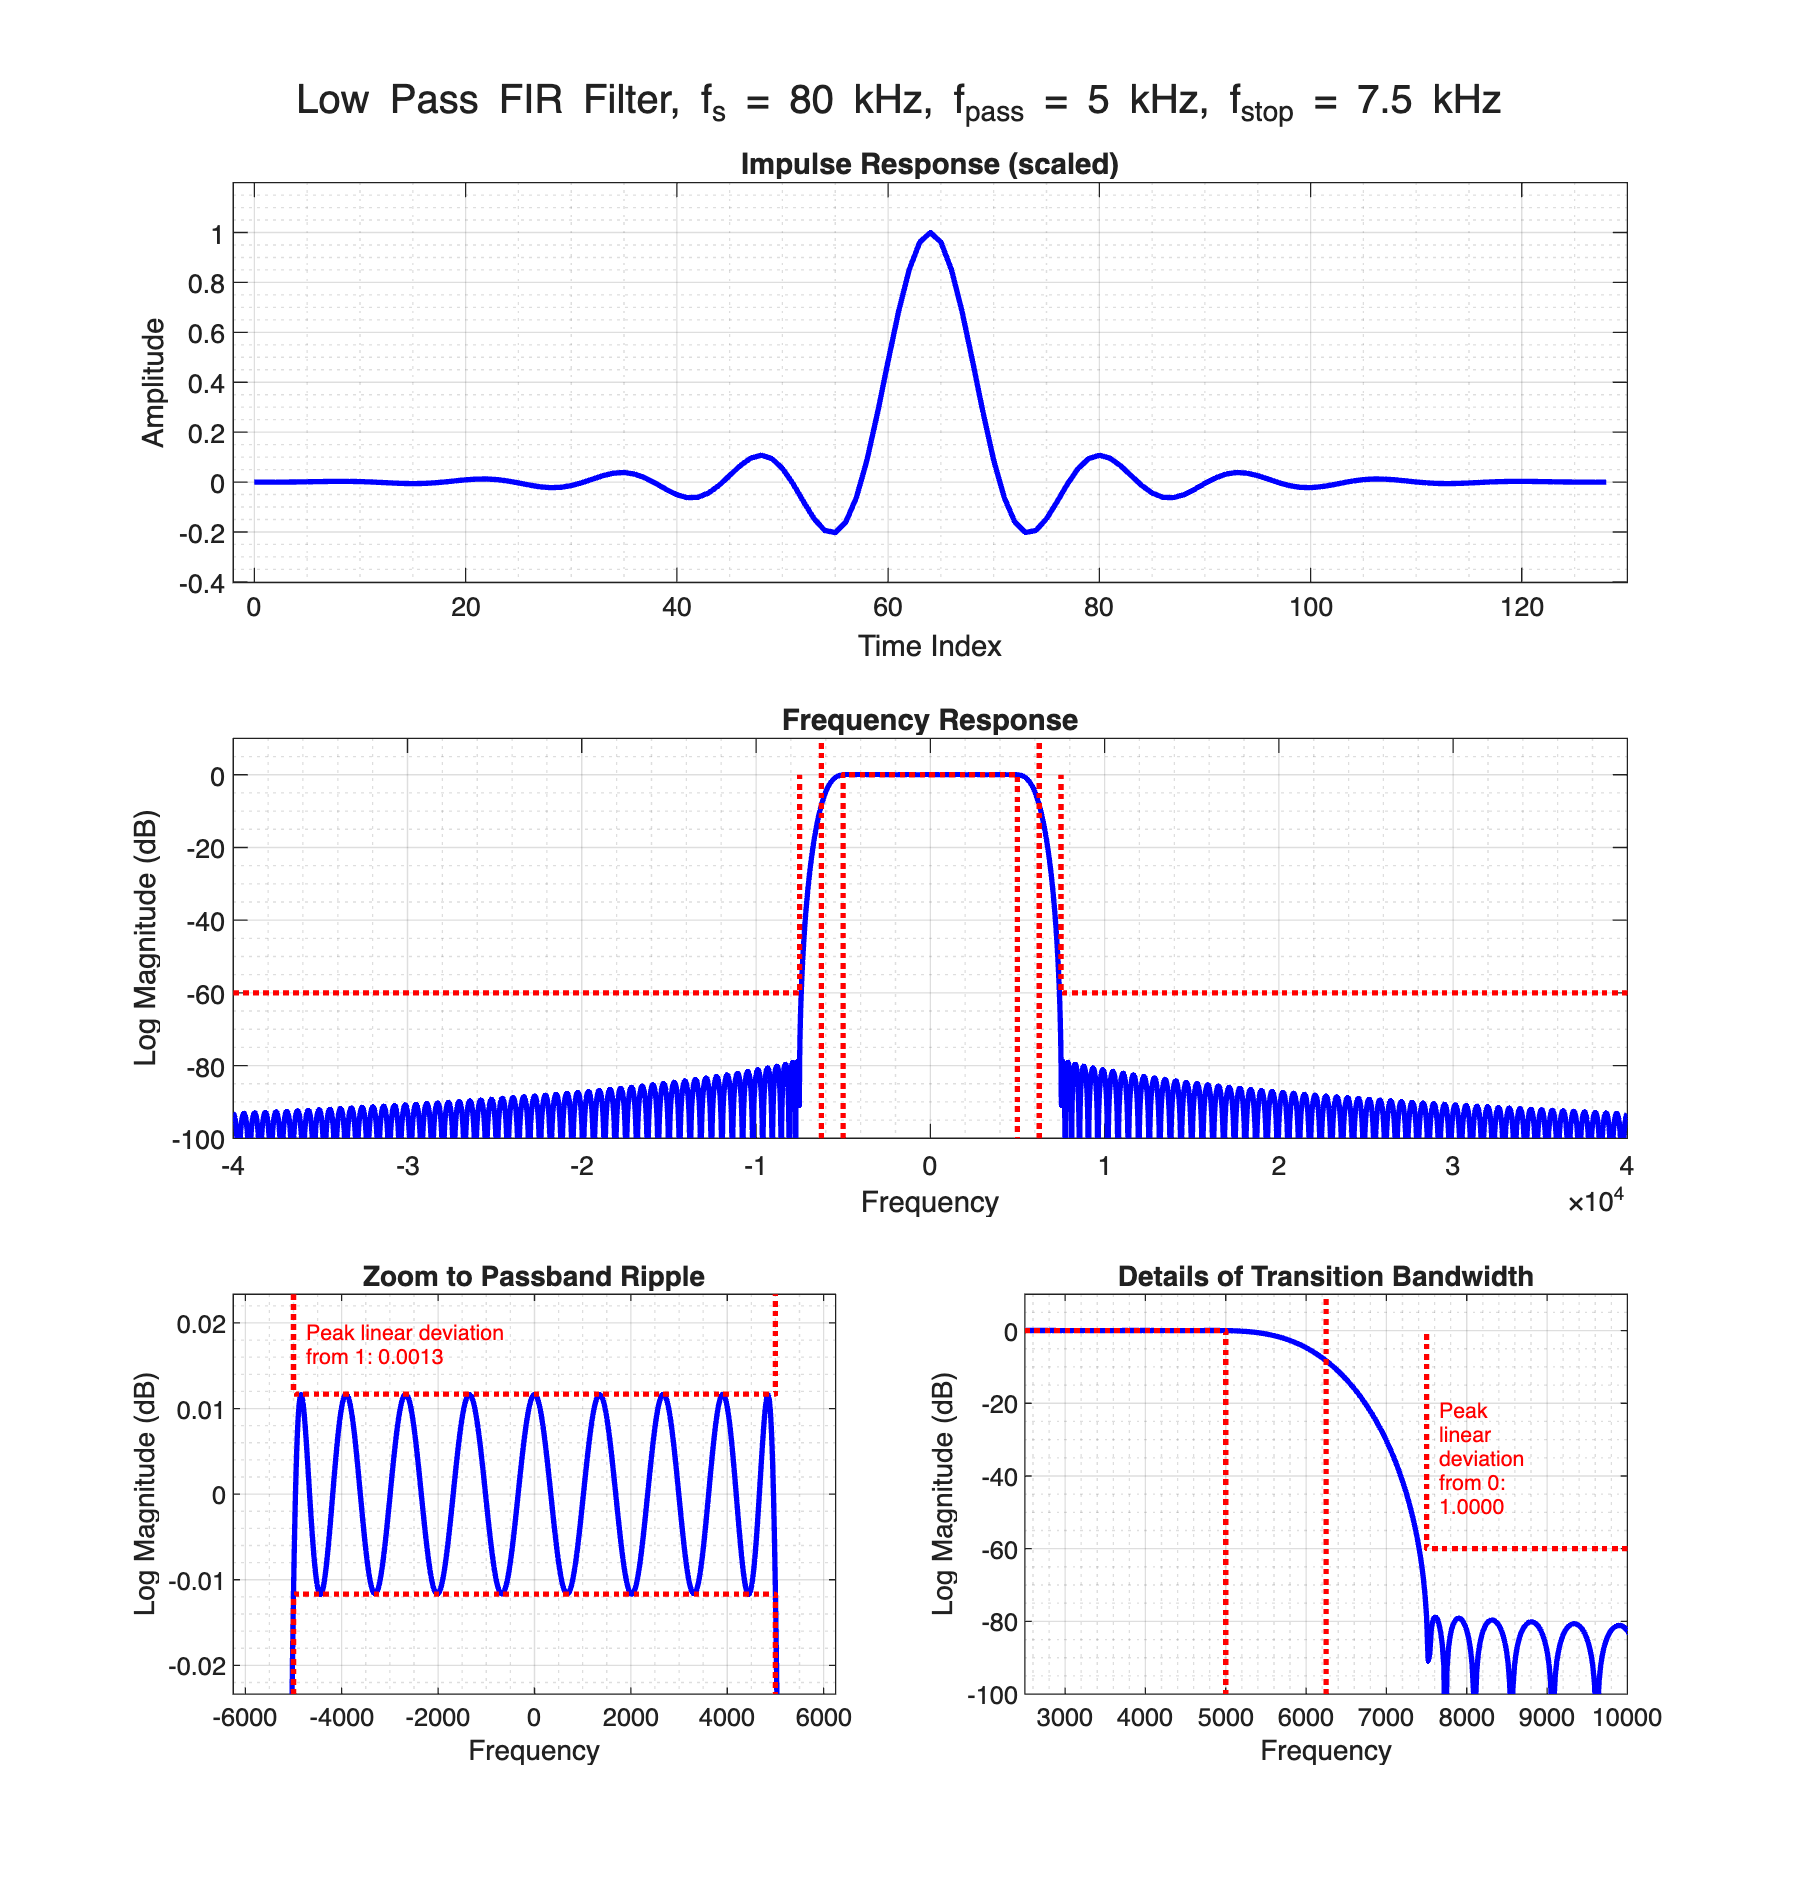

filter_design_and_plot(80, 5, 7.5, 0.1, 60);

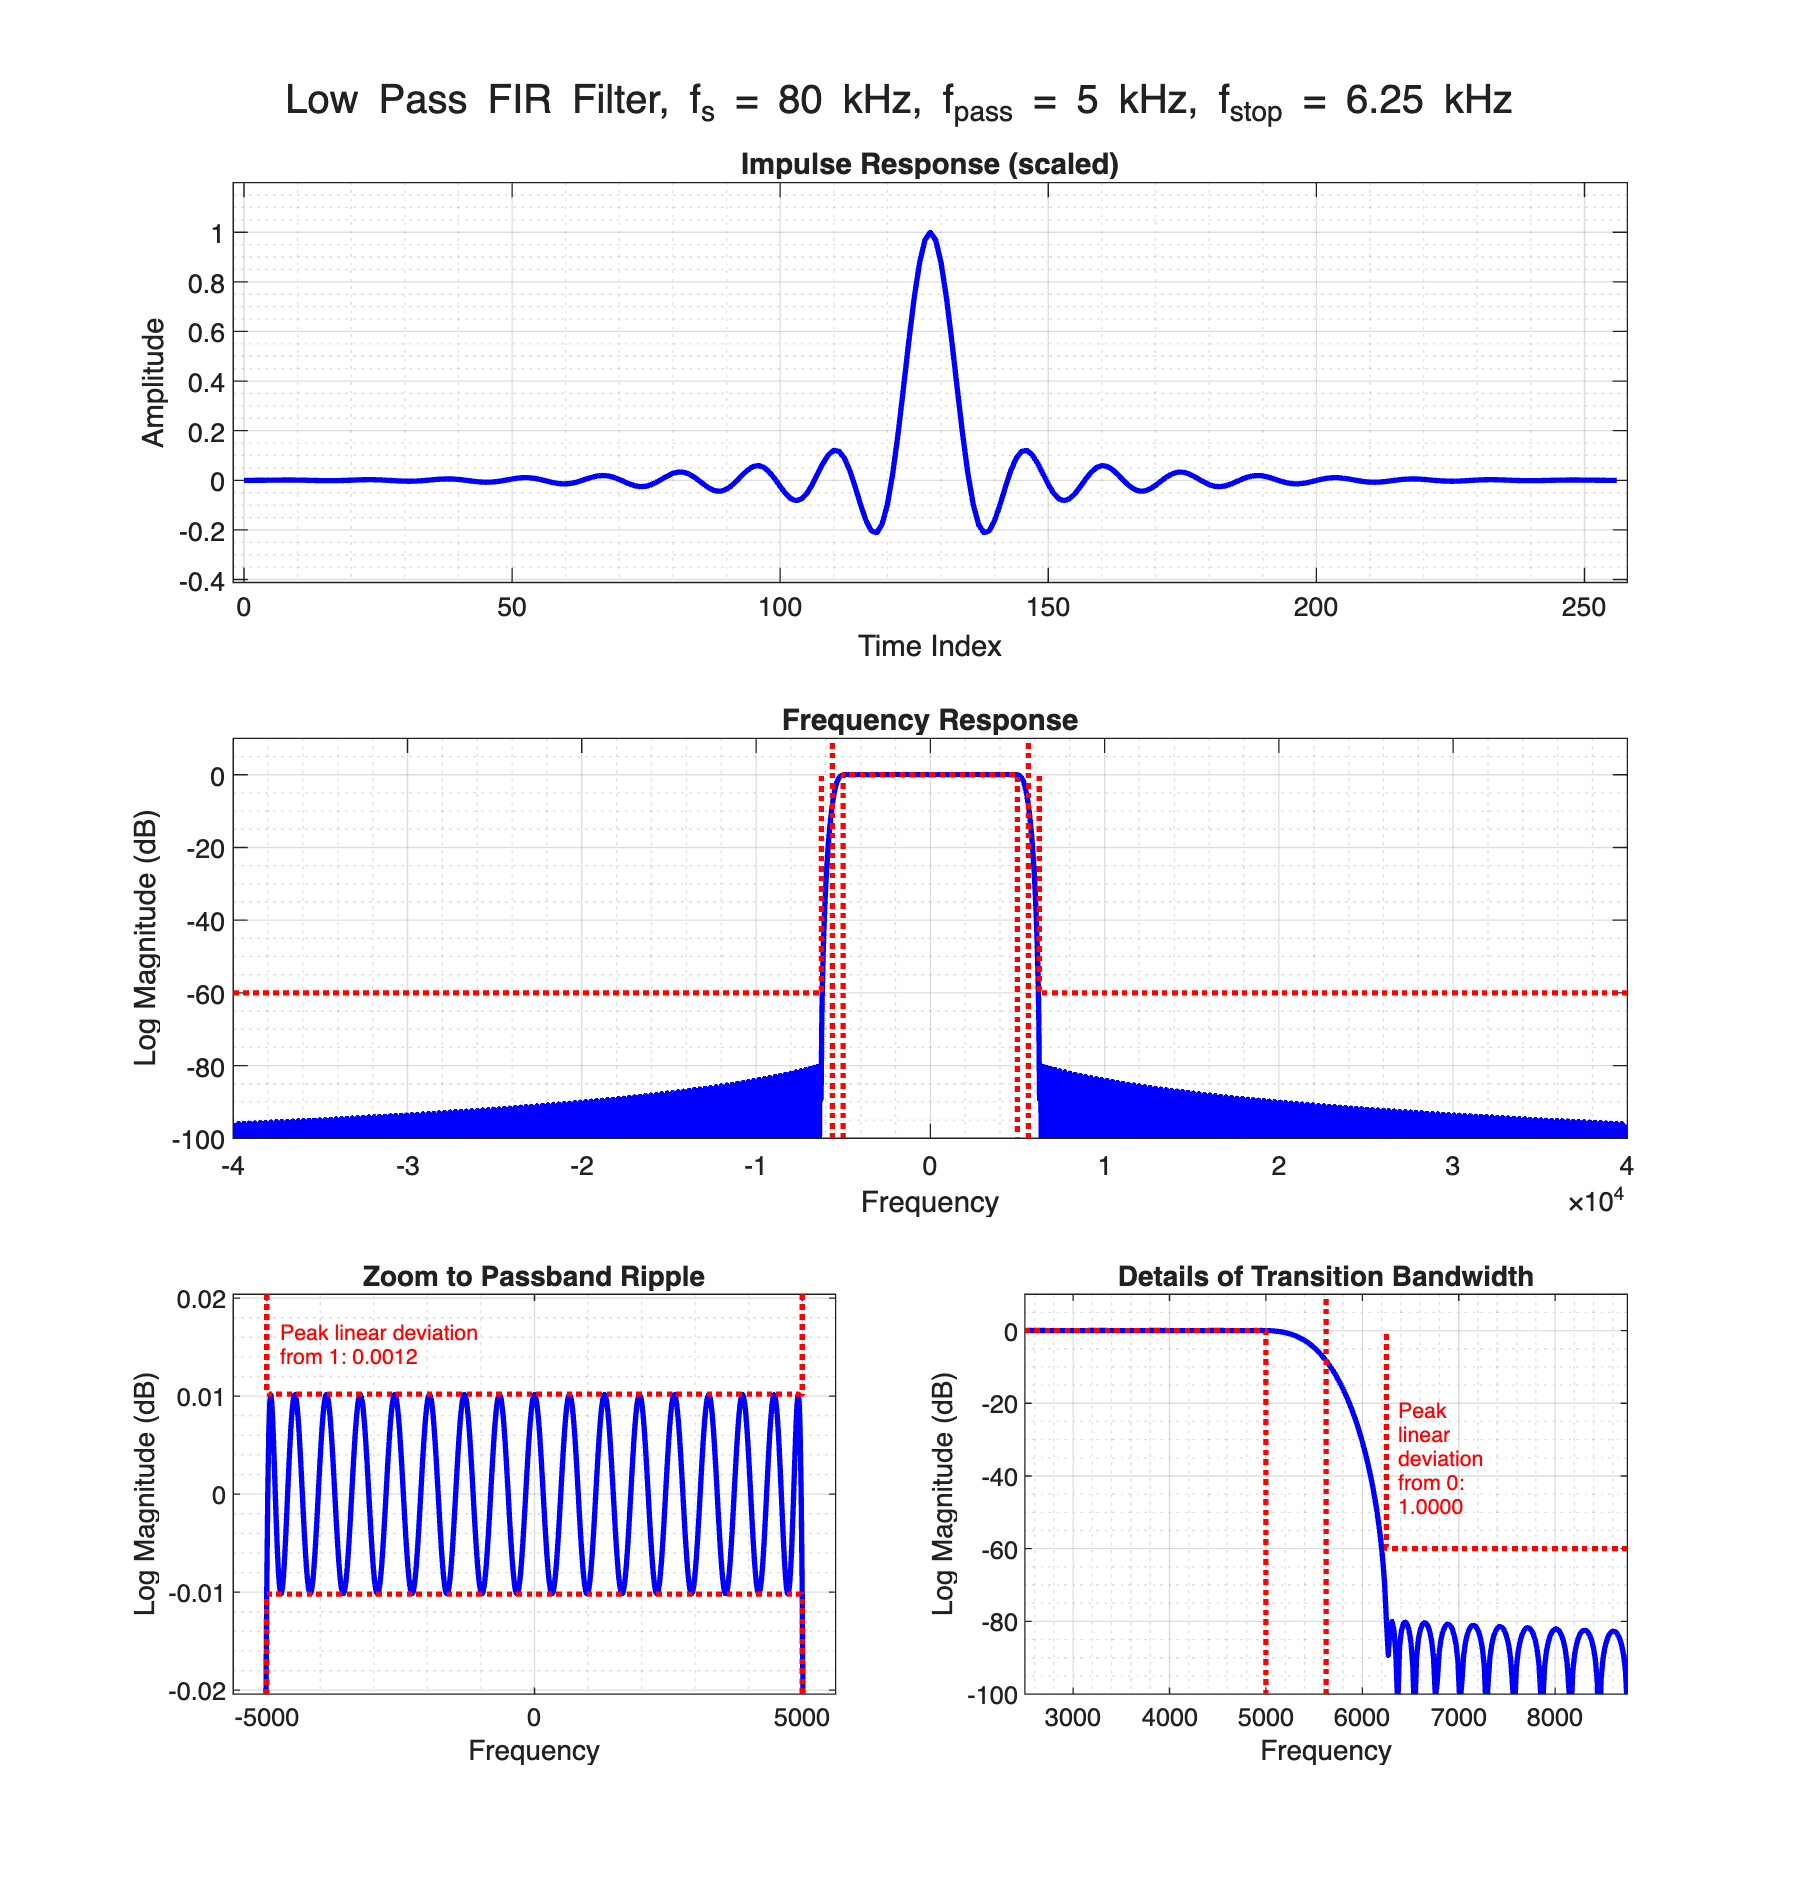

filter_design_and_plot(80, 5, 6.25, 0.1, 60);

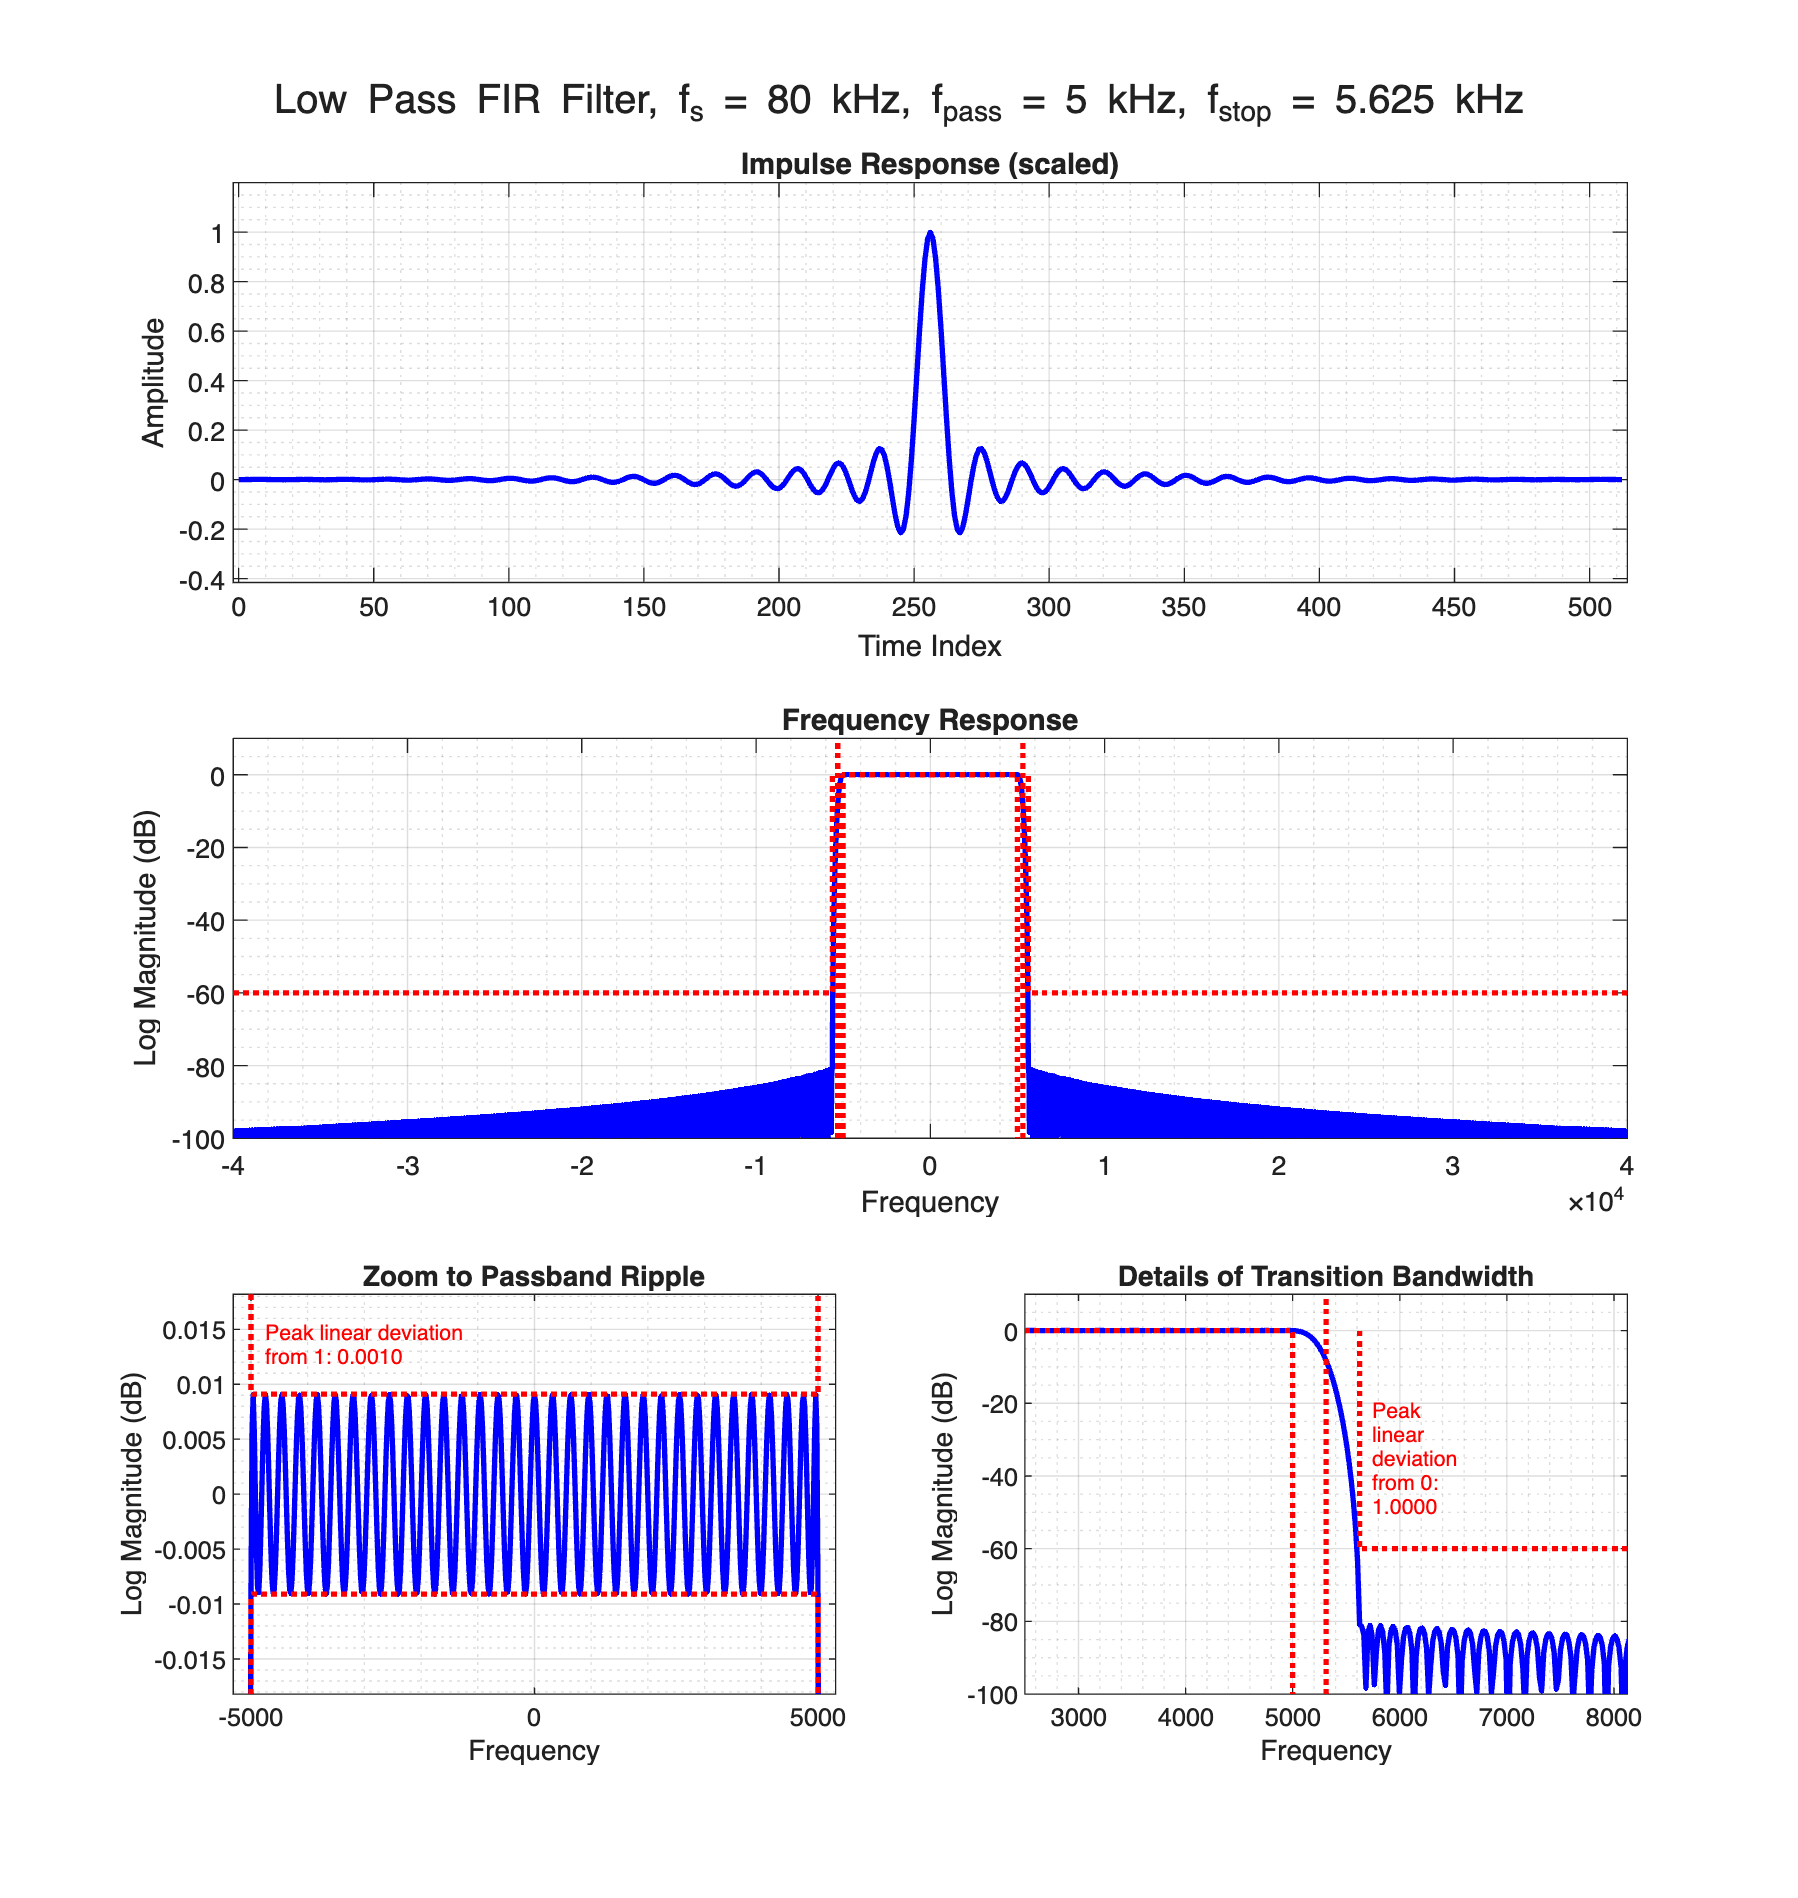

filter_design_and_plot(80, 5, 5.625, 0.1, 60);